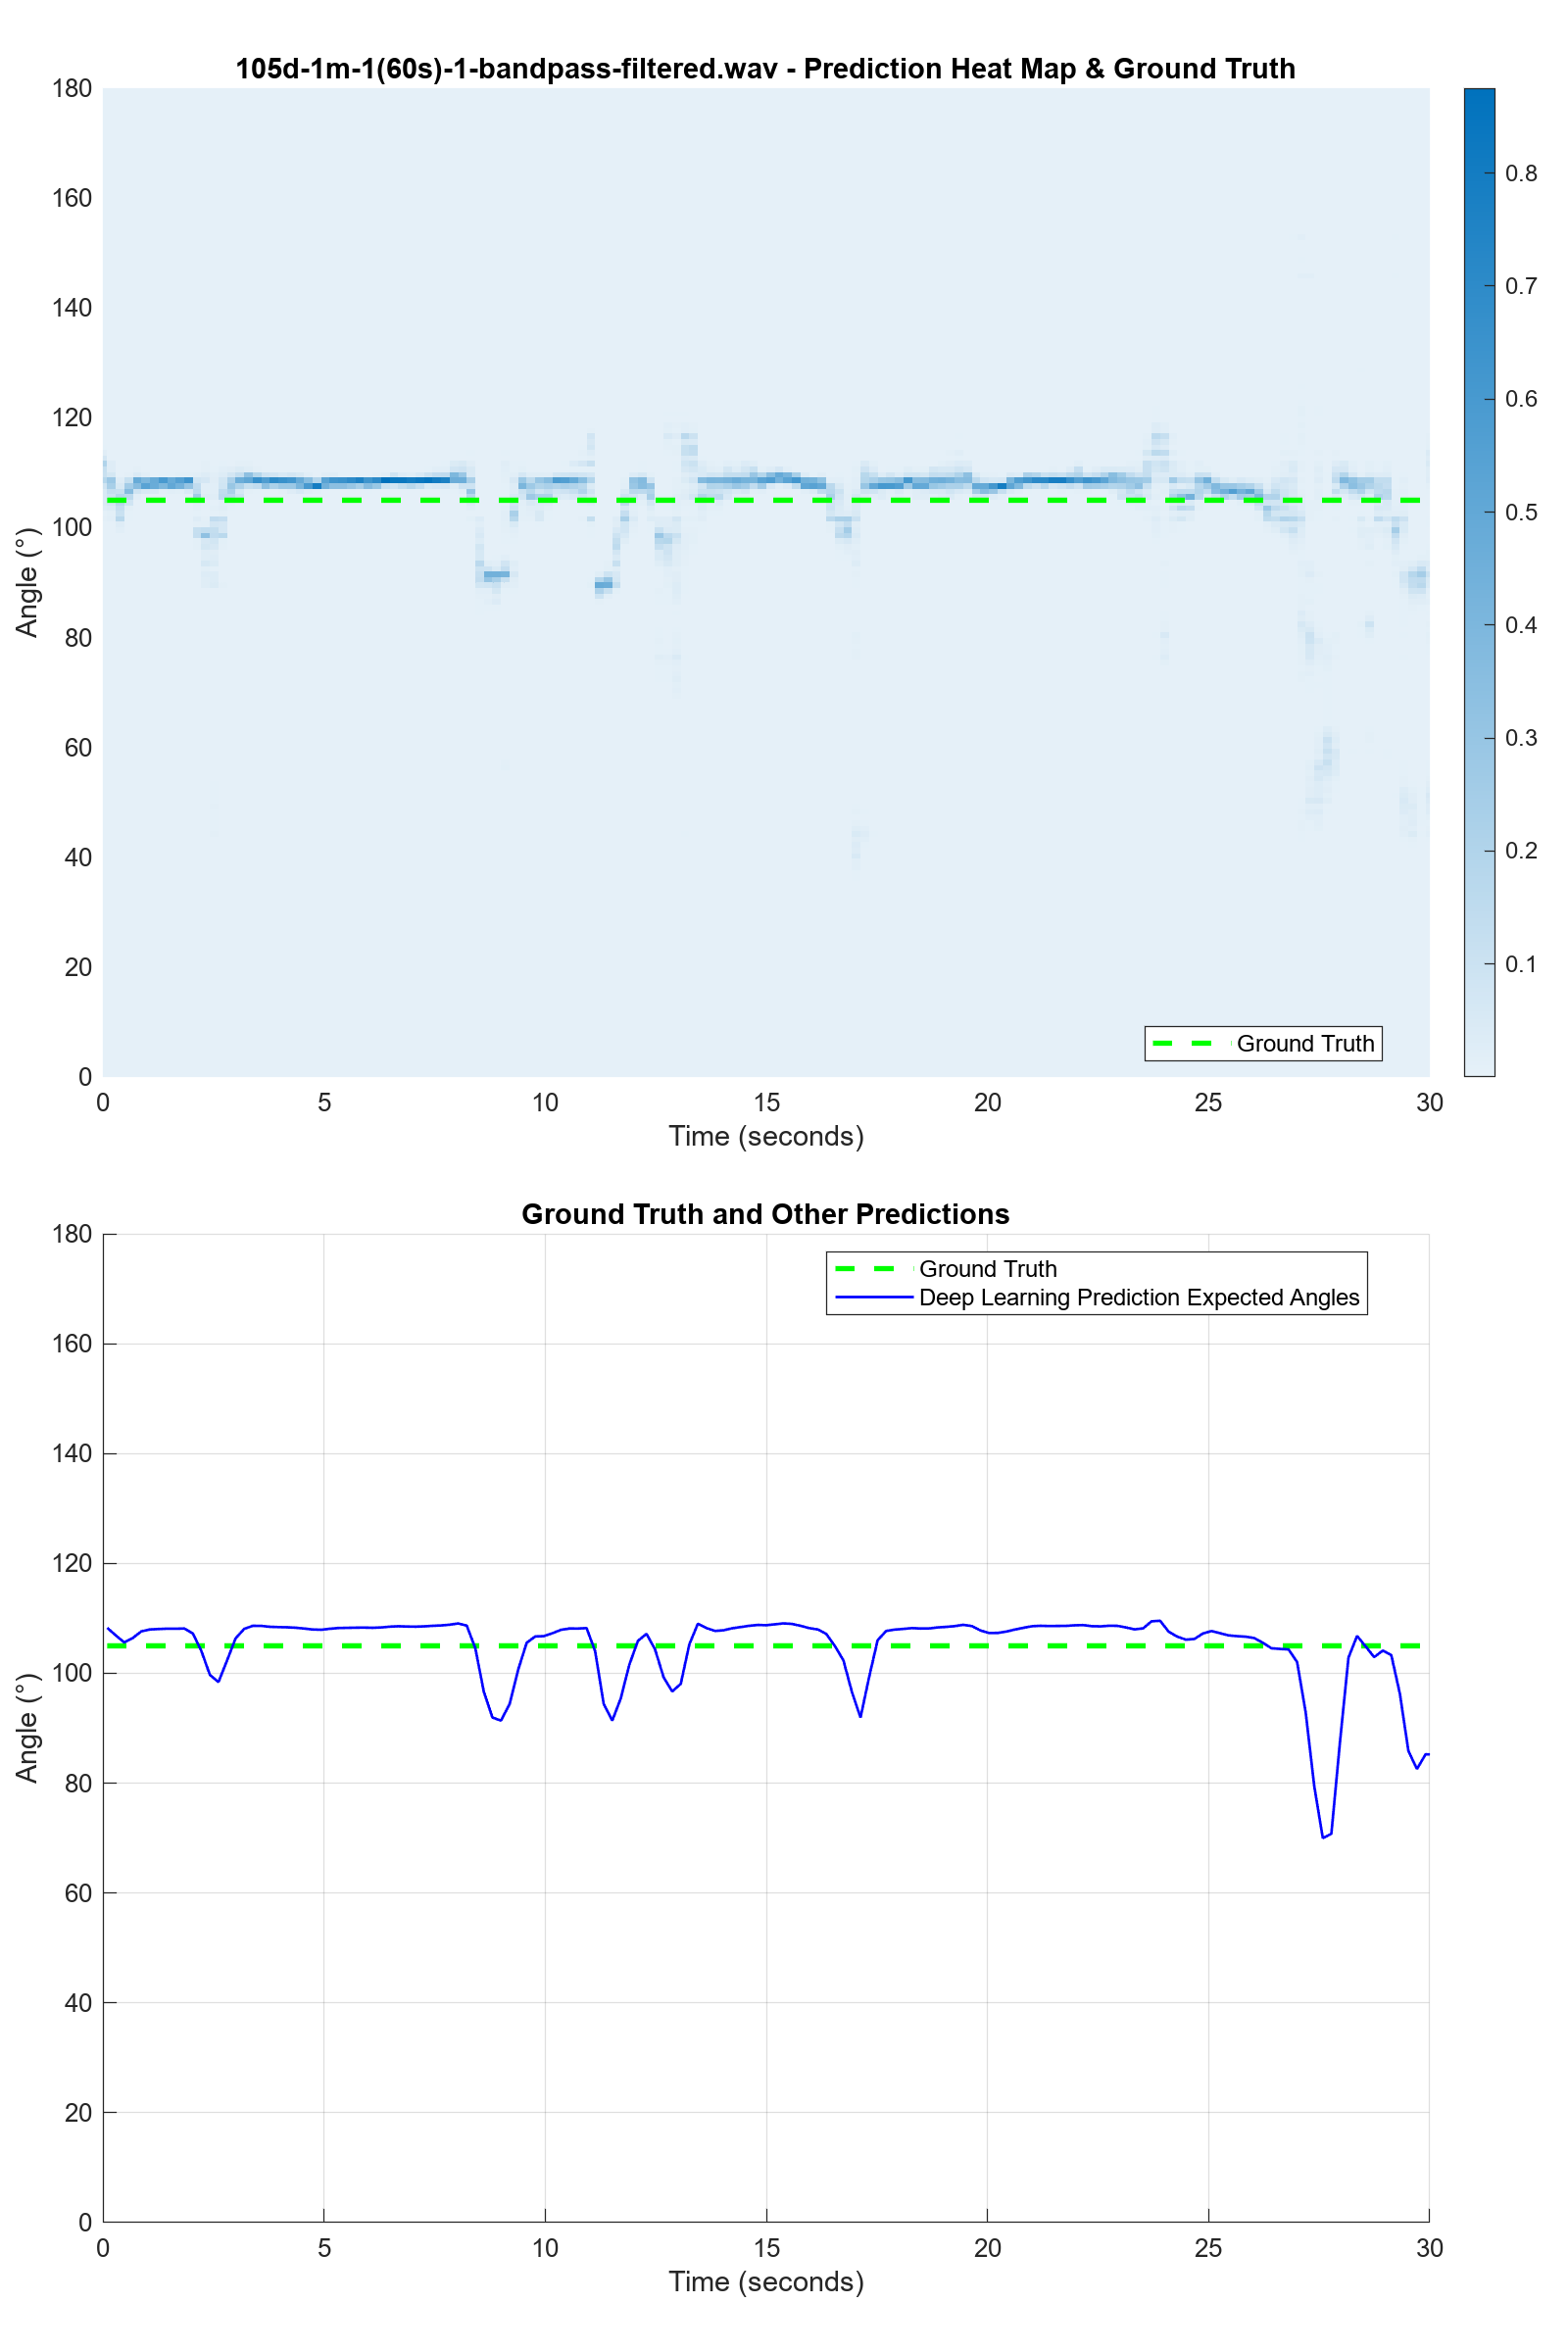

成功保存图像: 105d-1m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


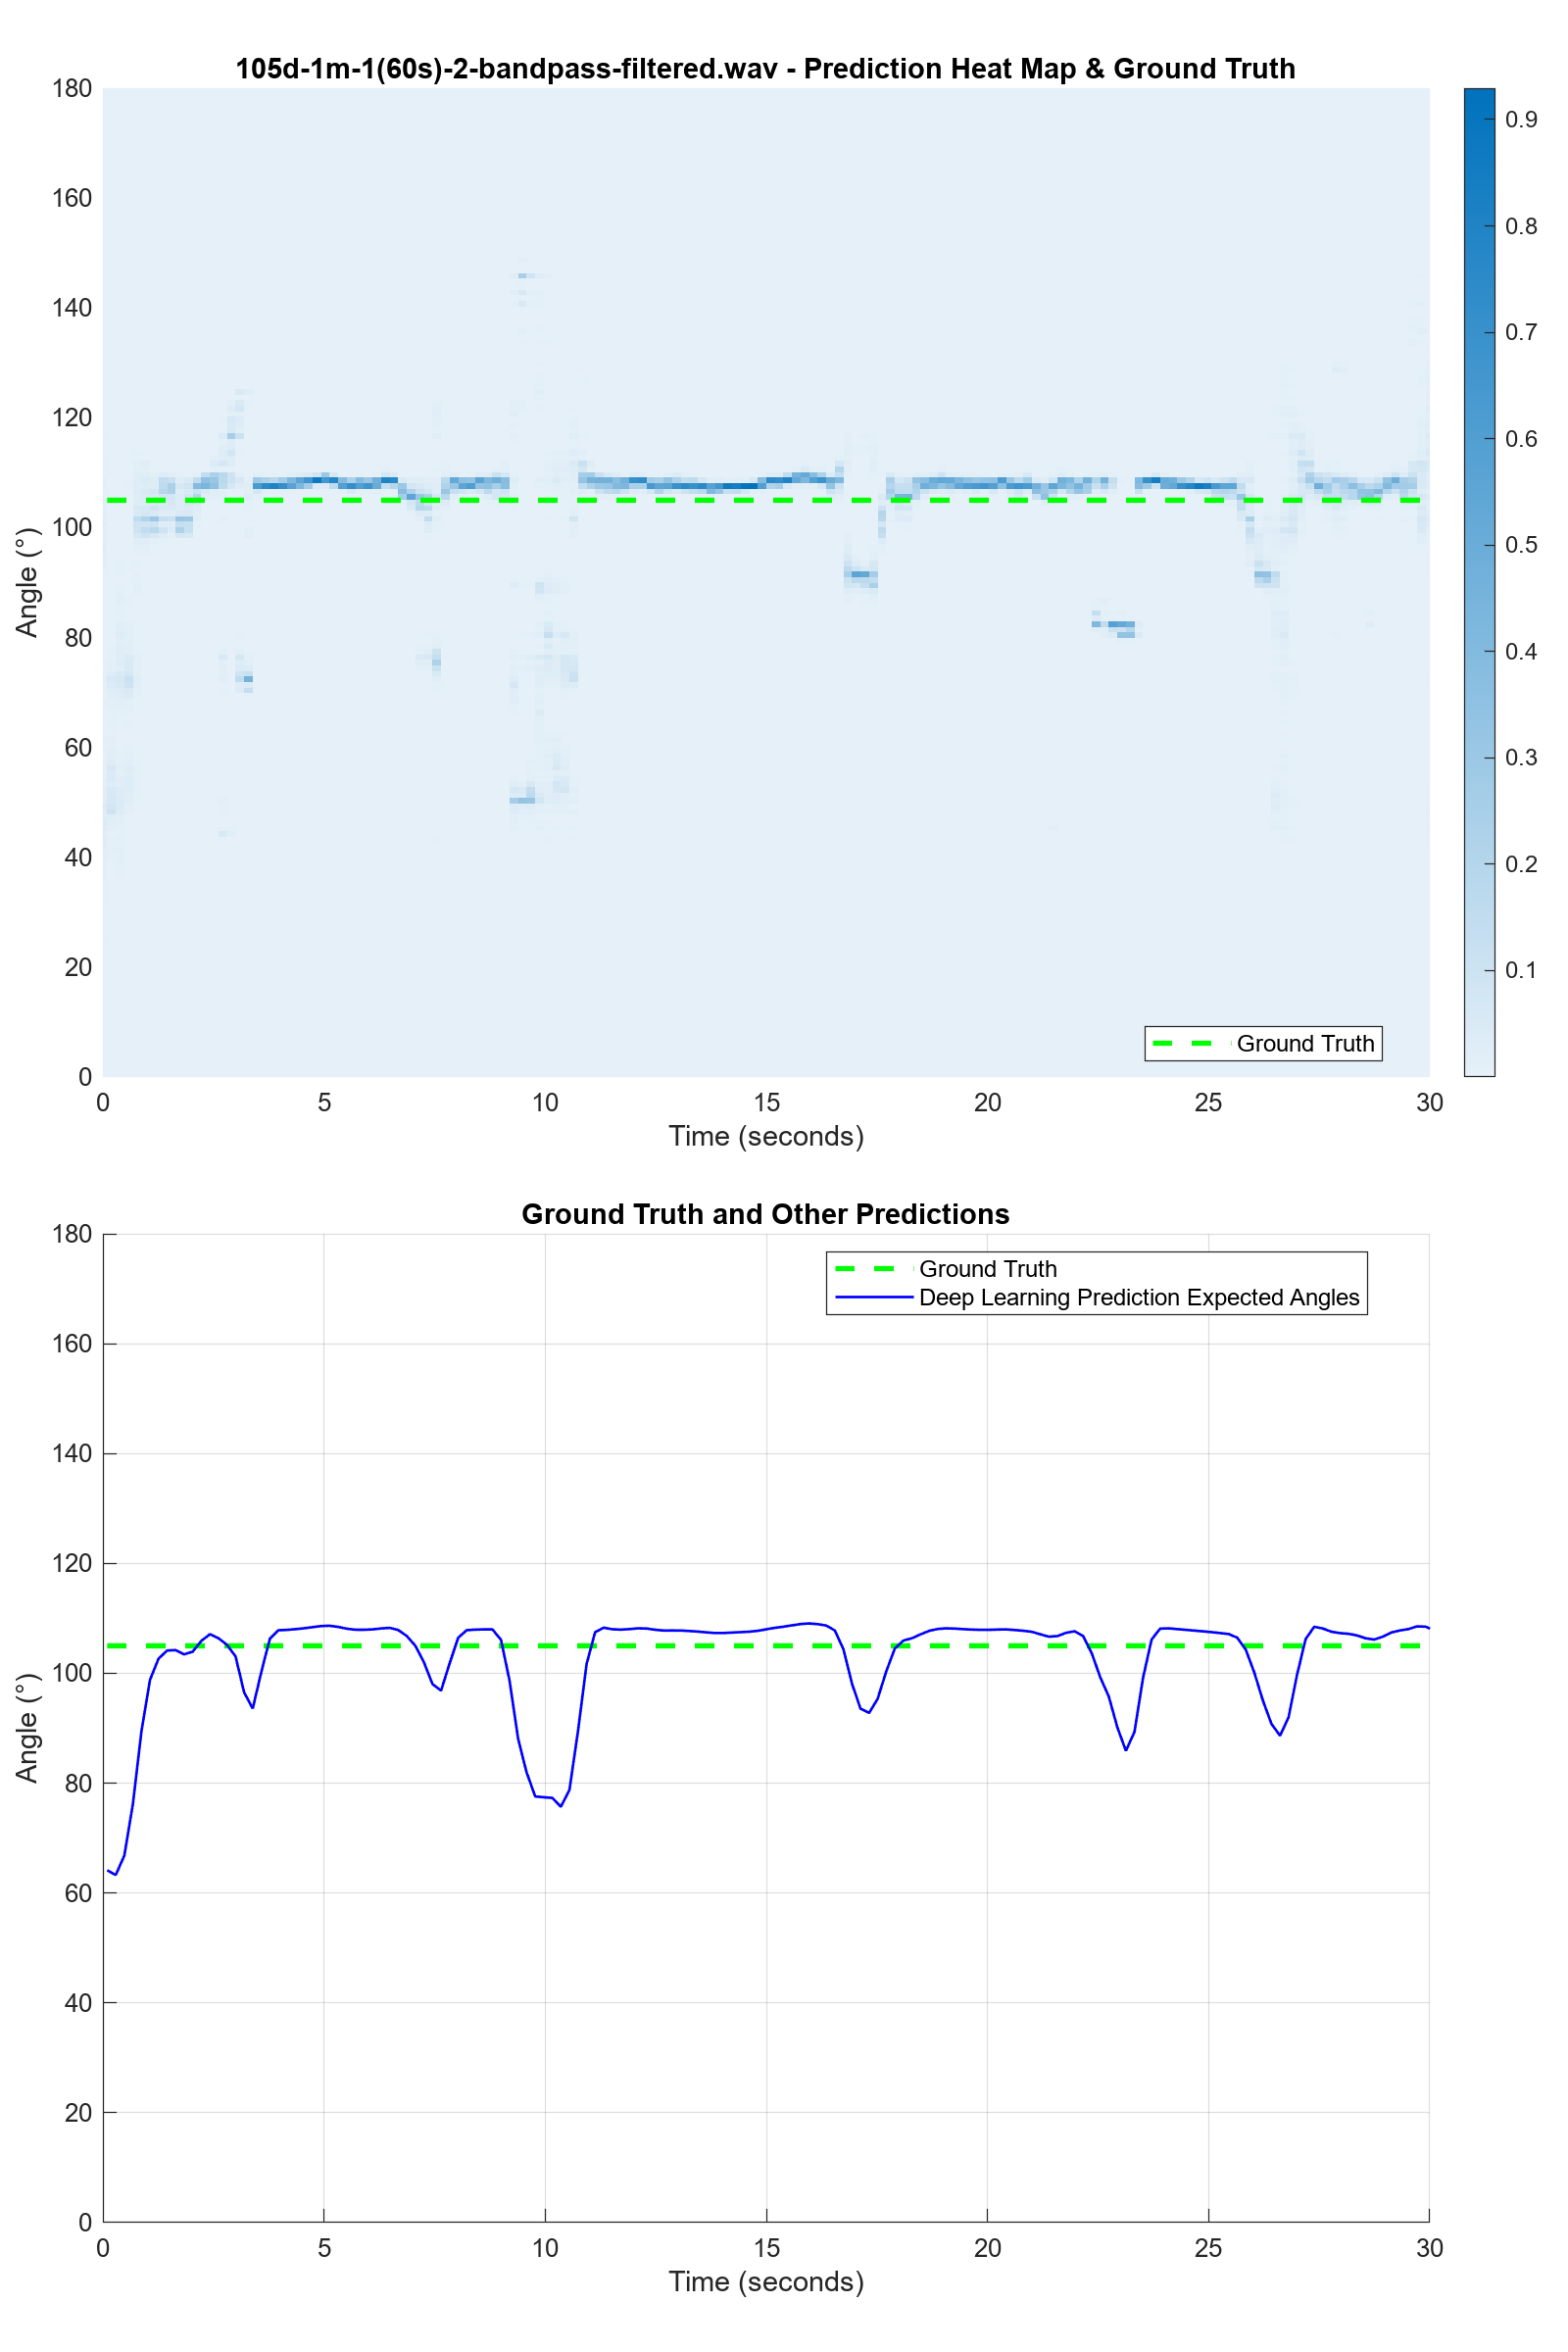

成功保存图像: 105d-1m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


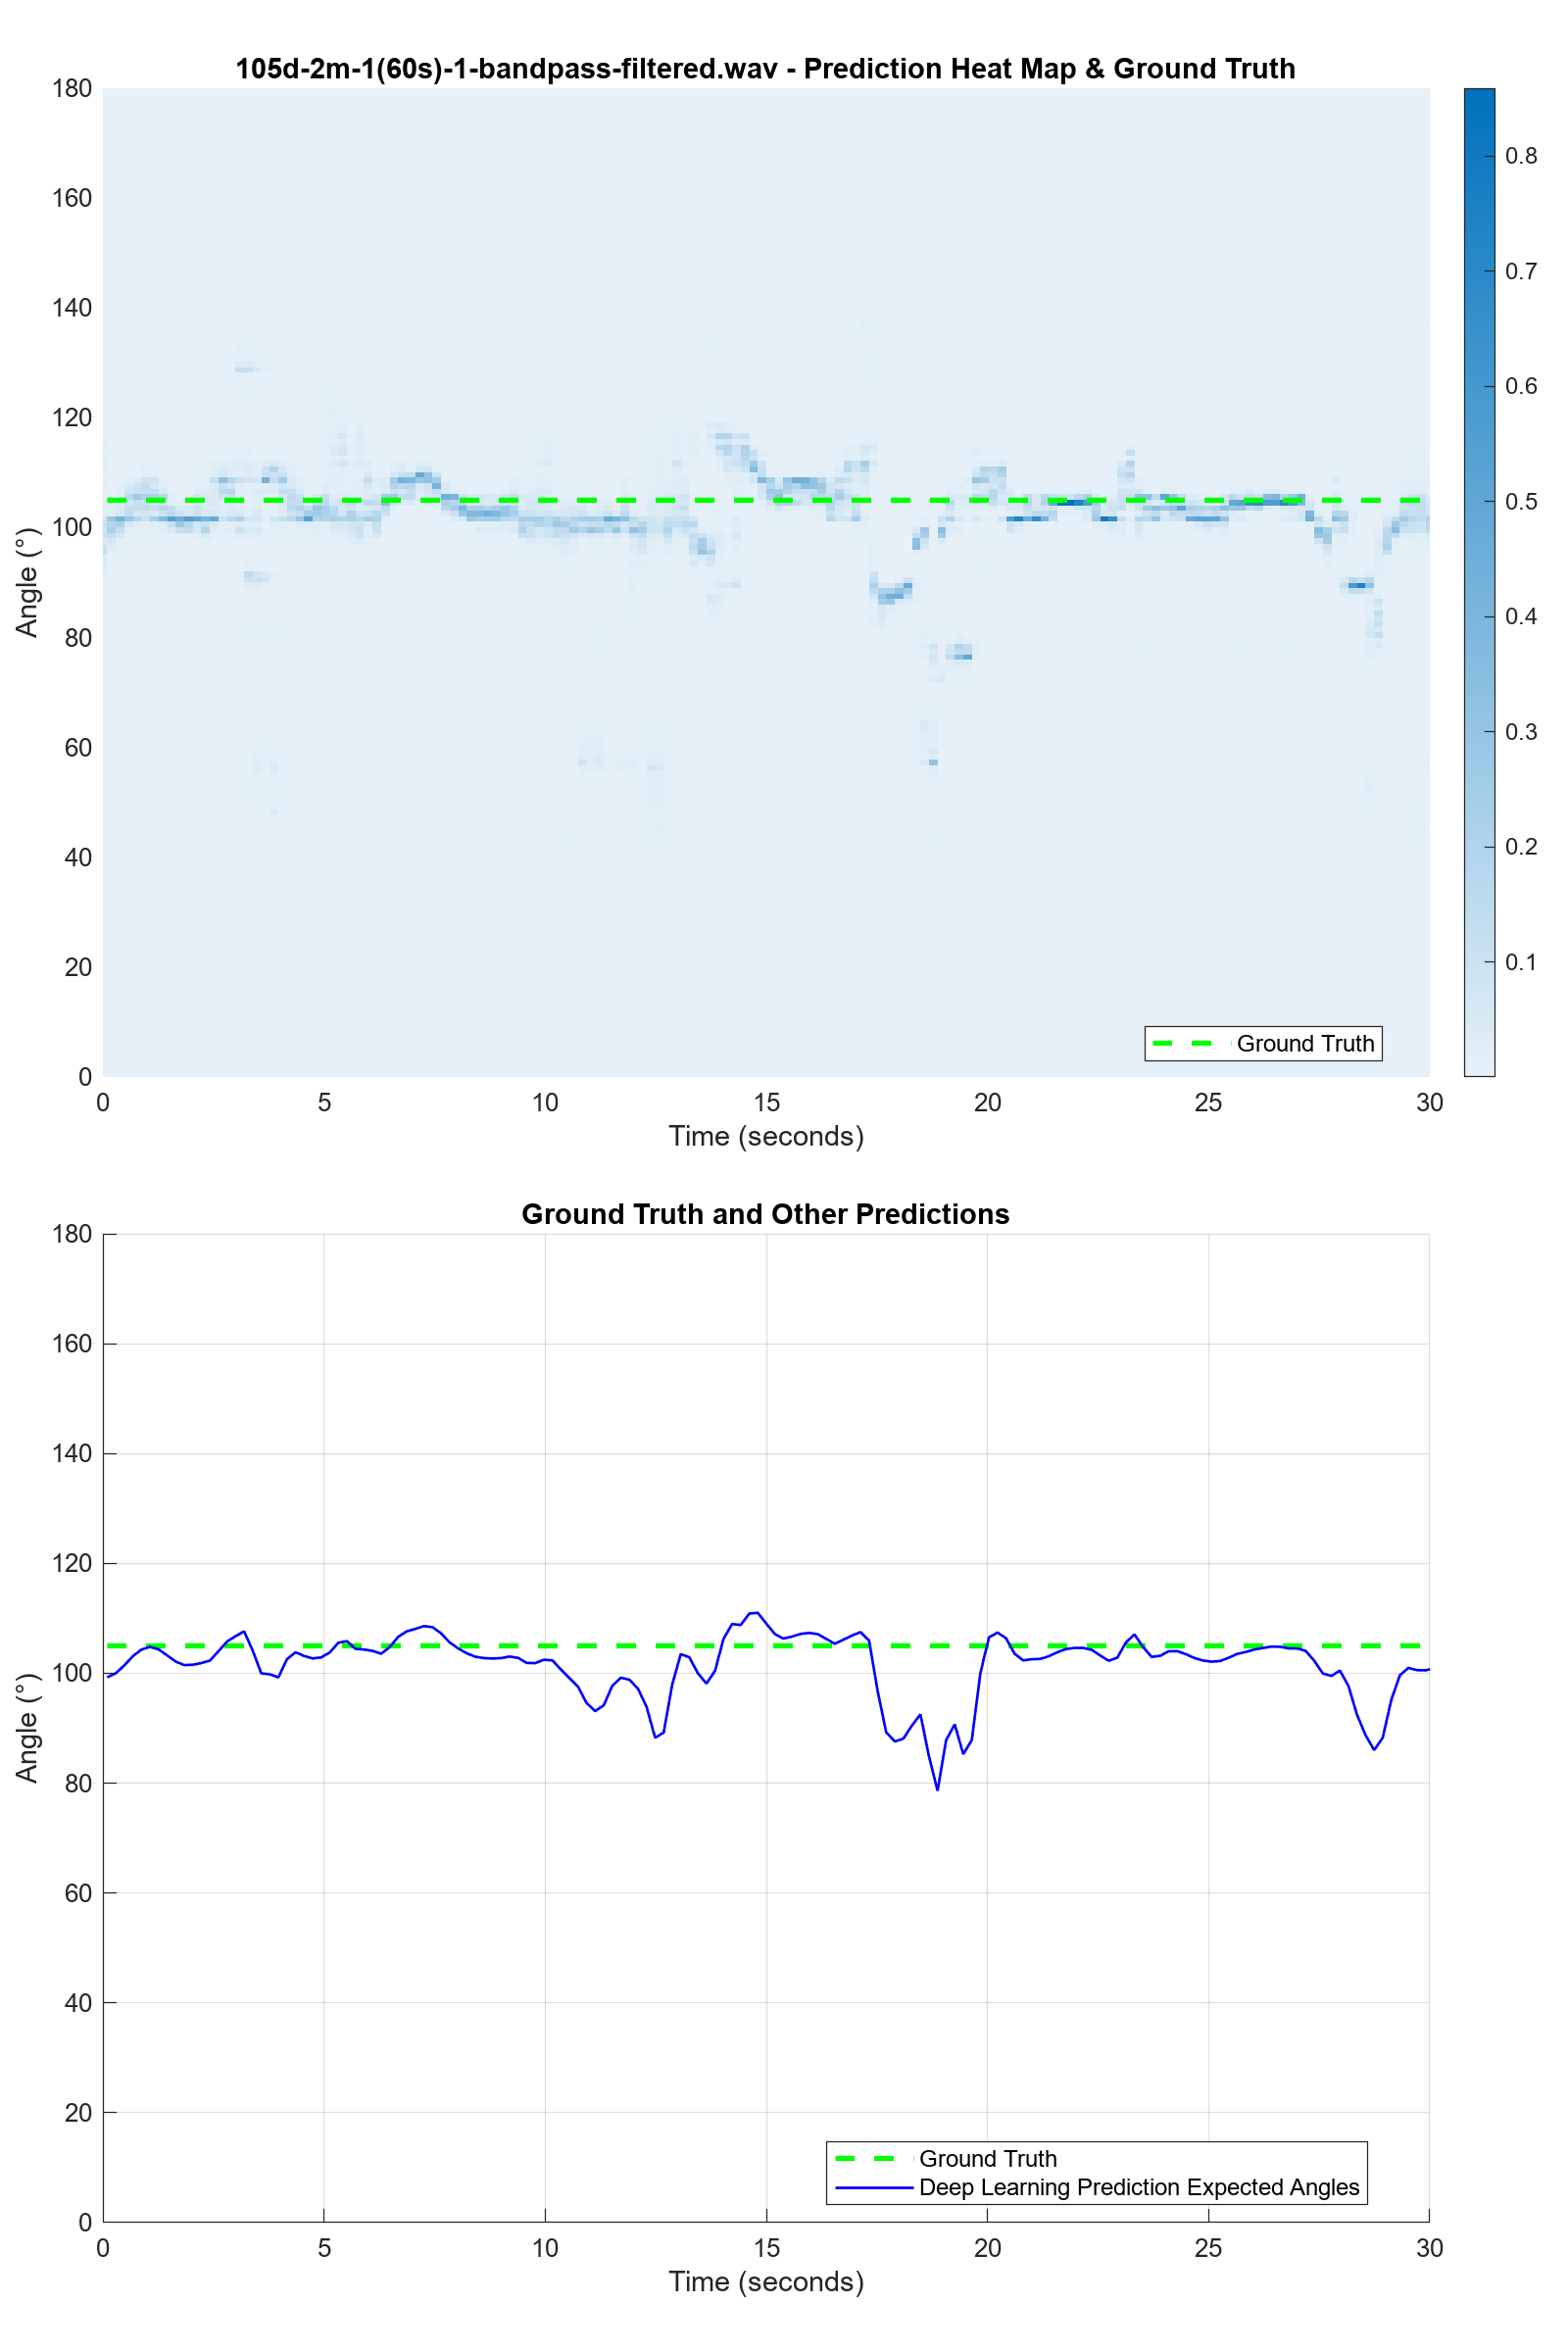

成功保存图像: 105d-2m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


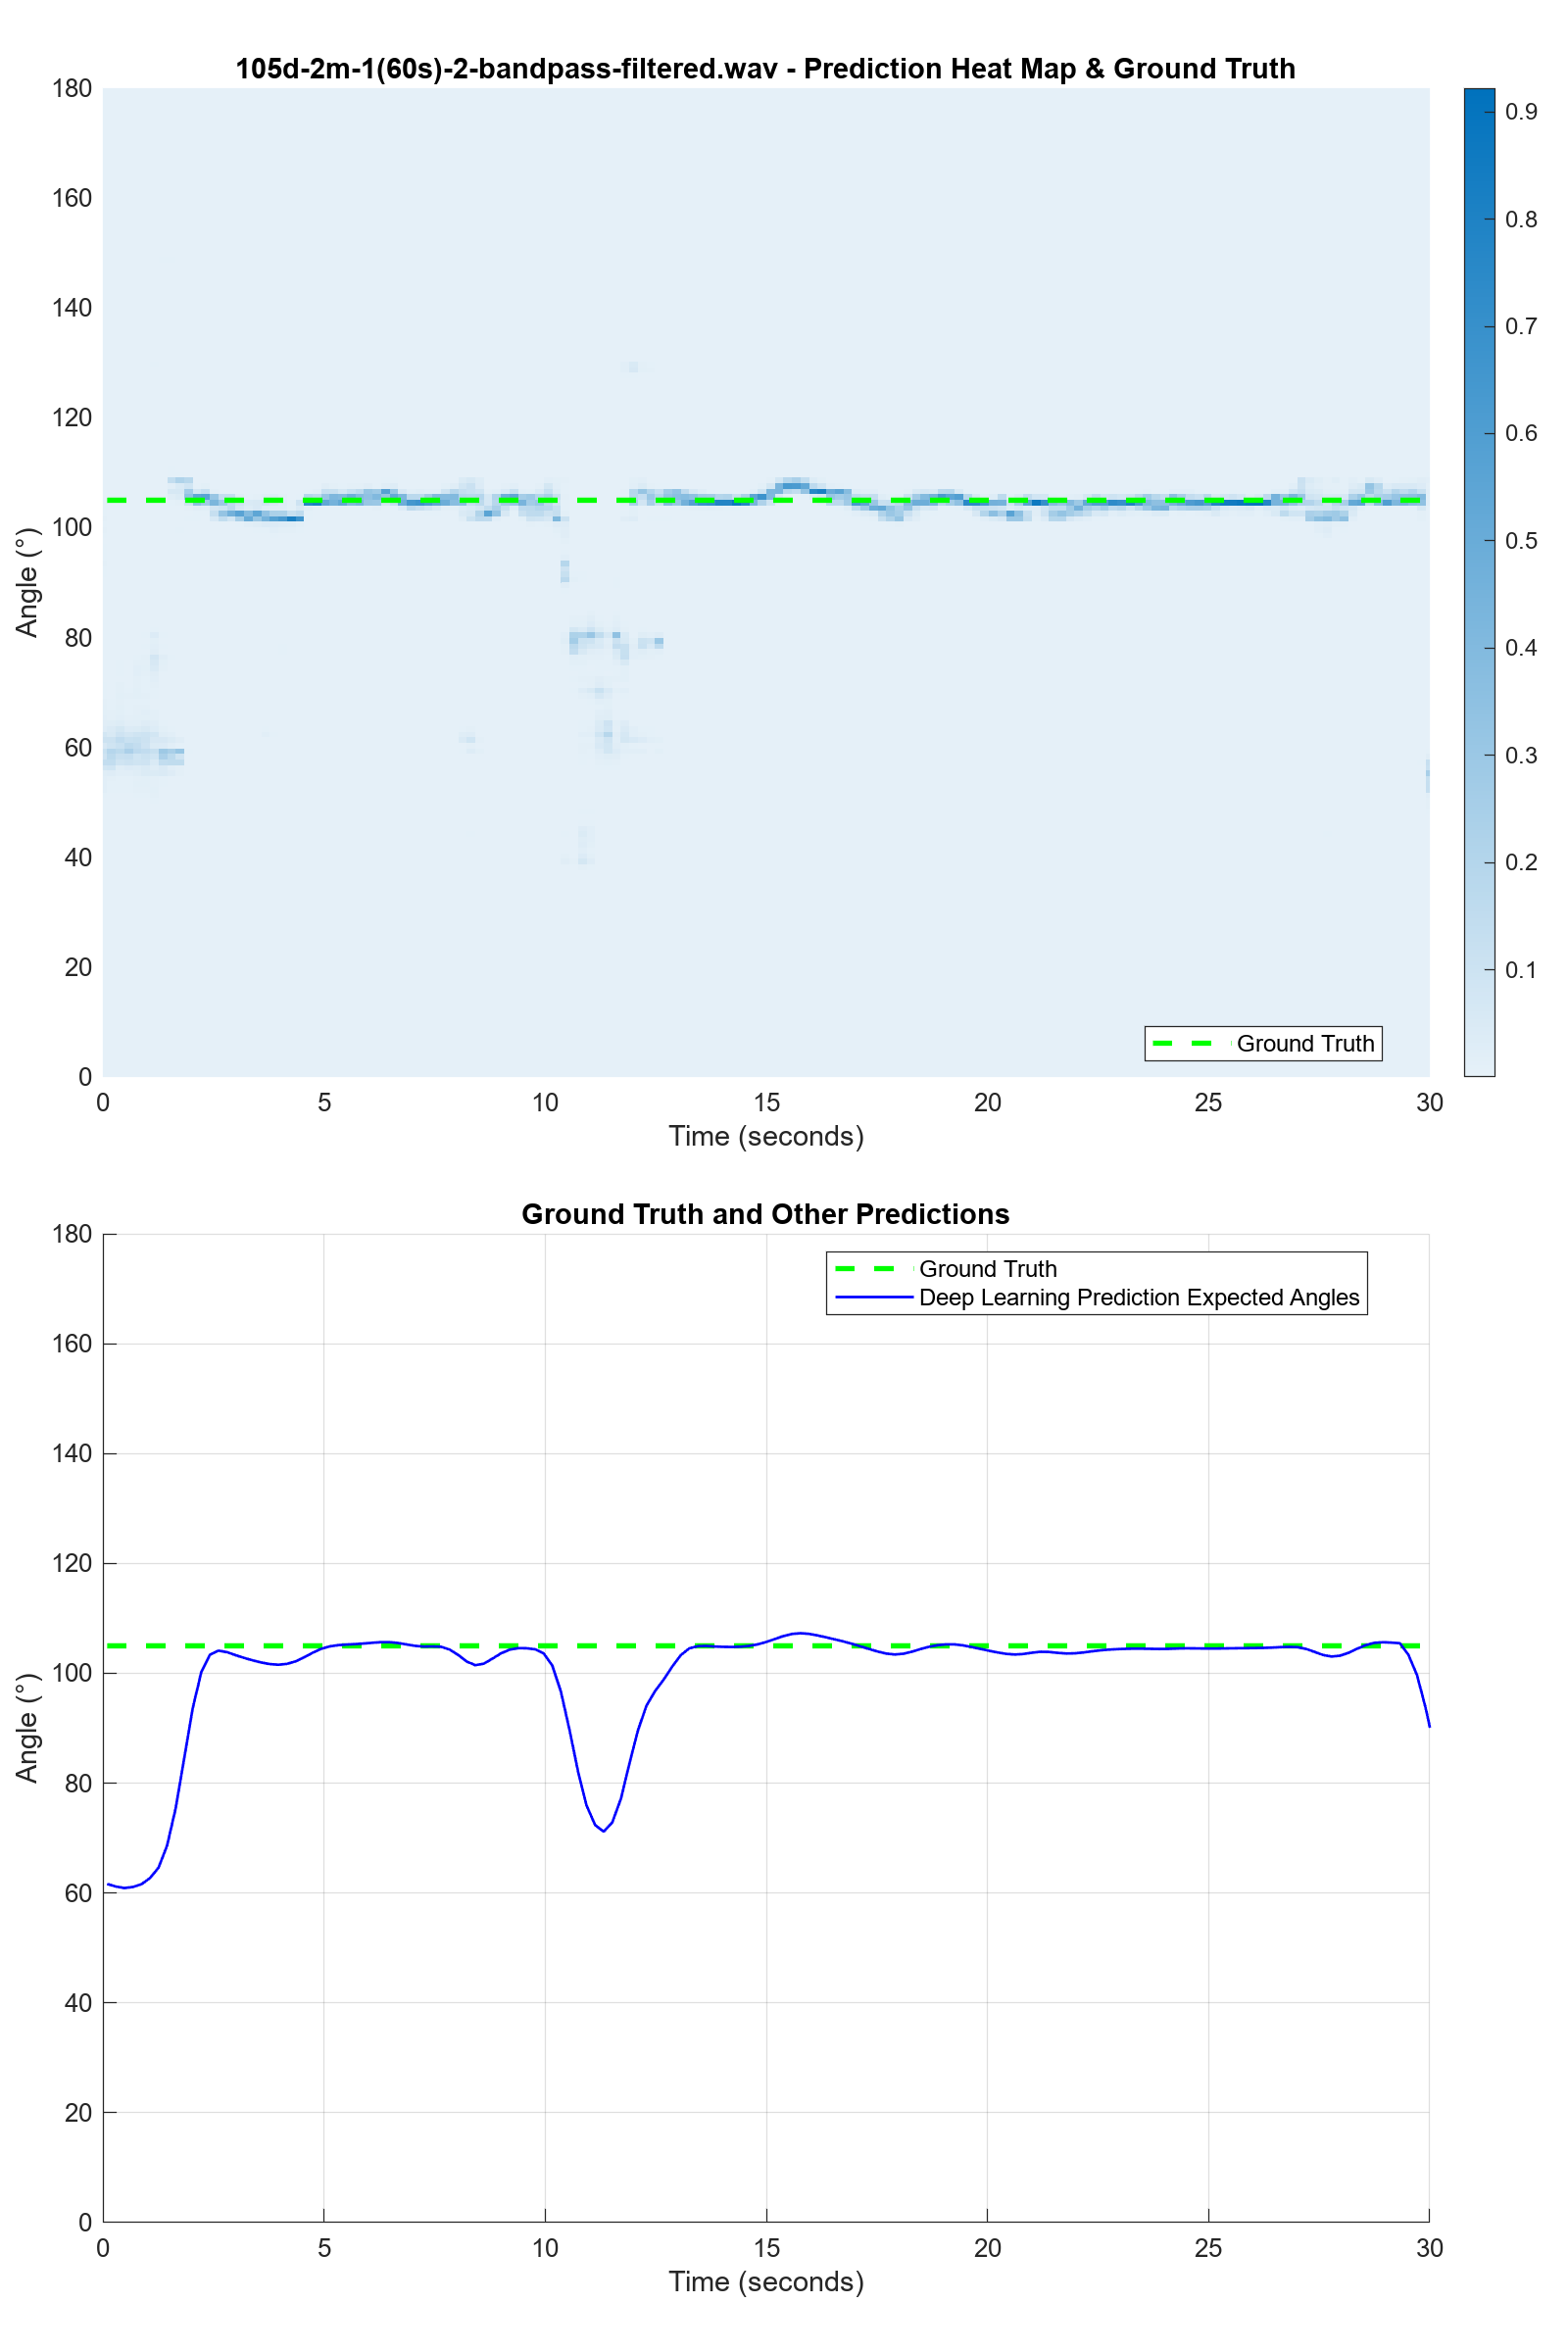

成功保存图像: 105d-2m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


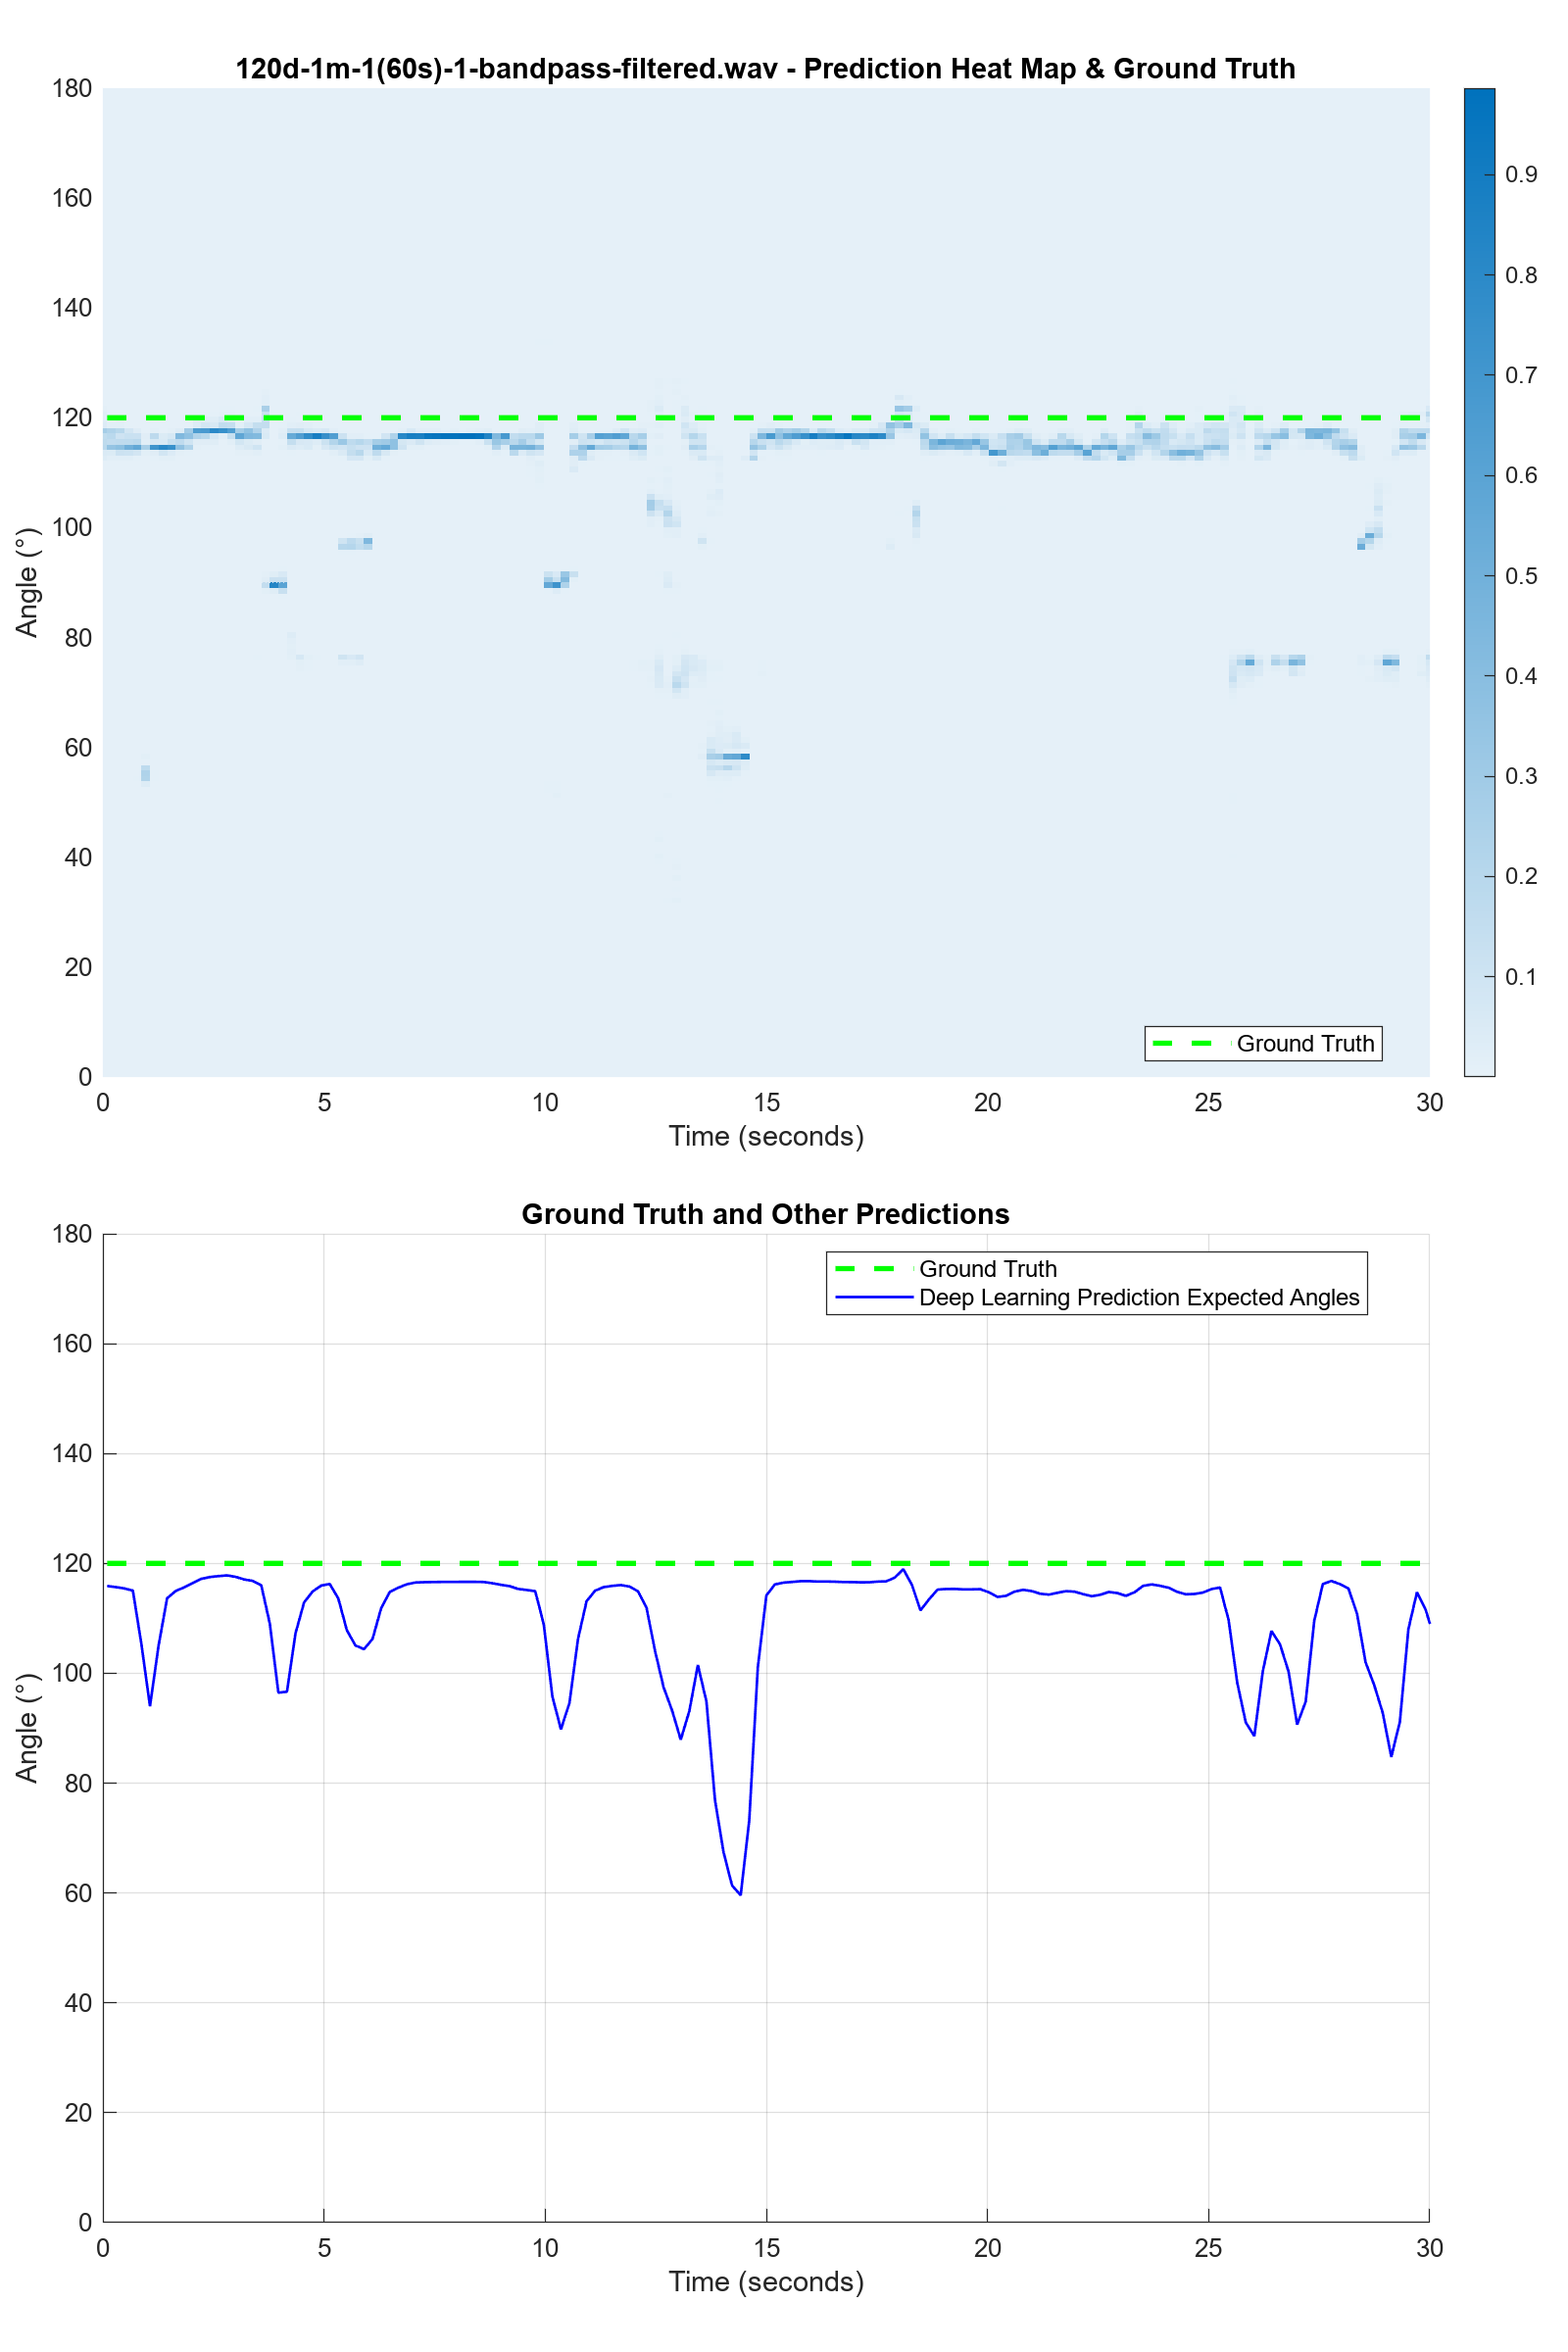

成功保存图像: 120d-1m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


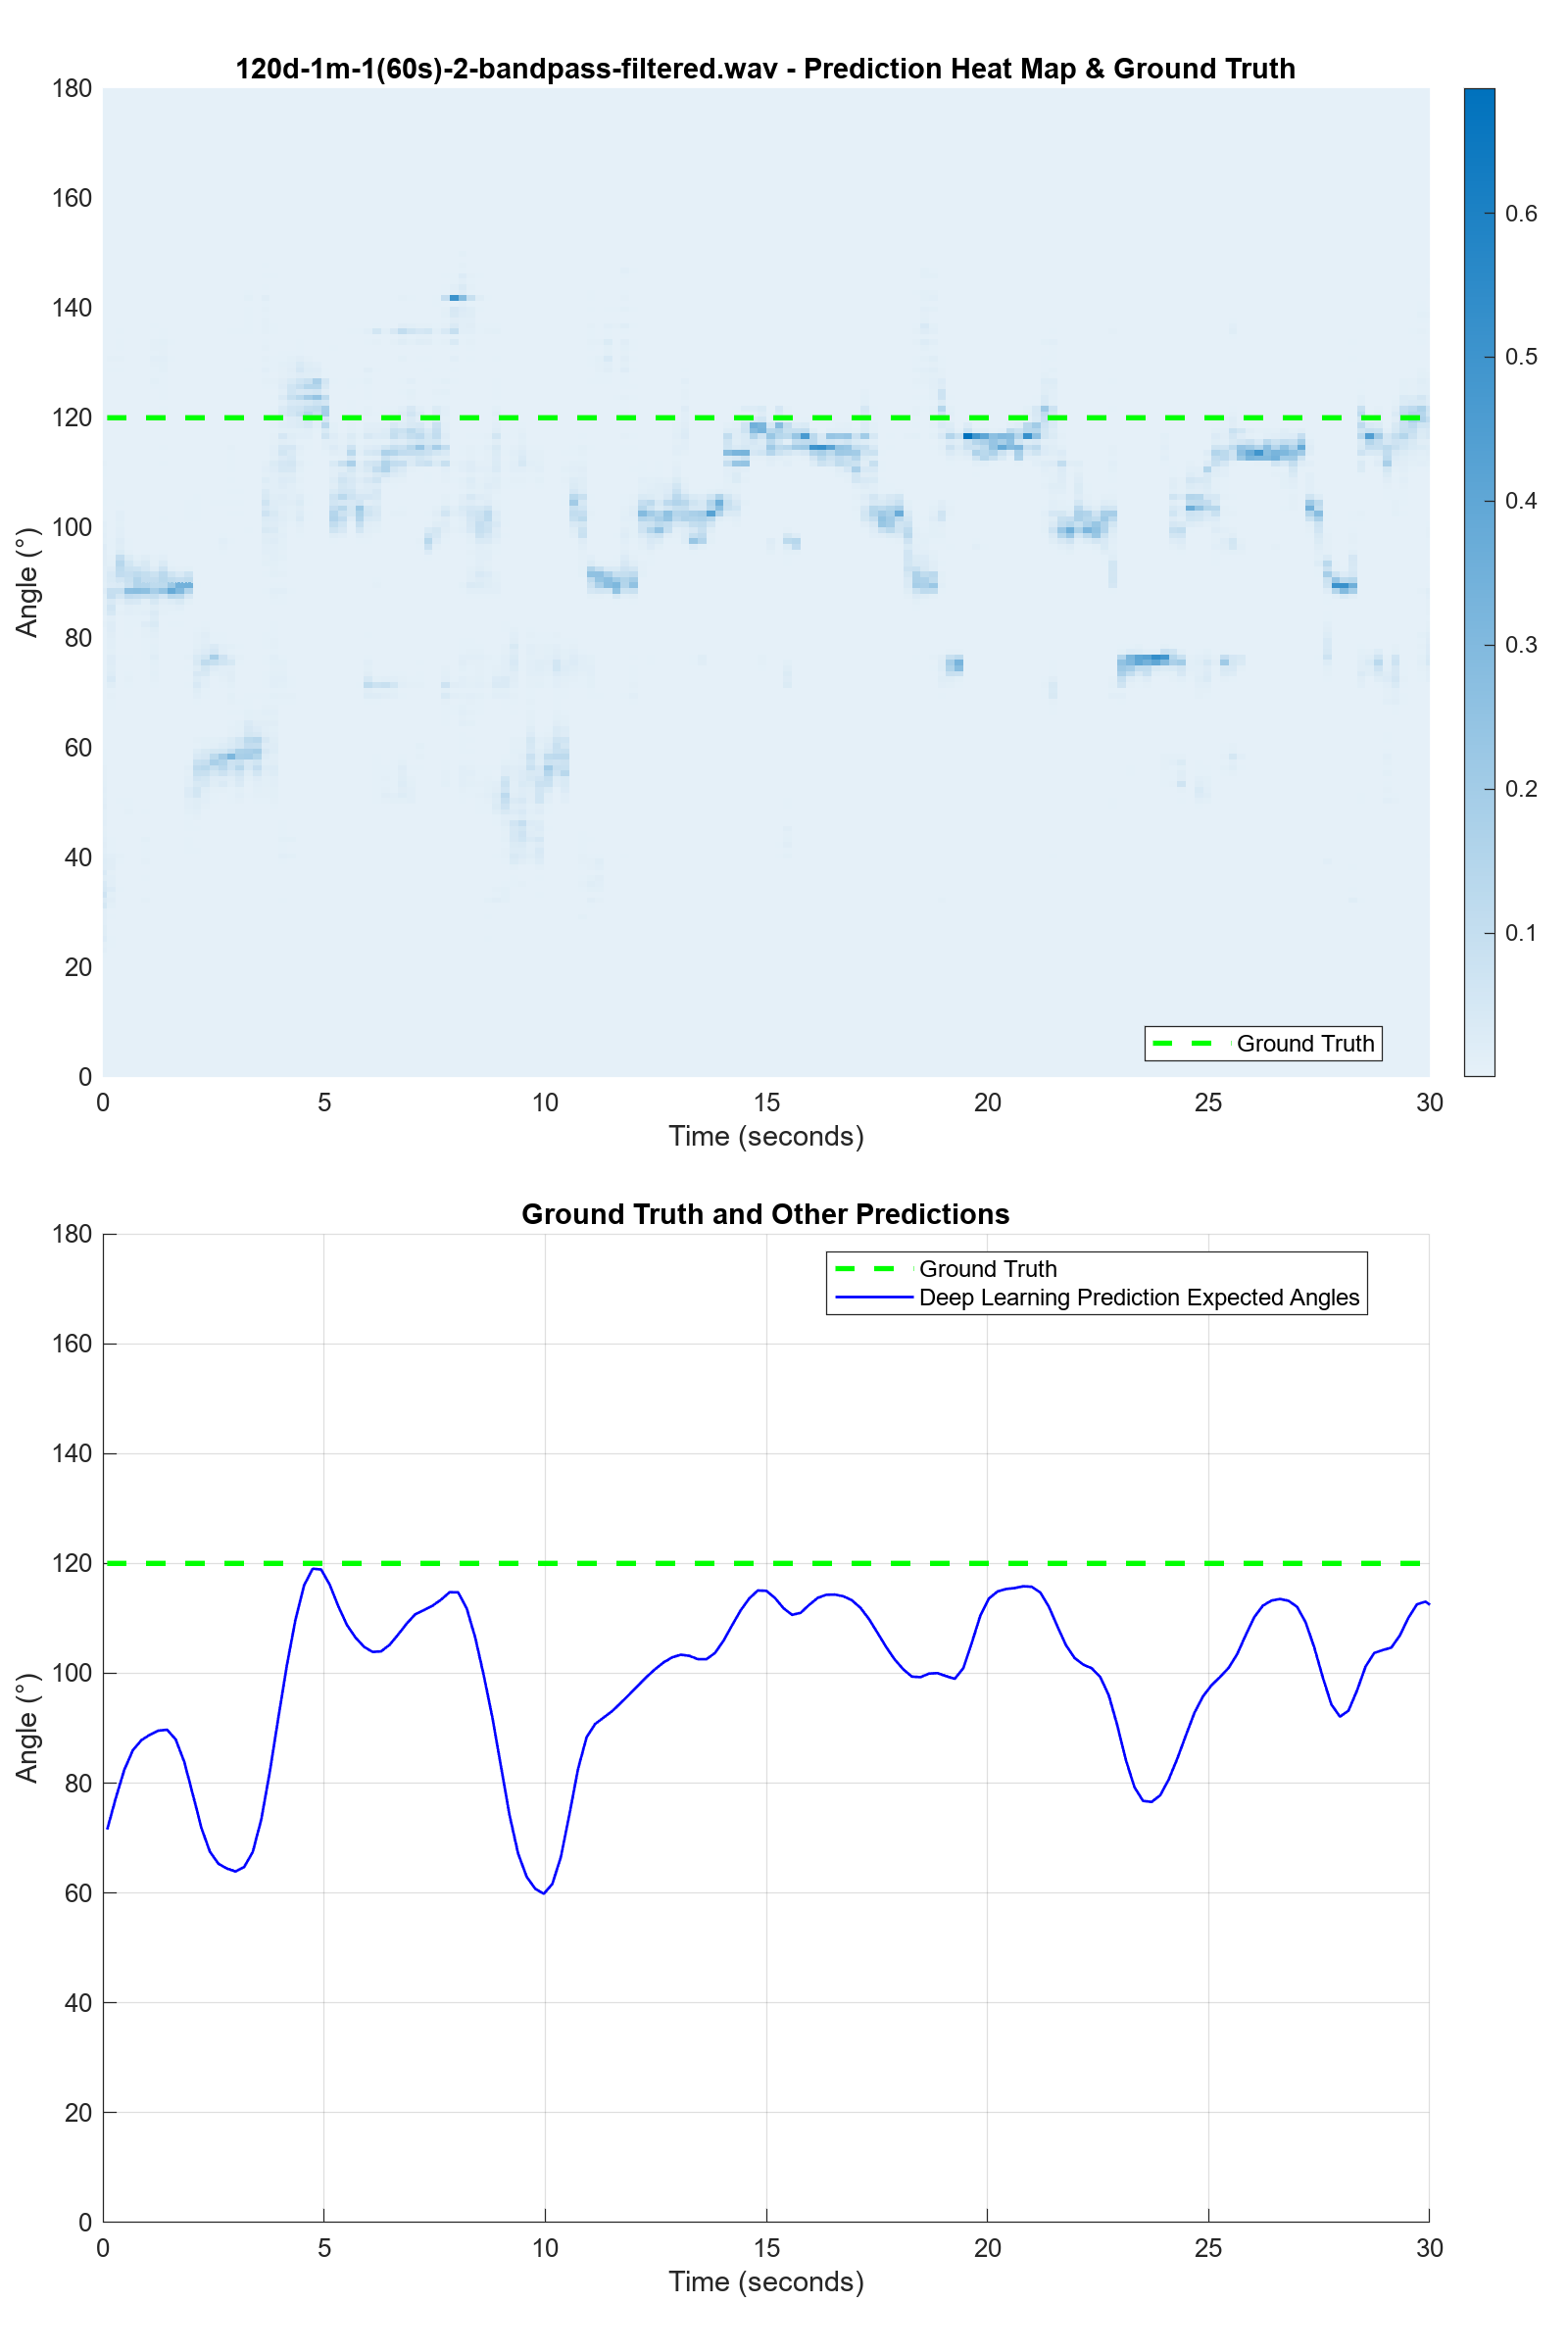

成功保存图像: 120d-1m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


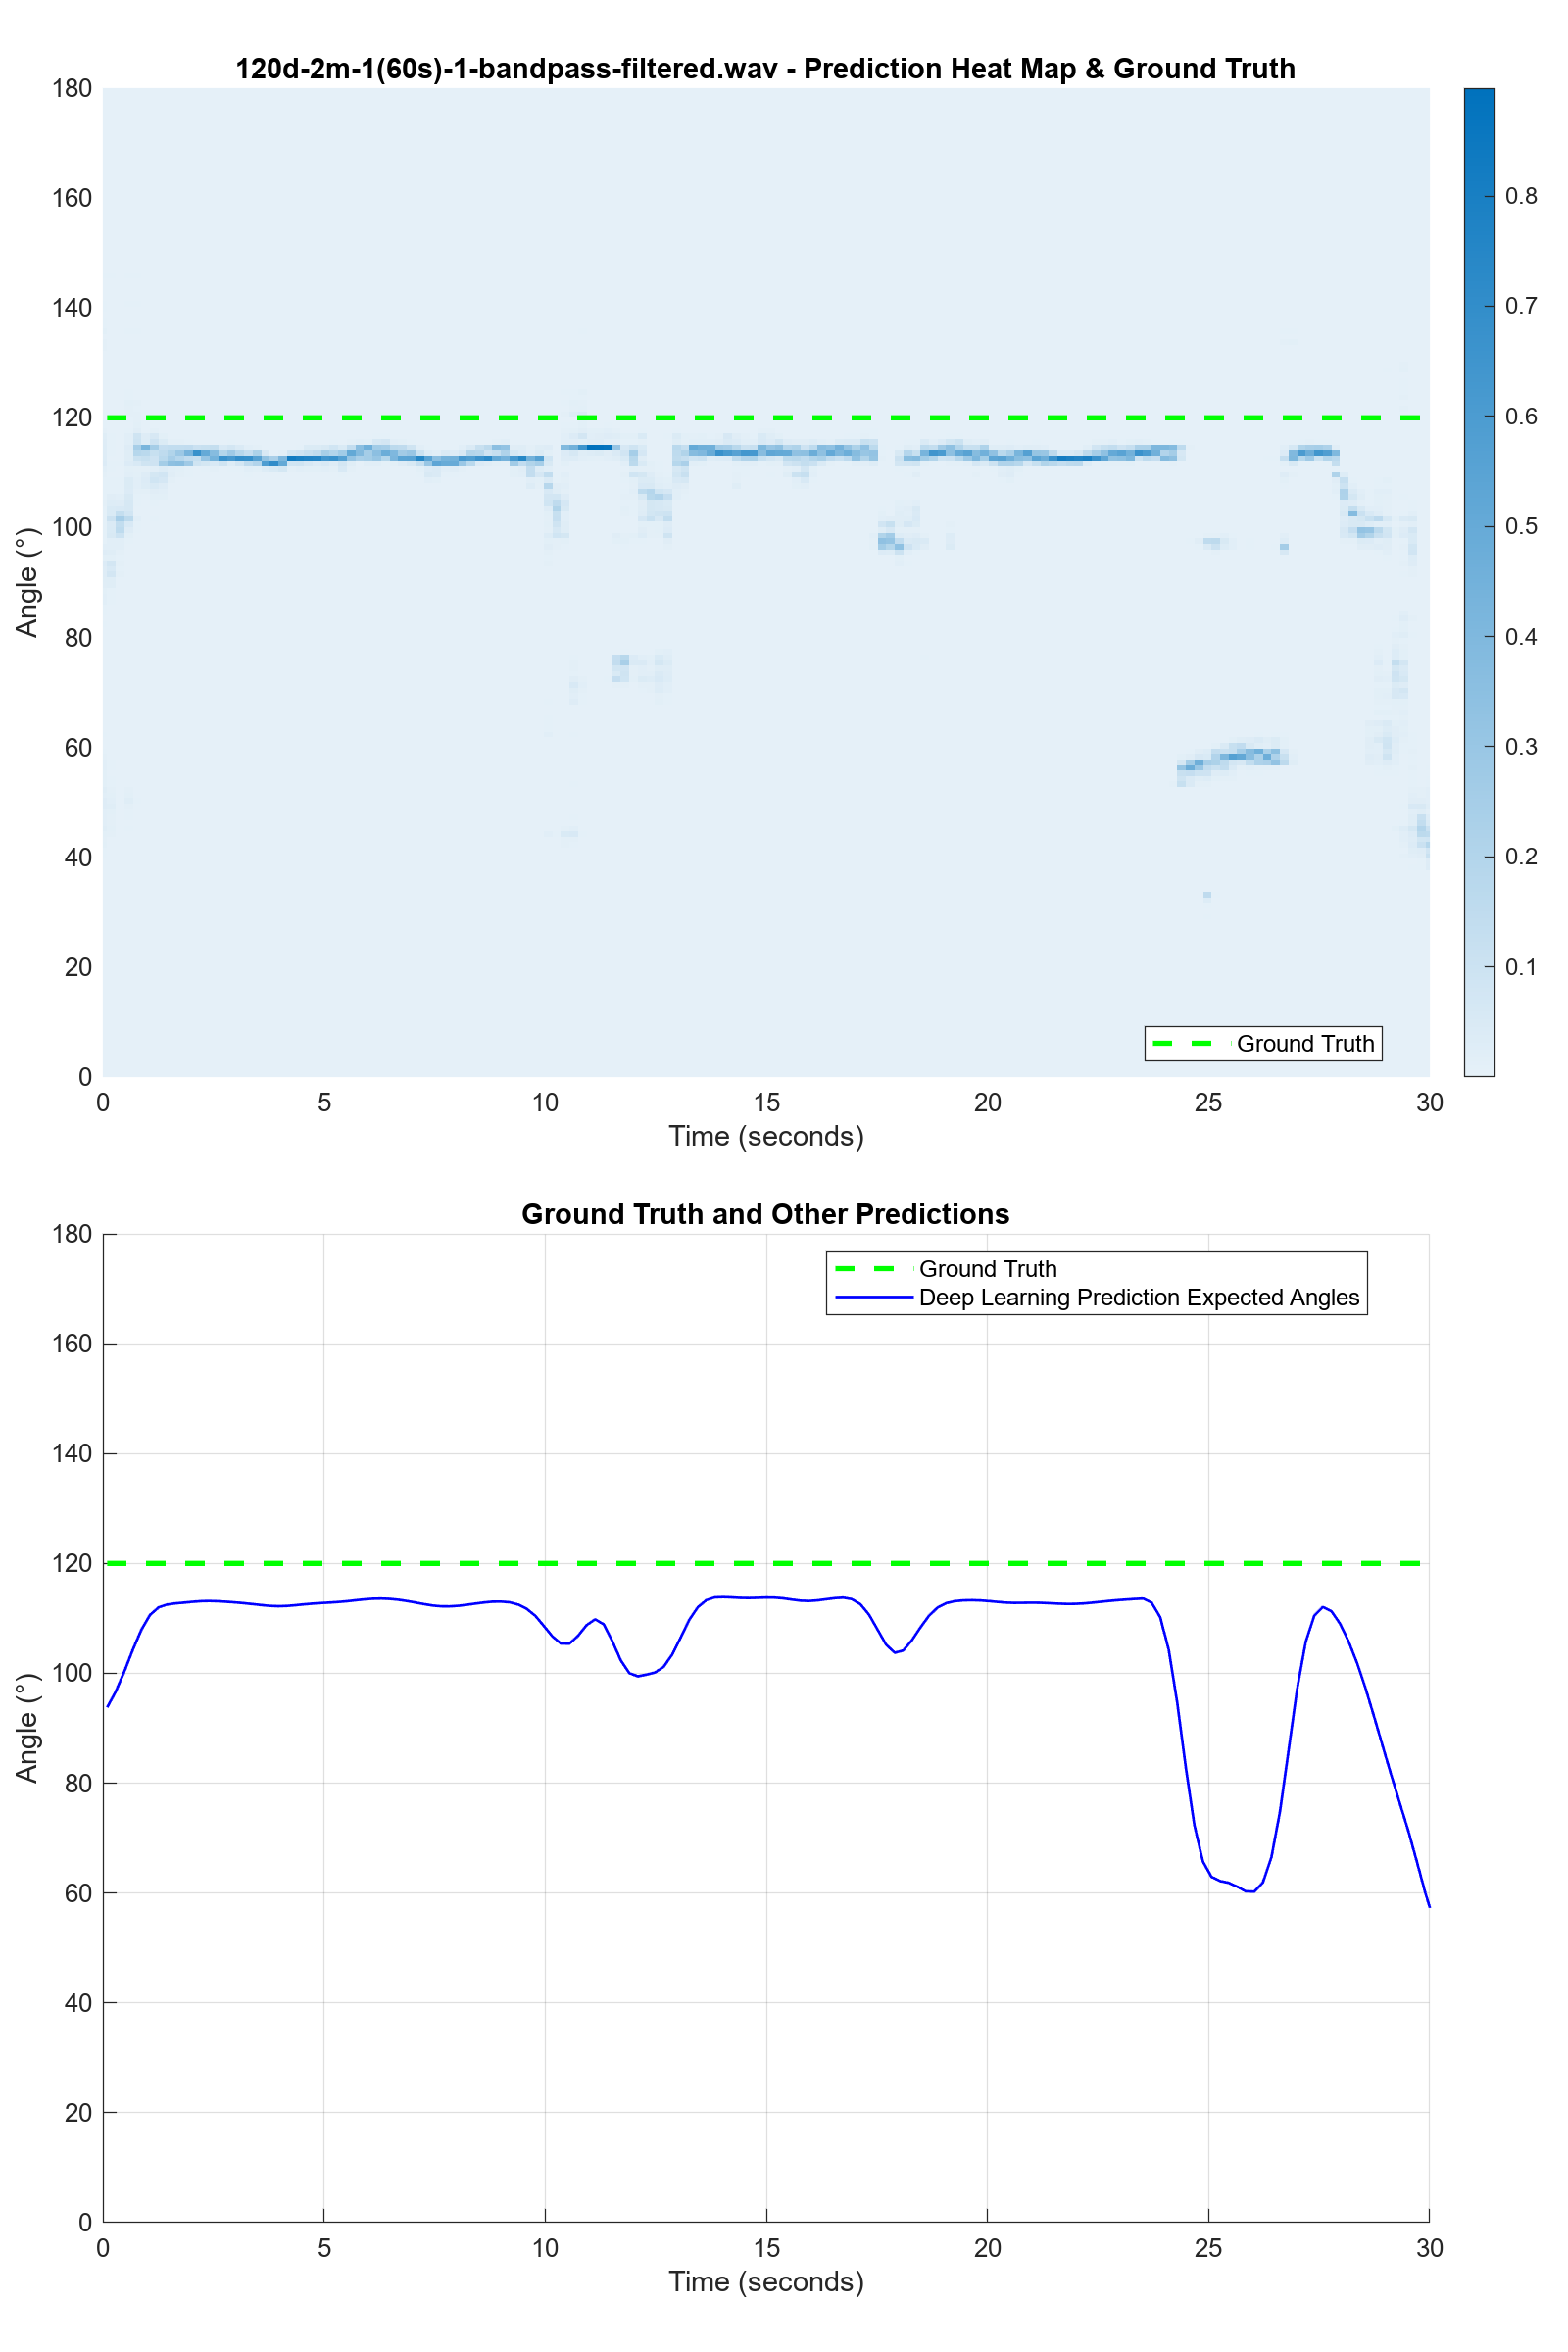

成功保存图像: 120d-2m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


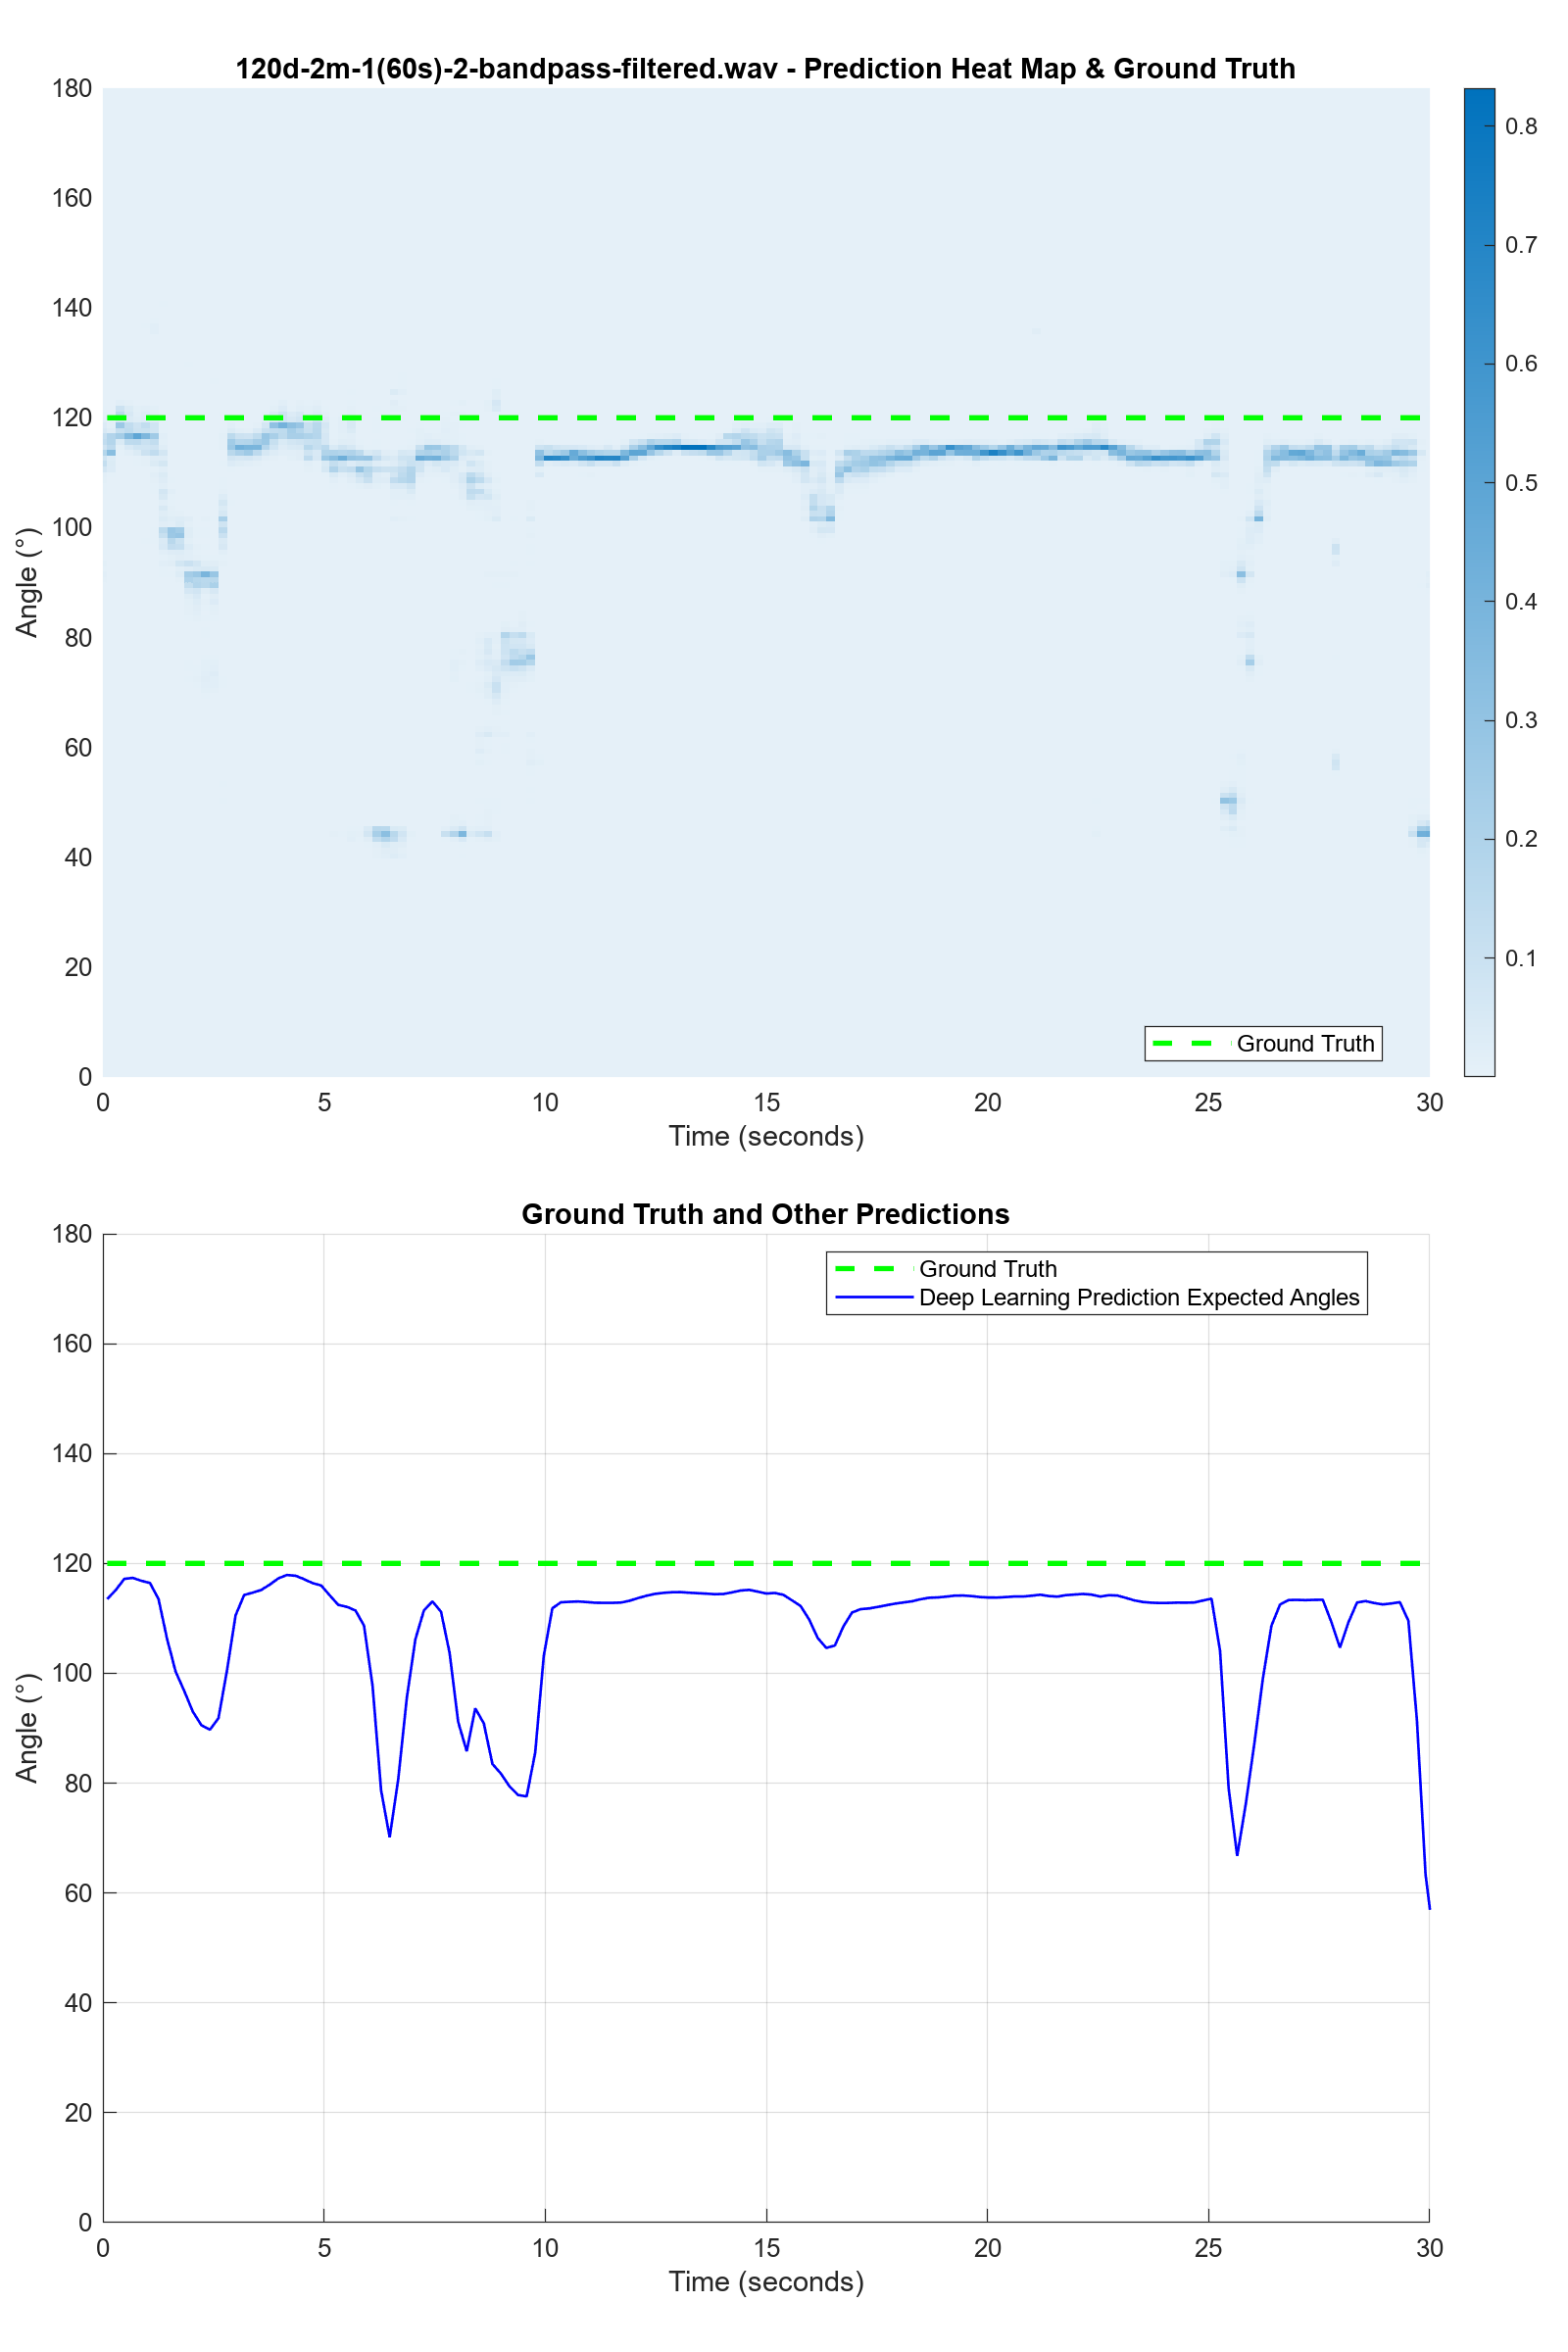

成功保存图像: 120d-2m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


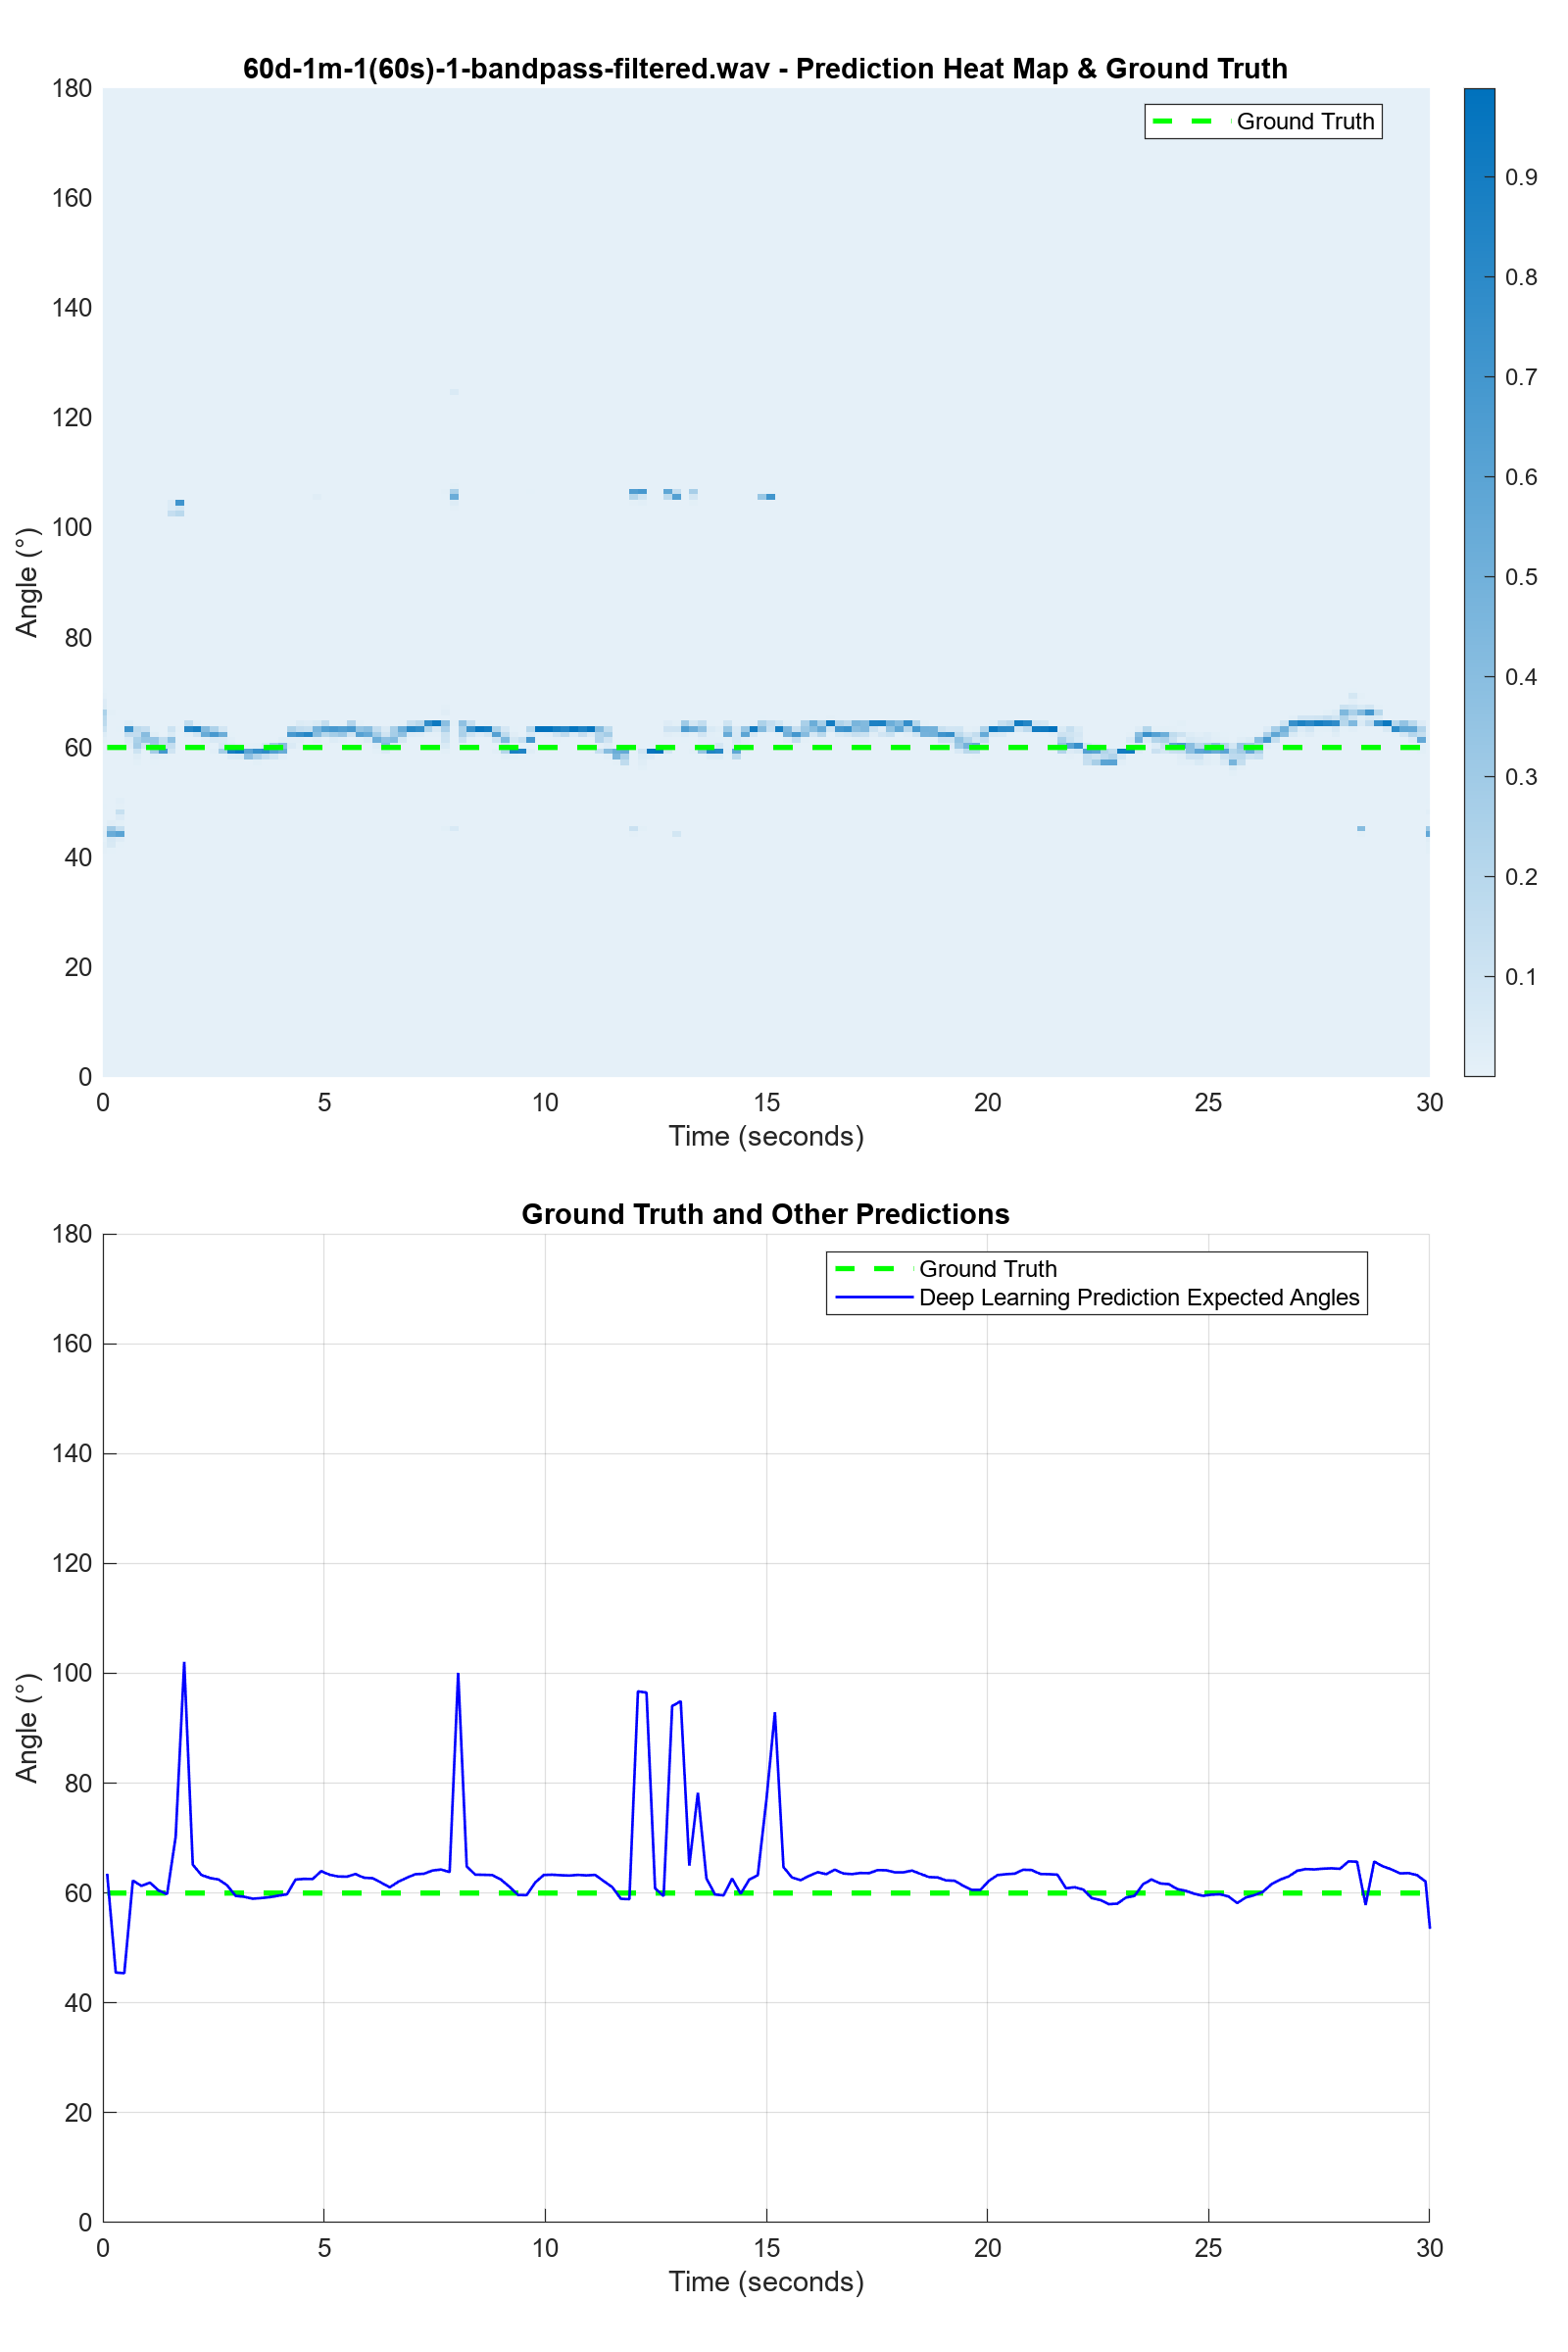

成功保存图像: 60d-1m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


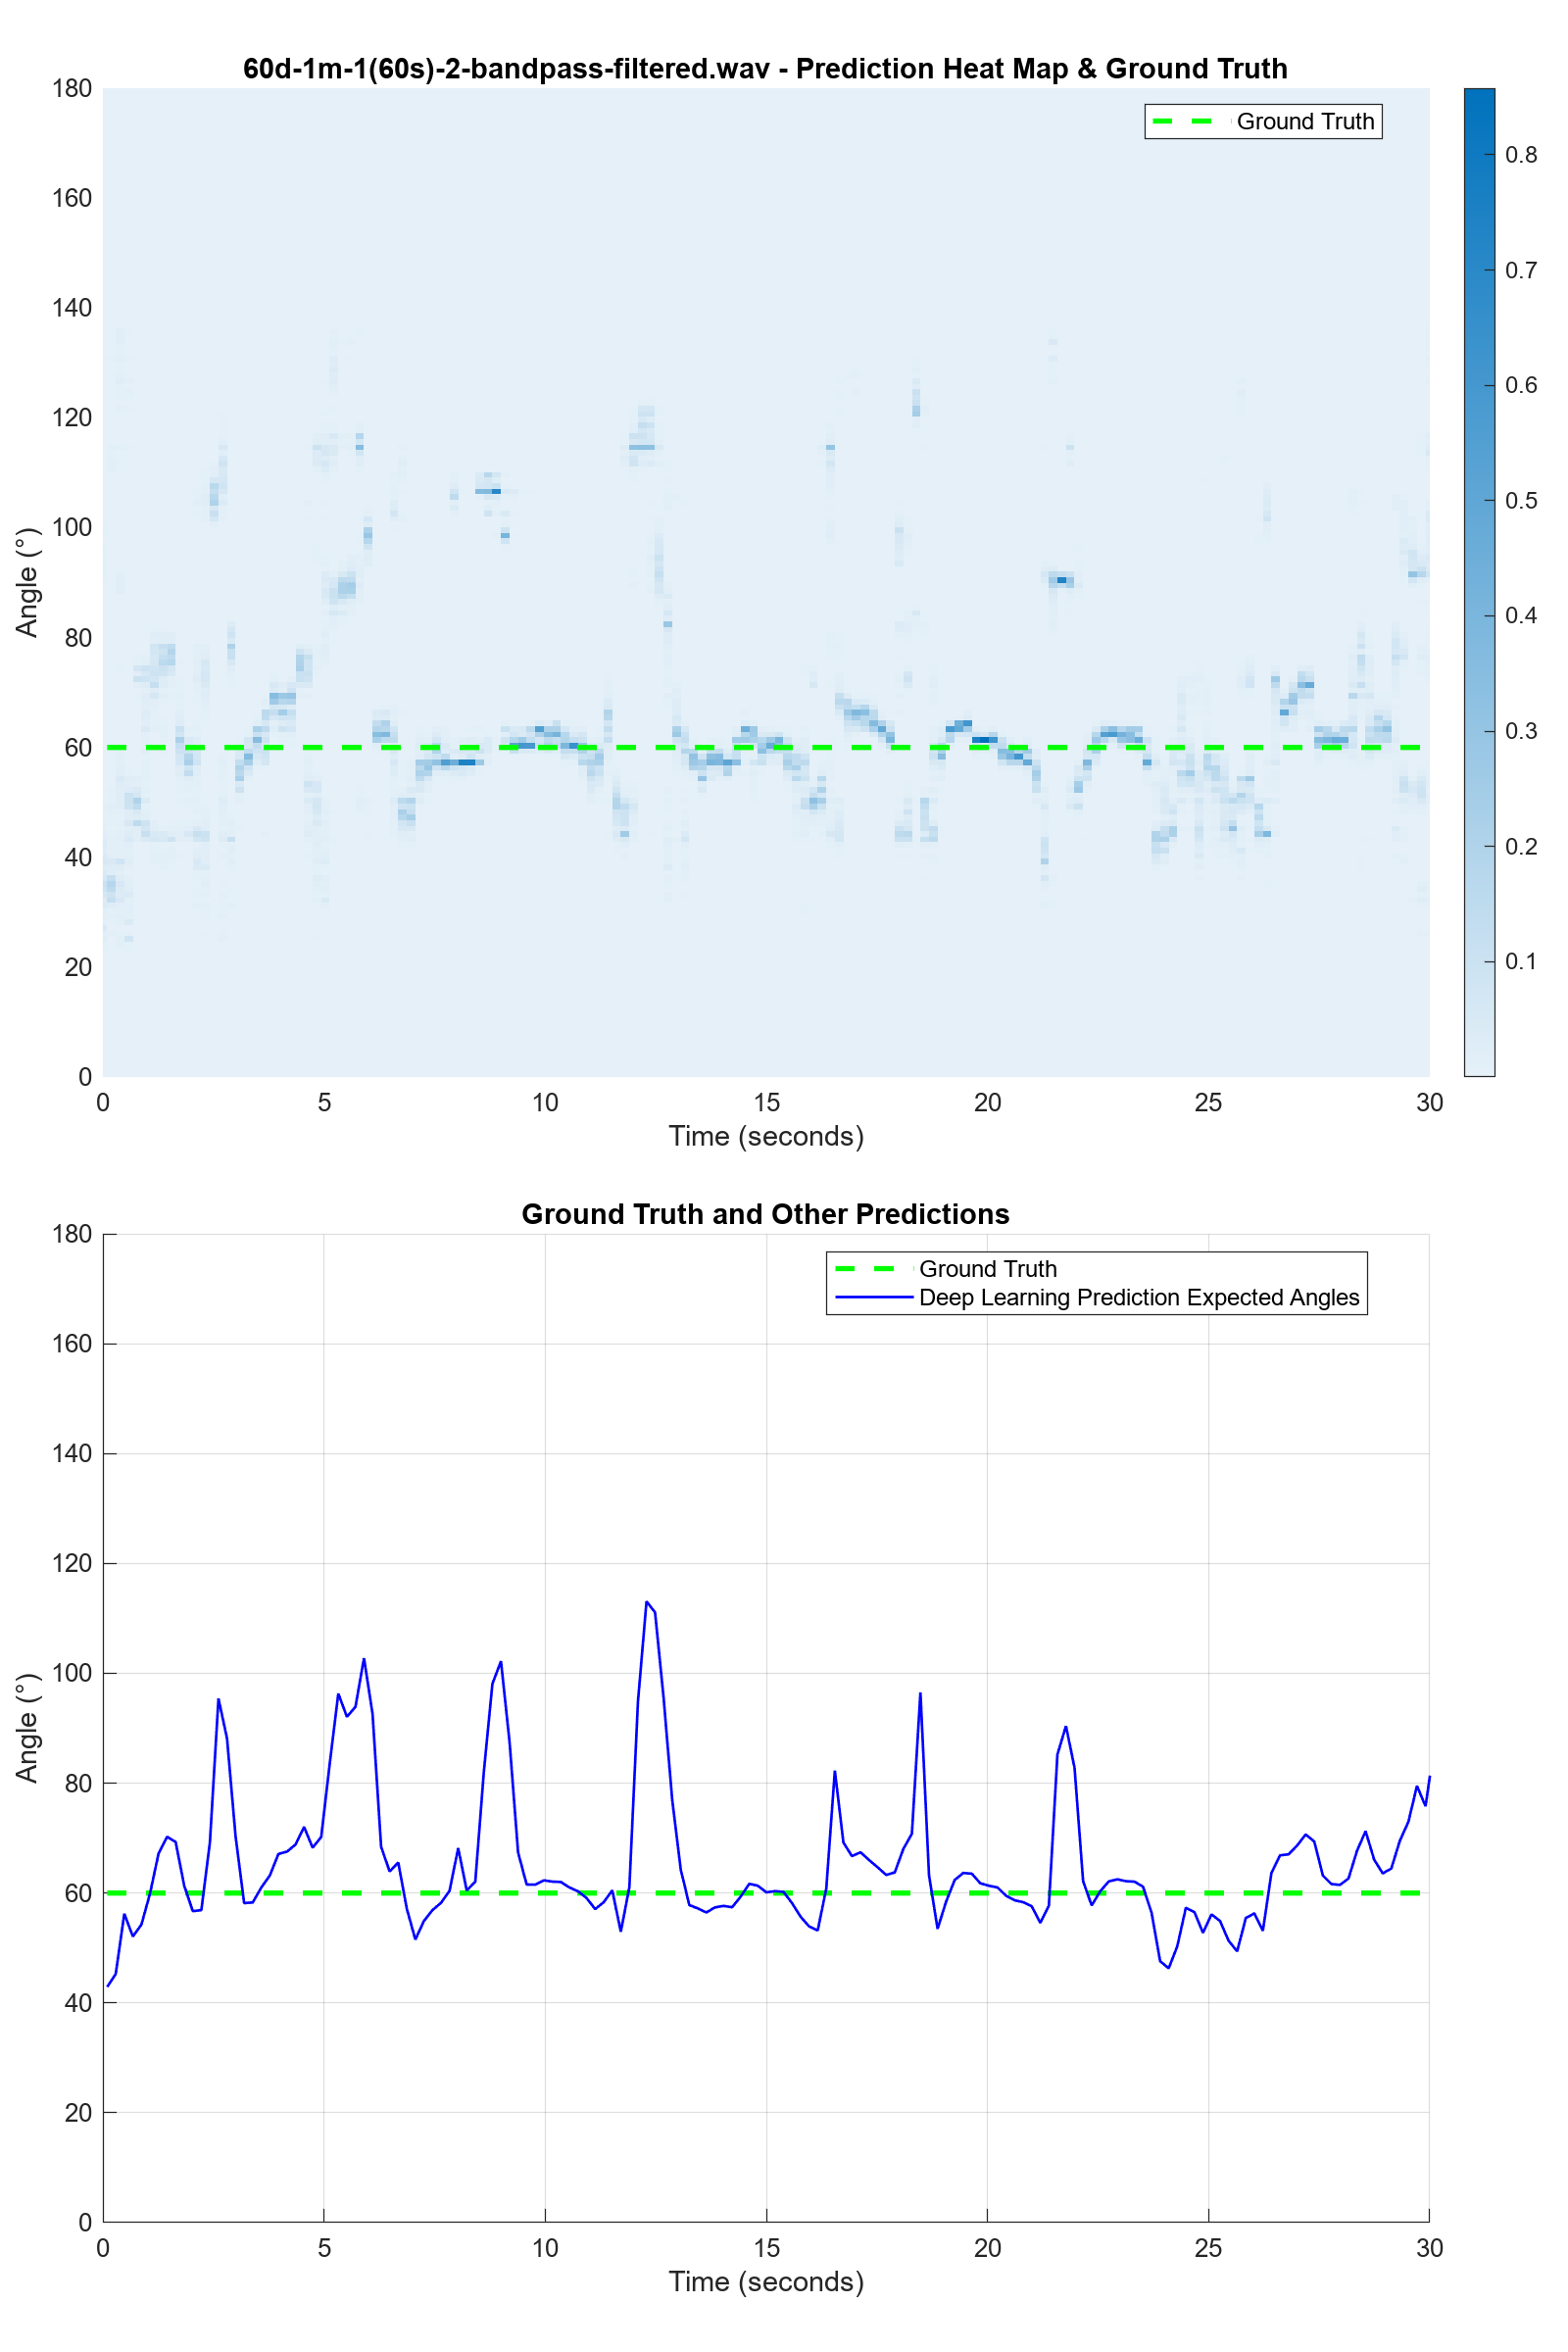

成功保存图像: 60d-1m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


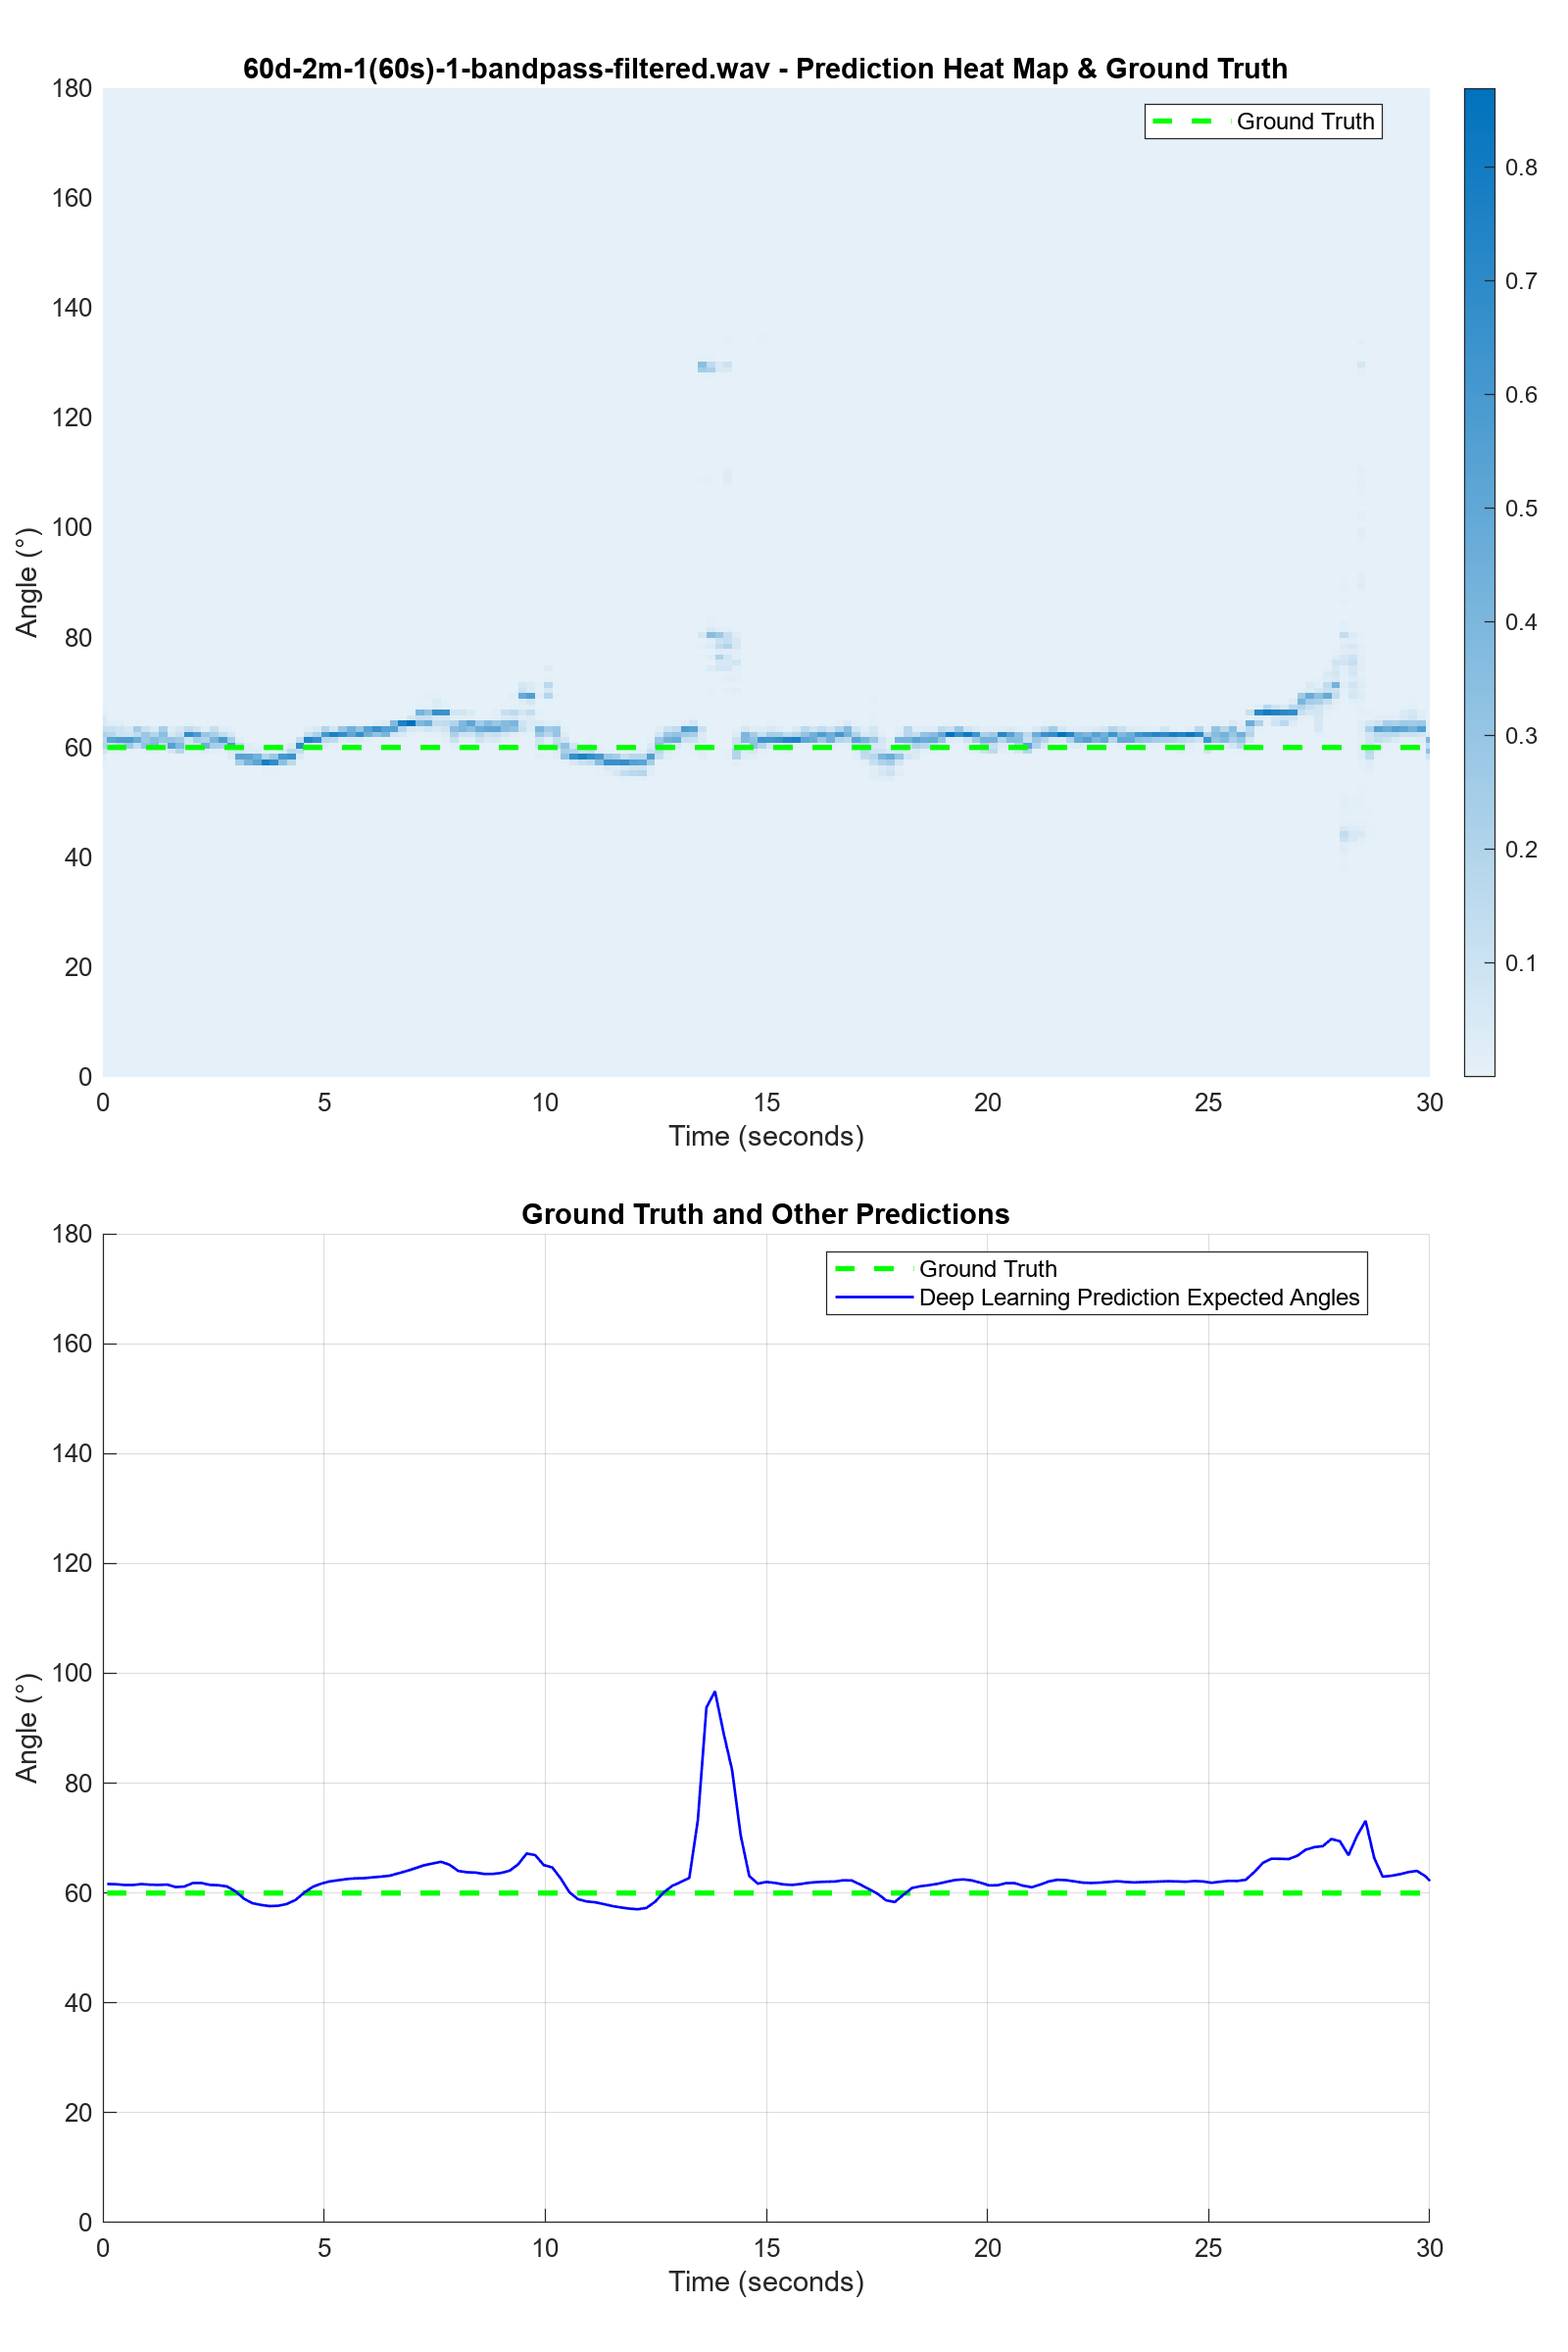

成功保存图像: 60d-2m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


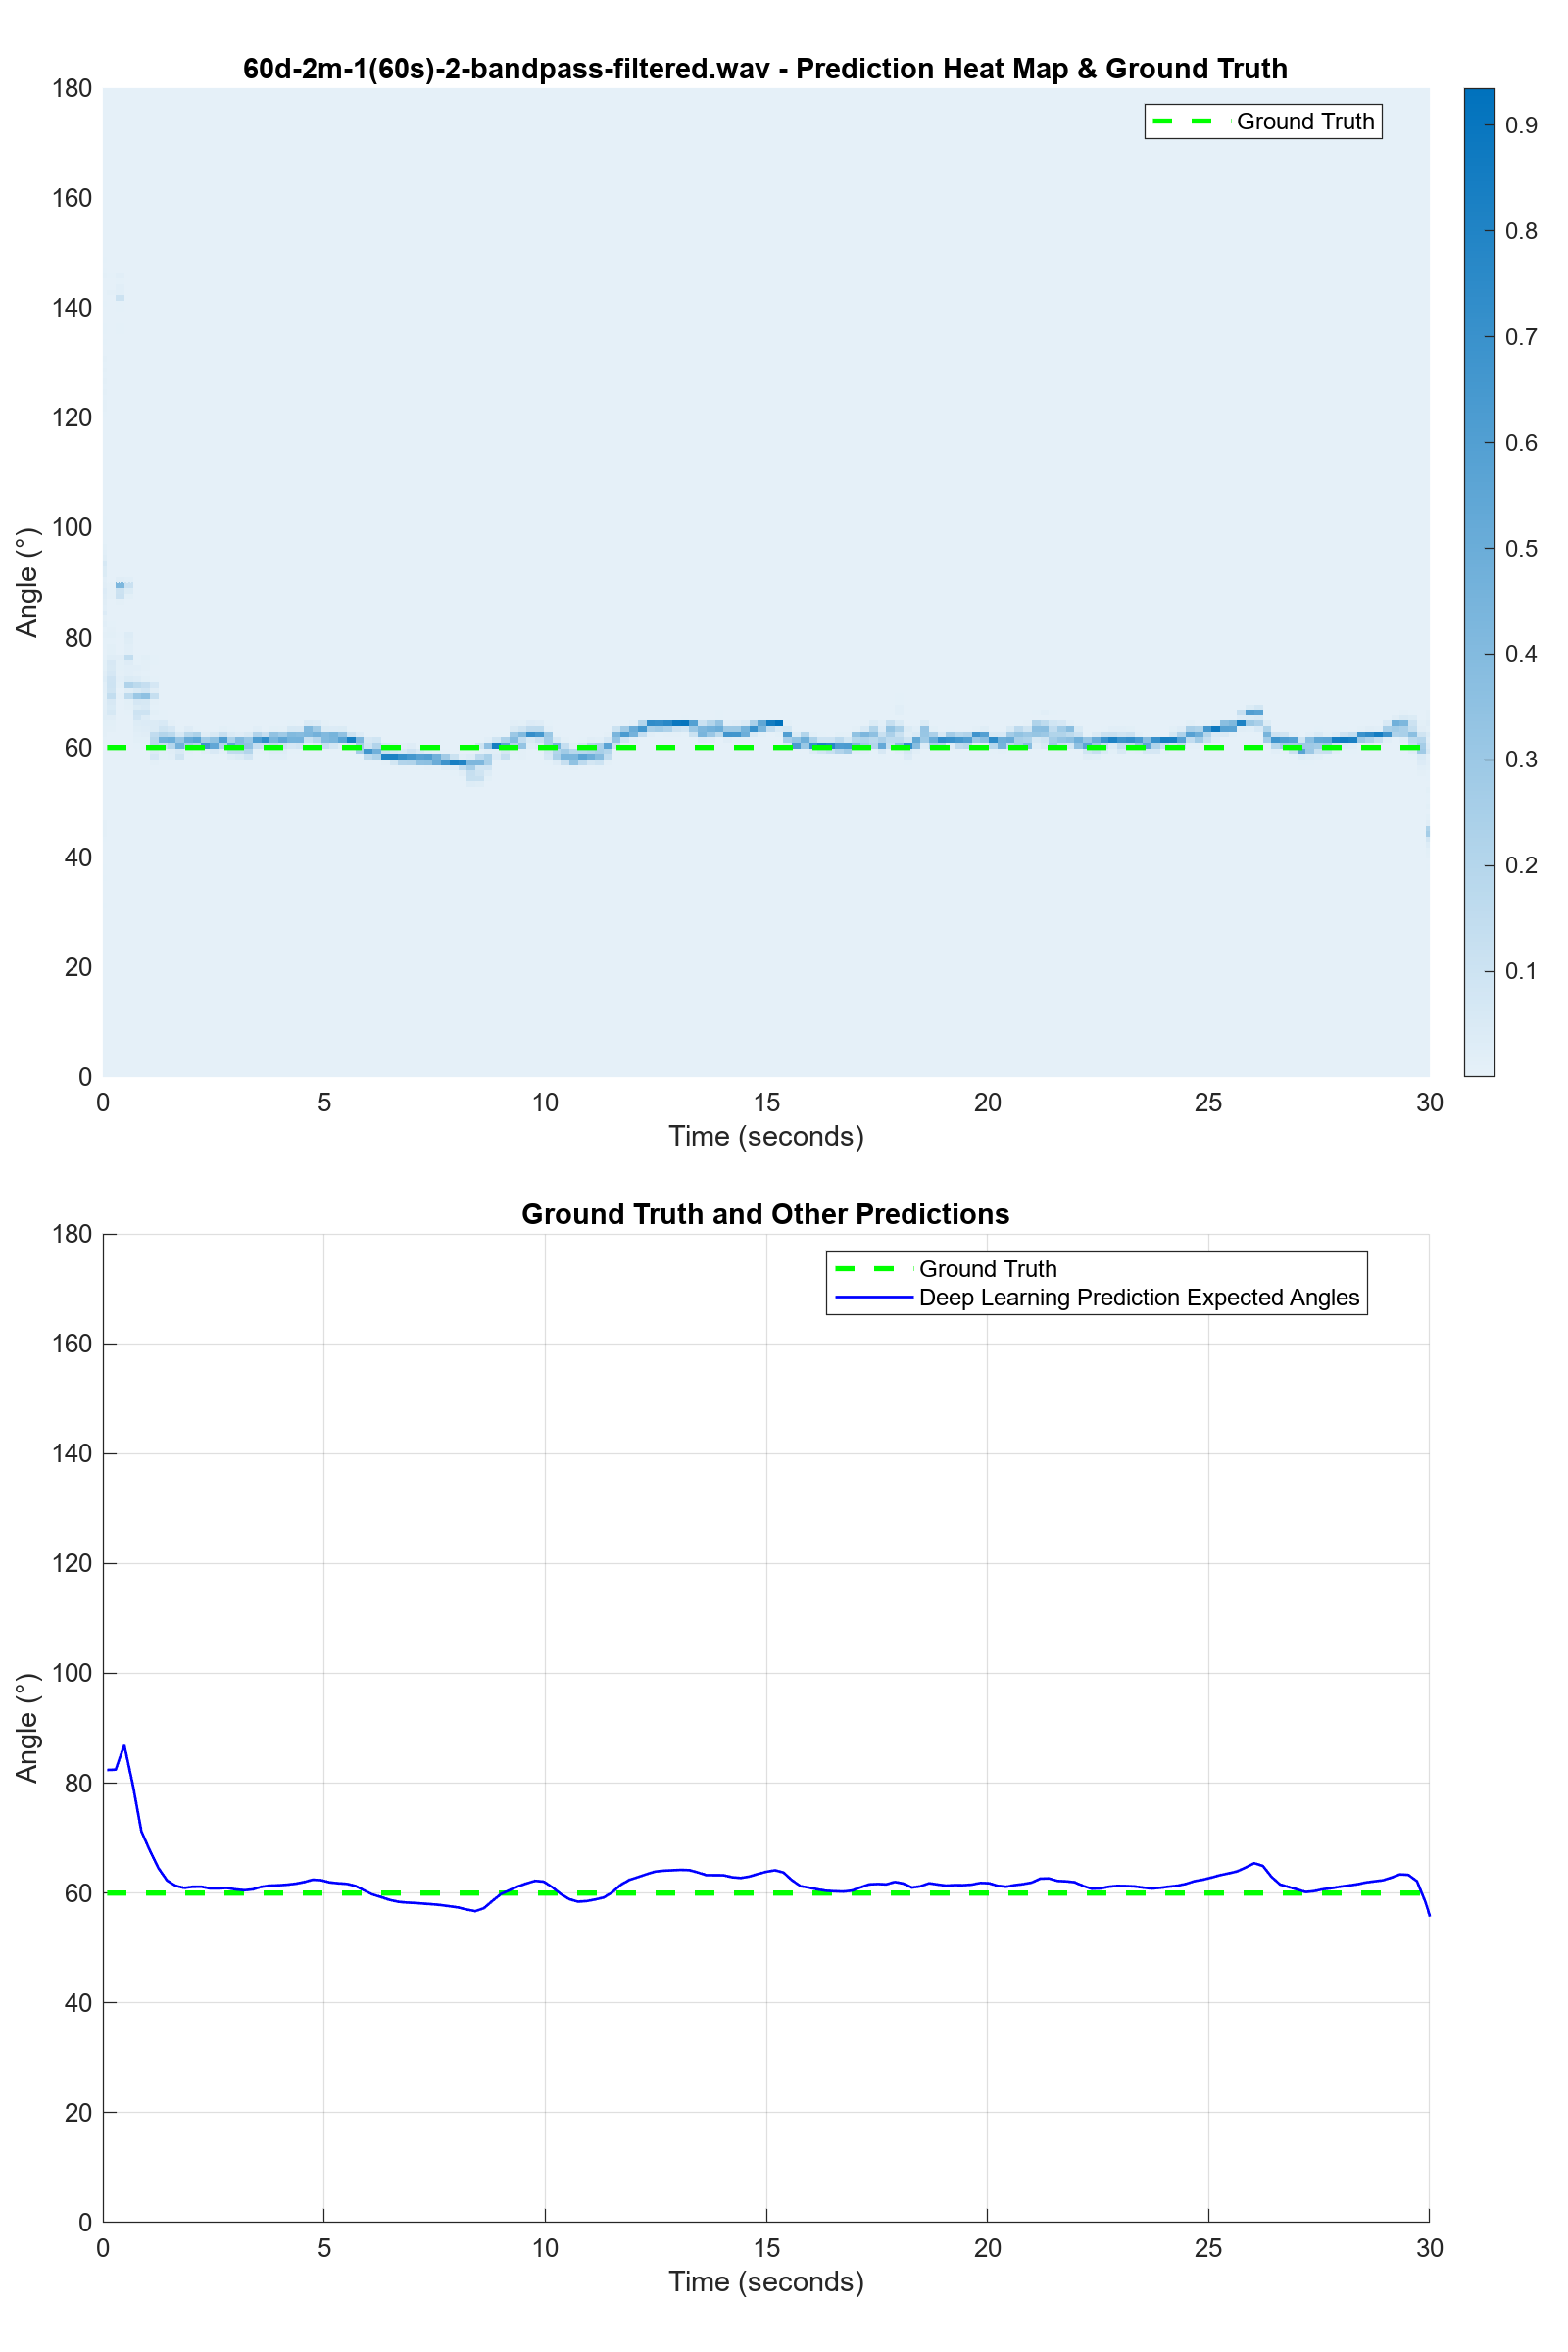

成功保存图像: 60d-2m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


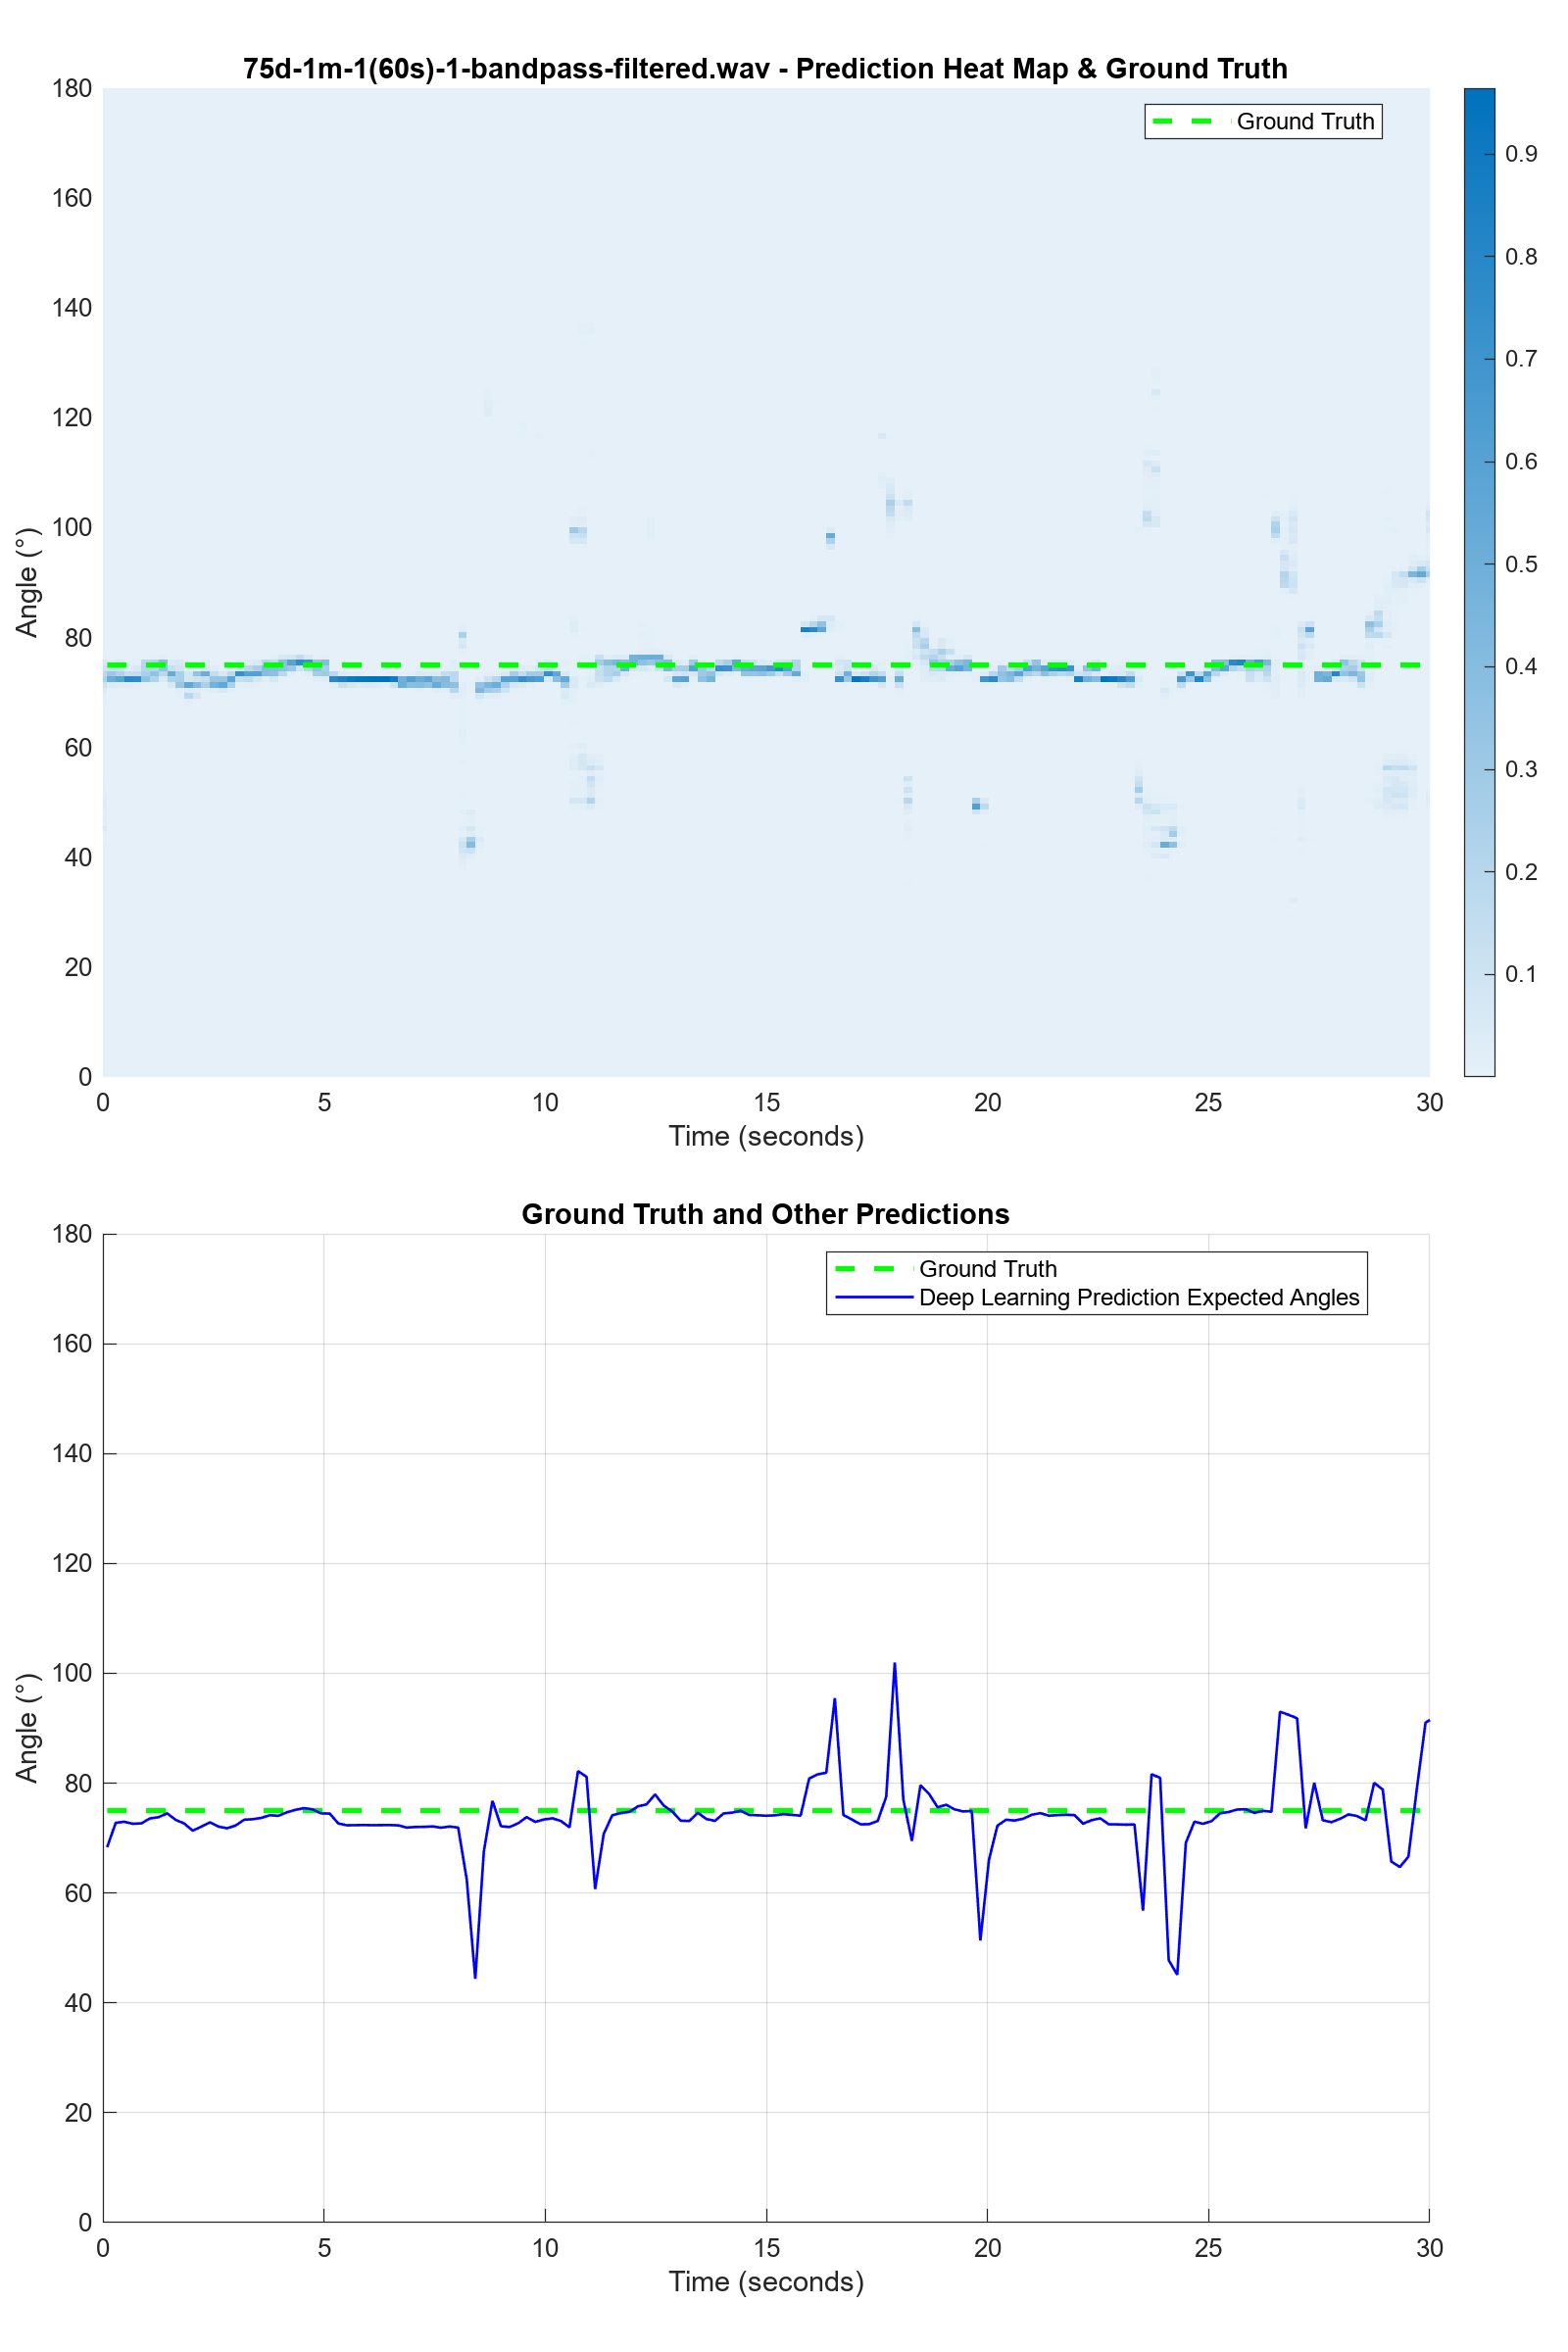

成功保存图像: 75d-1m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


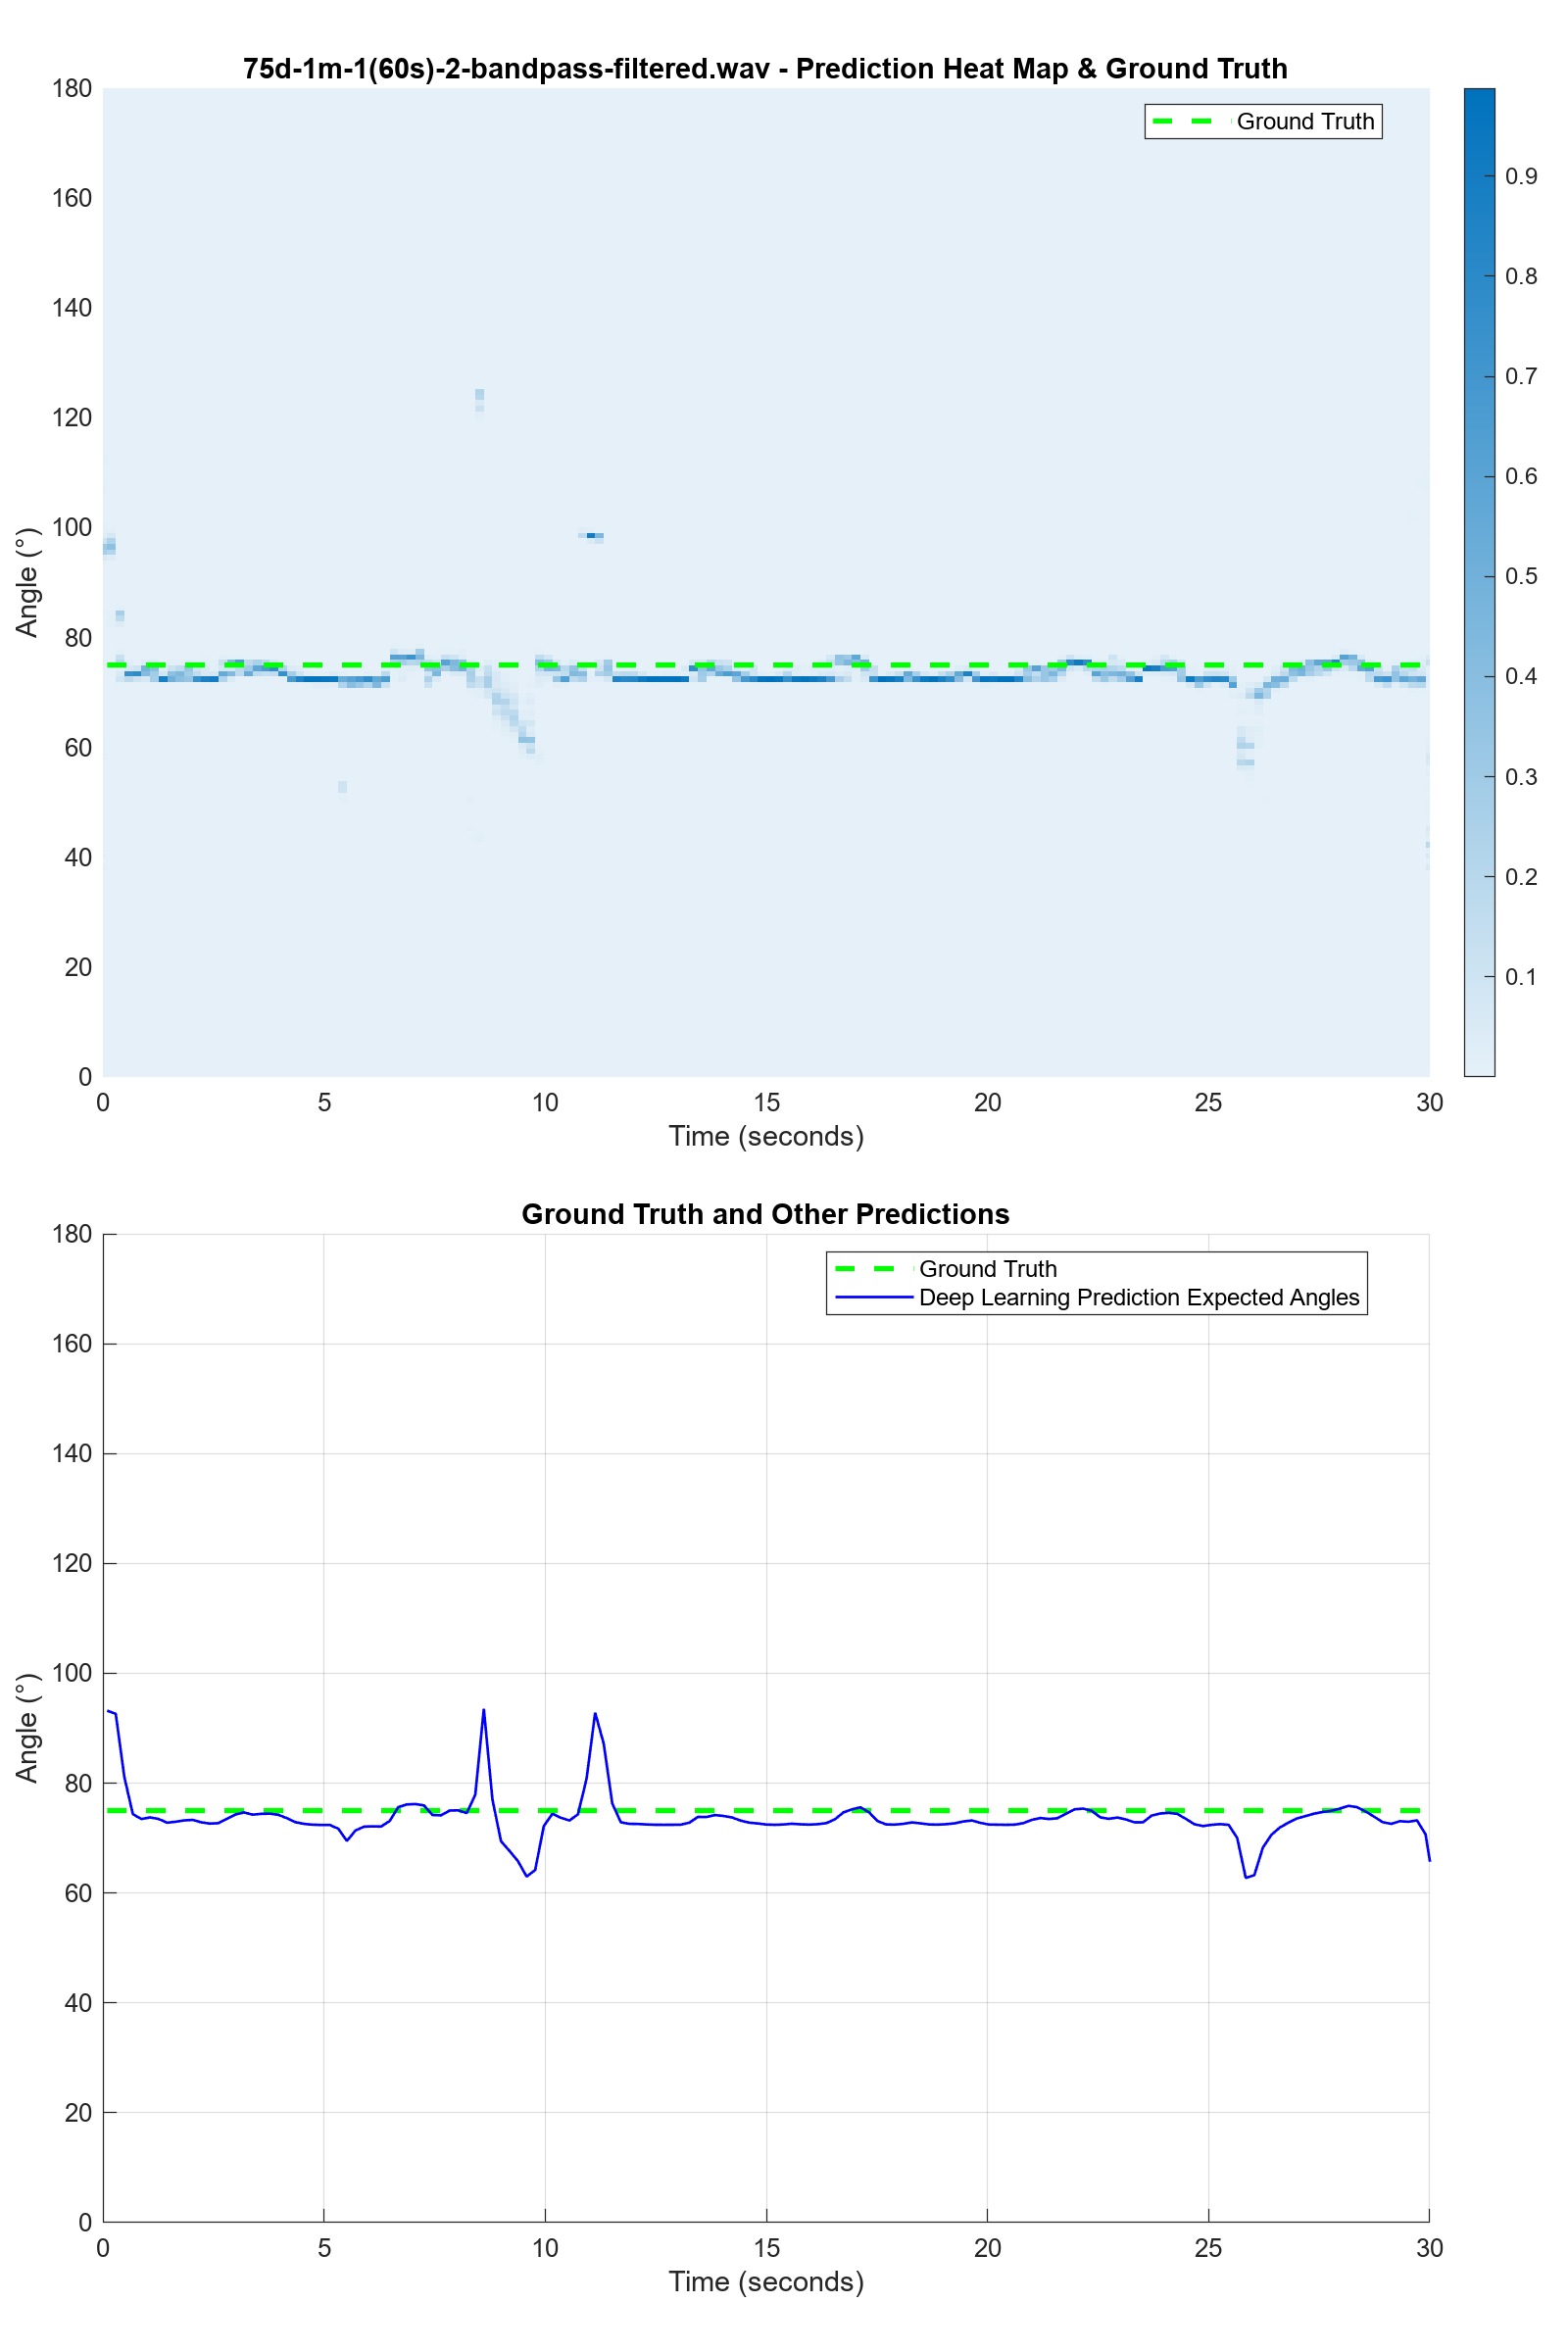

成功保存图像: 75d-1m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


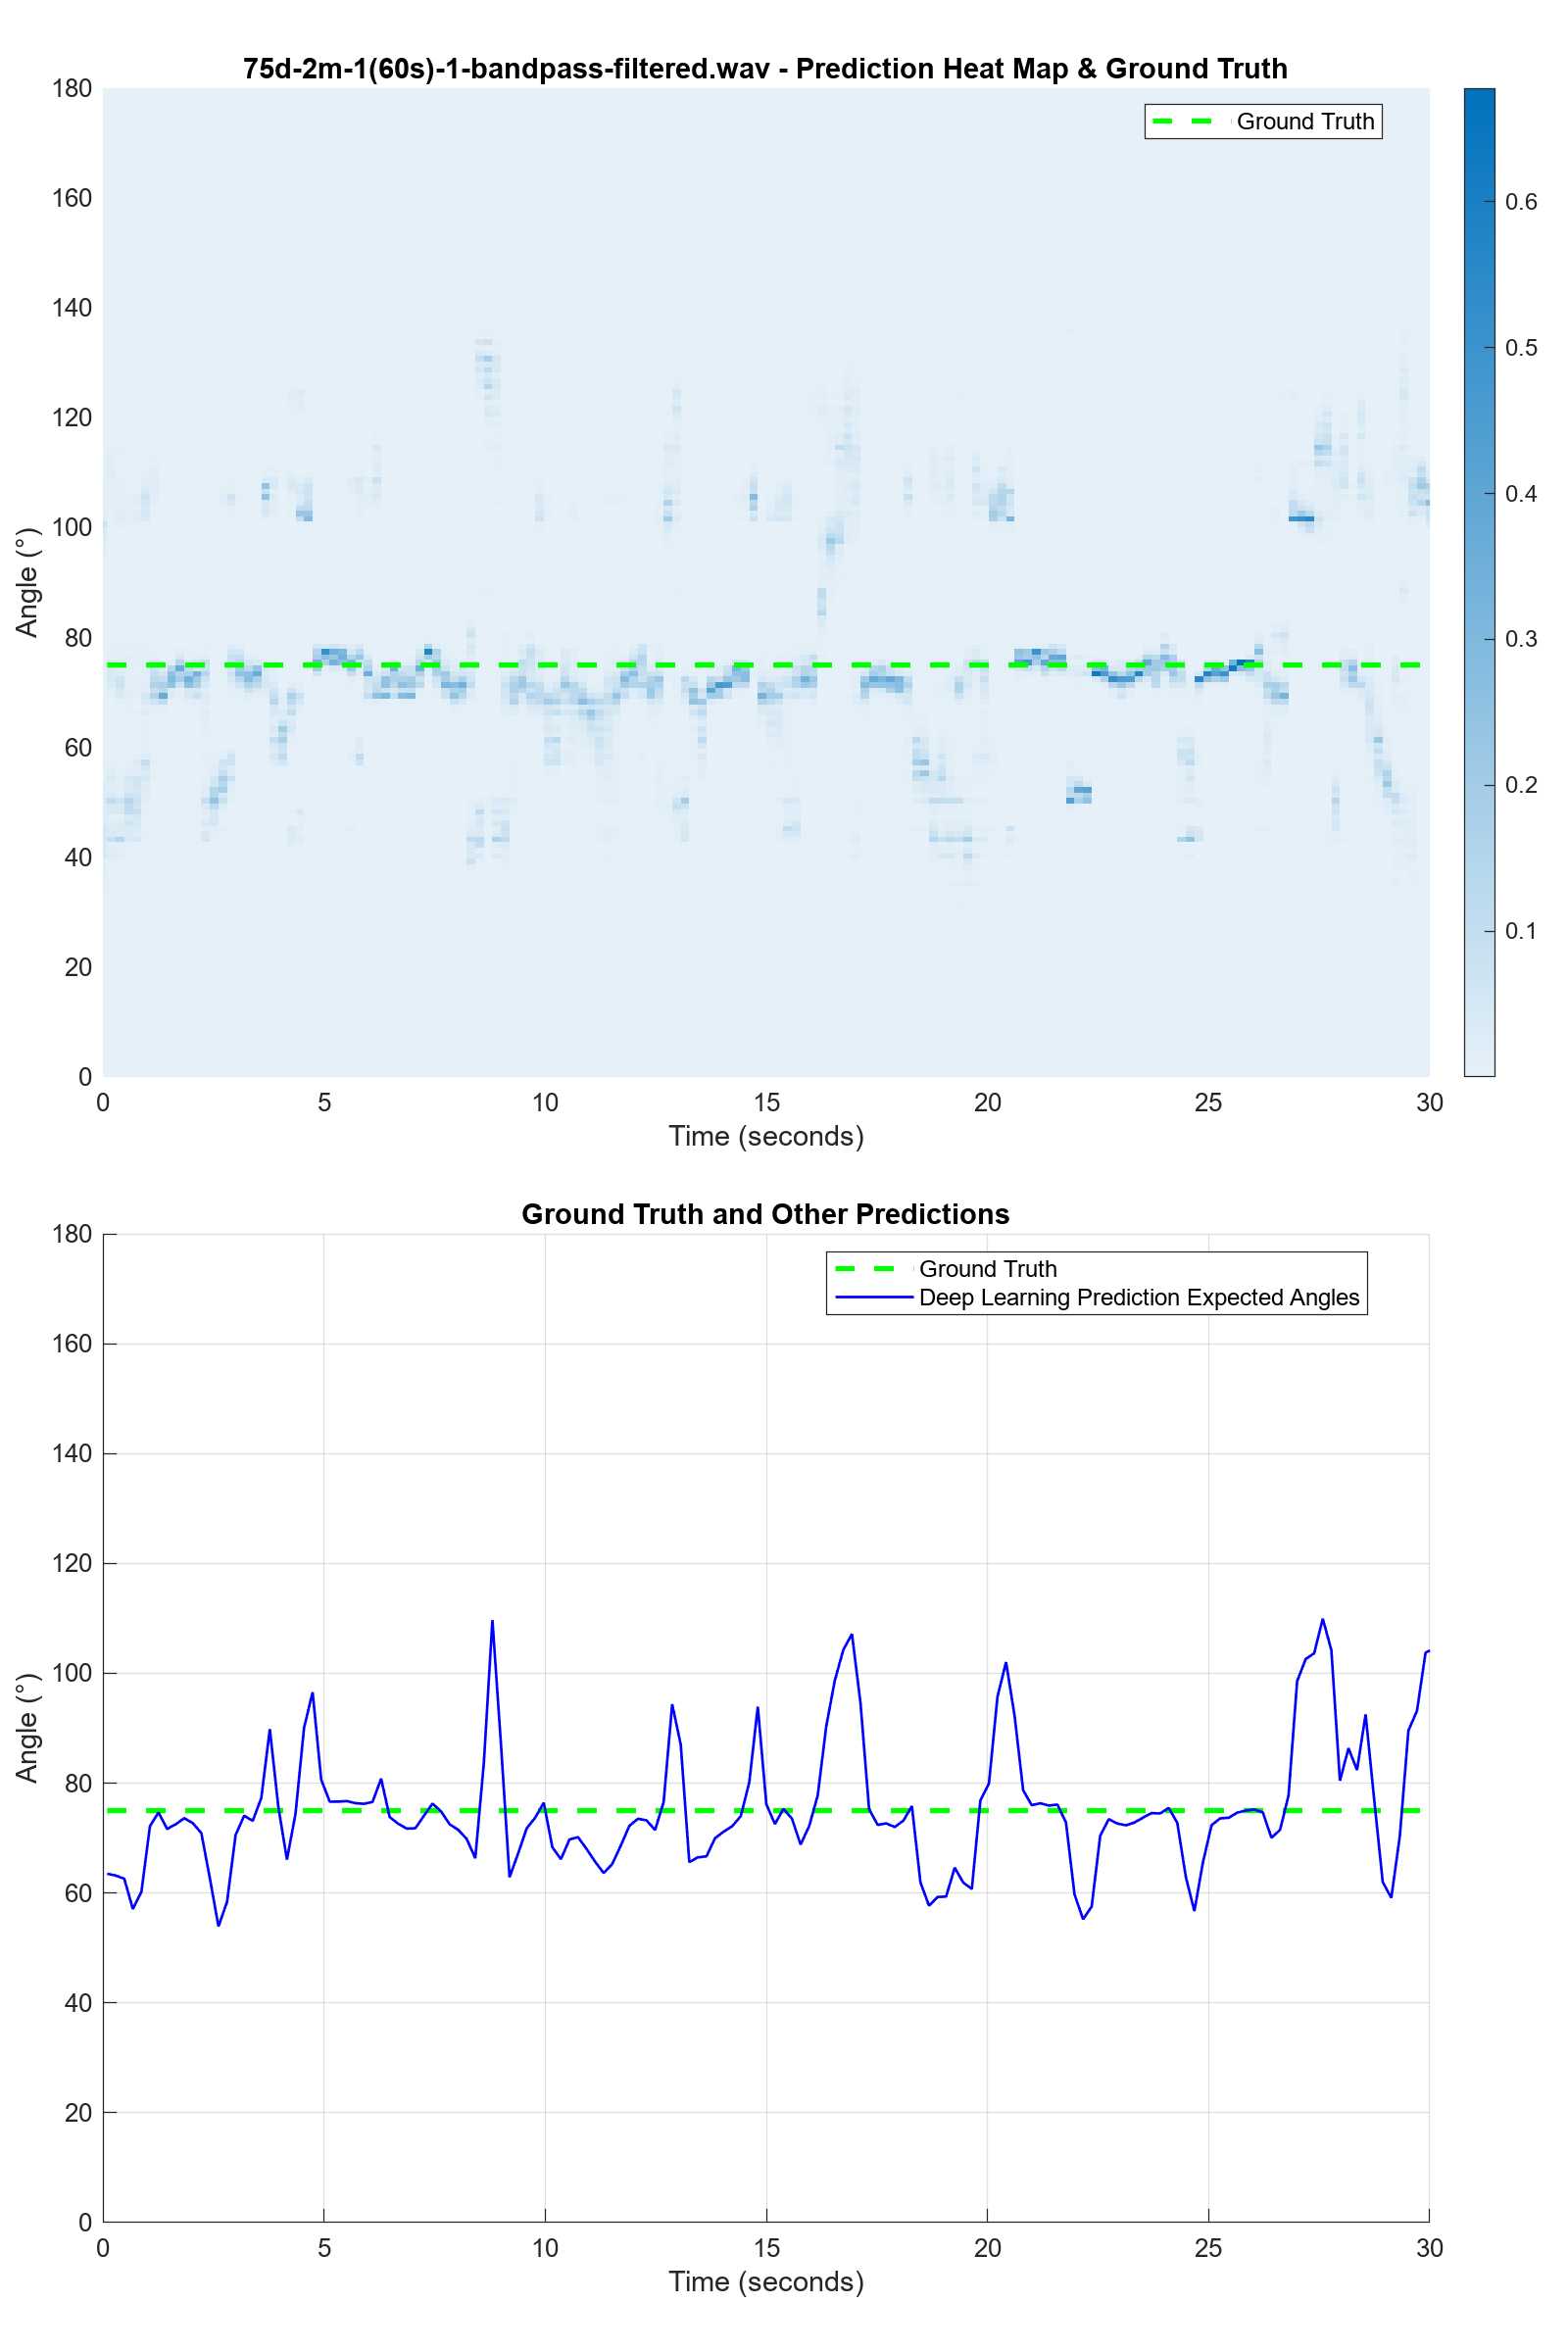

成功保存图像: 75d-2m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


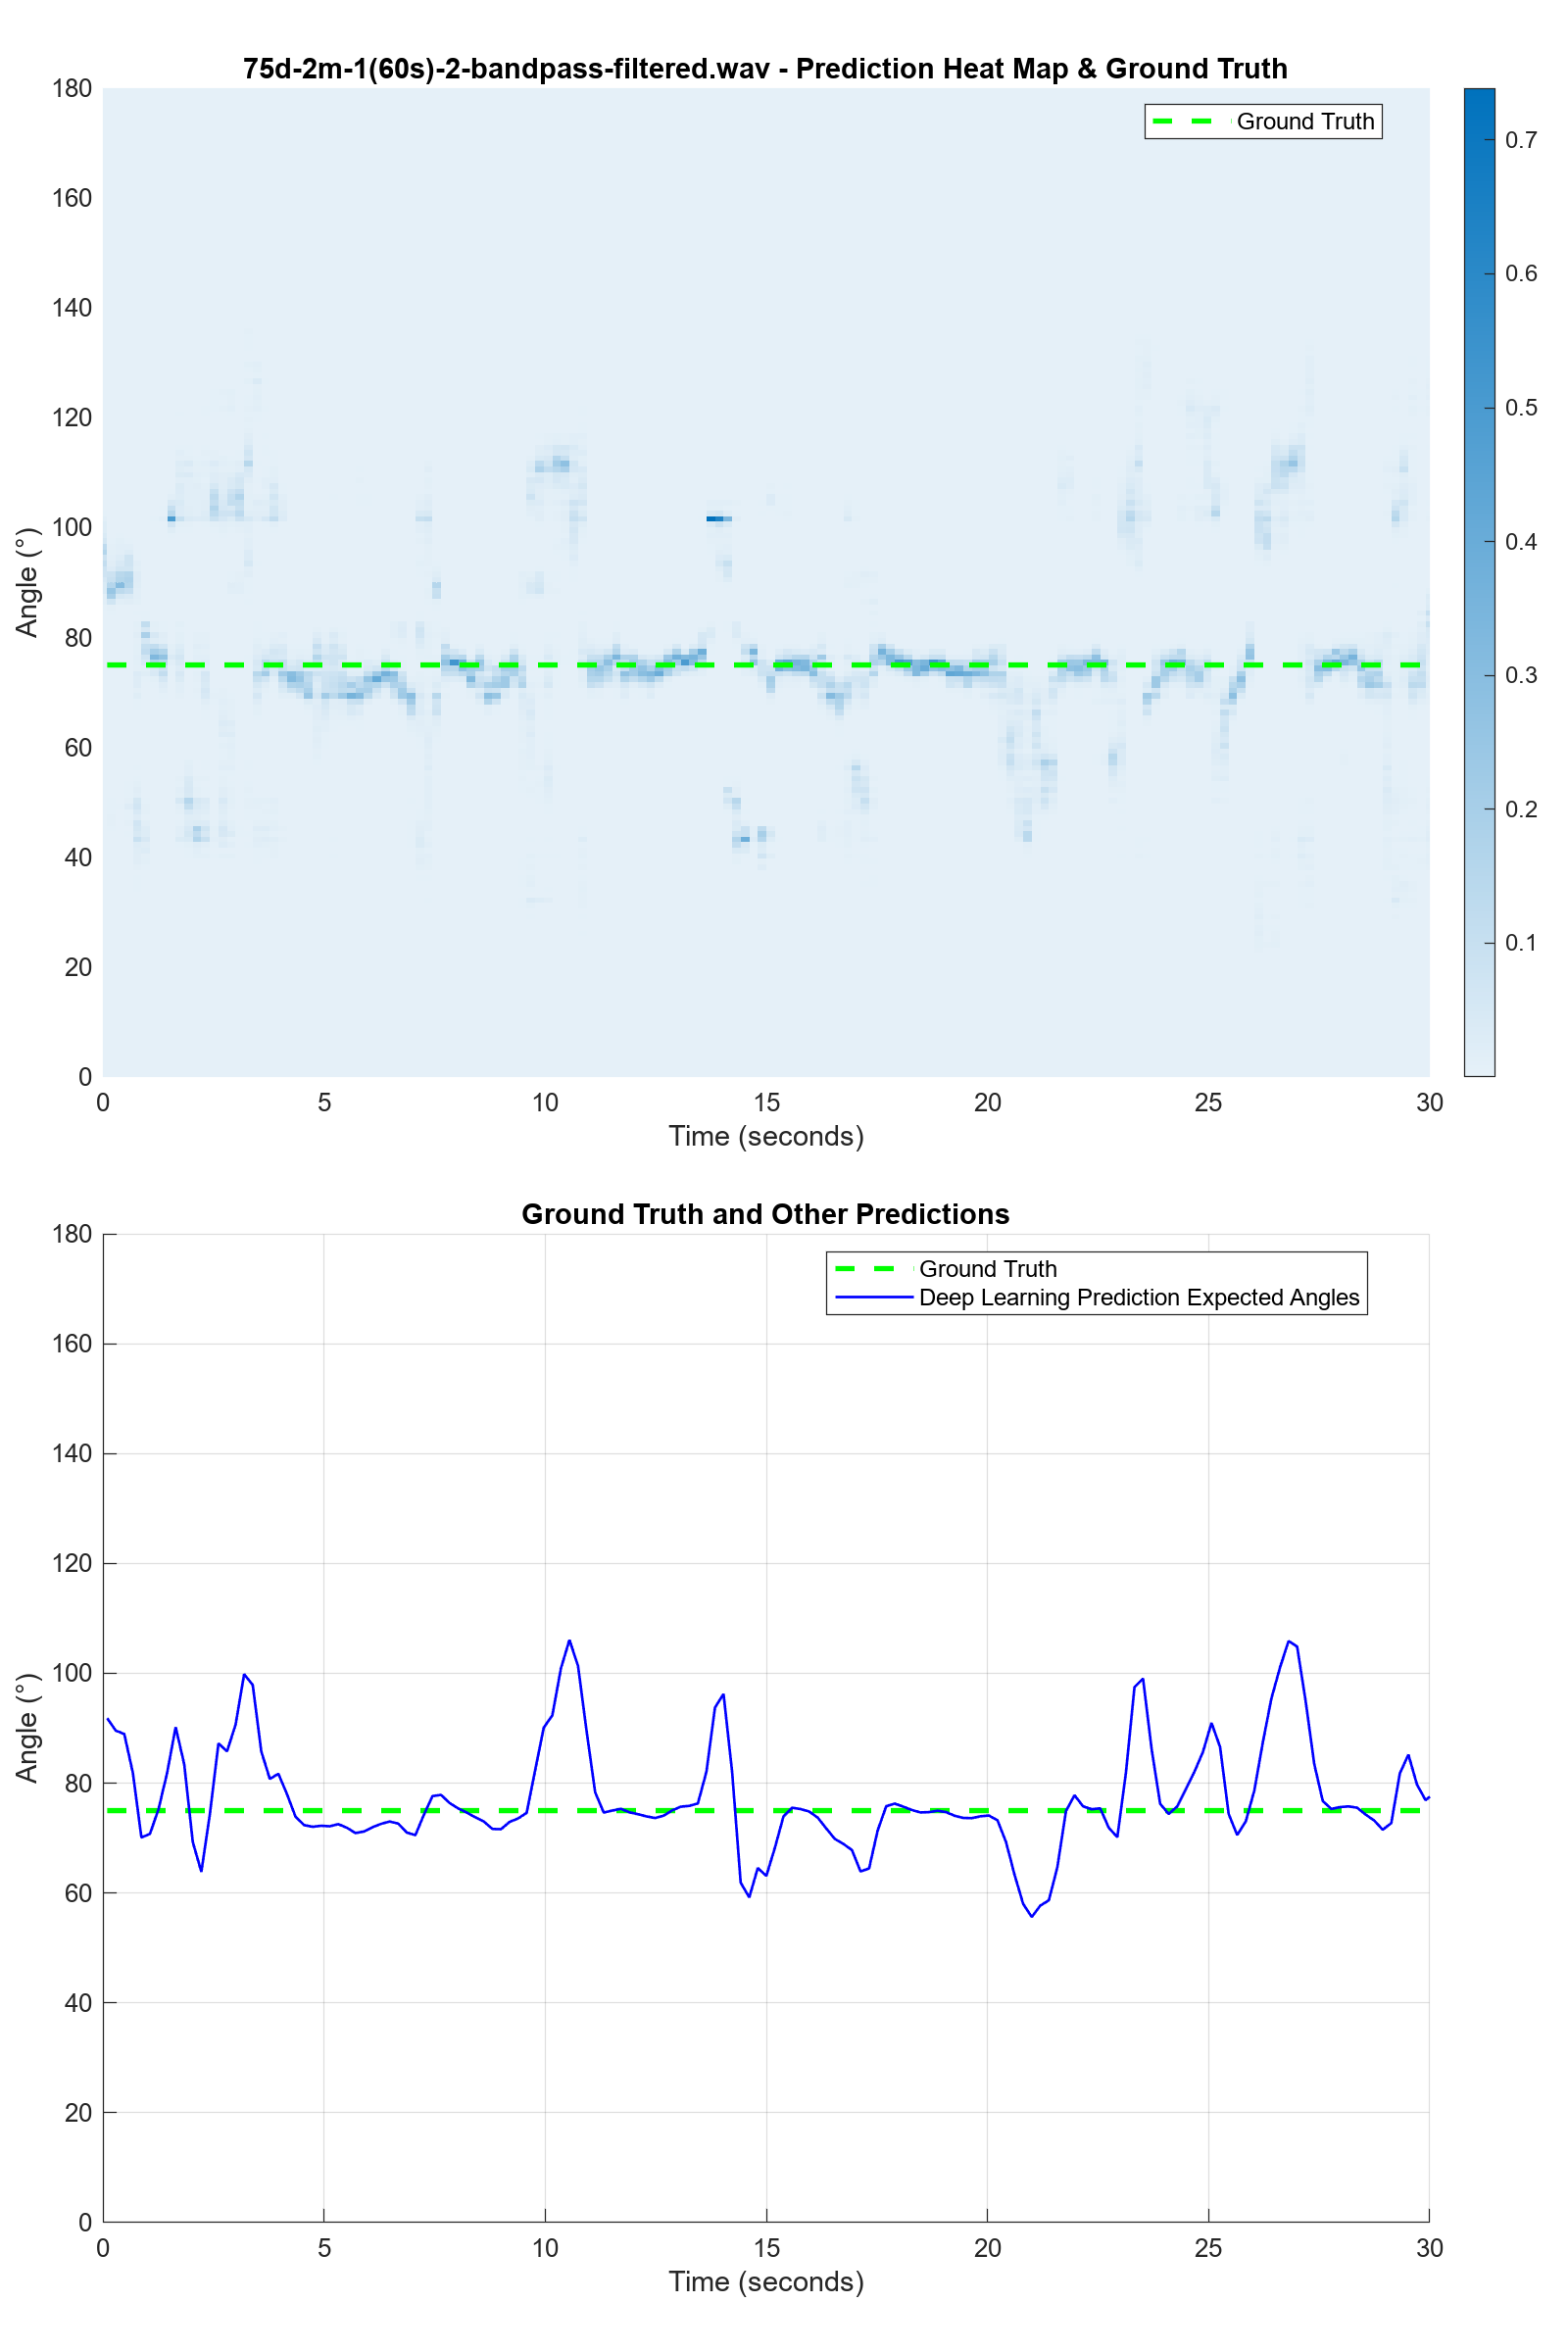

成功保存图像: 75d-2m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


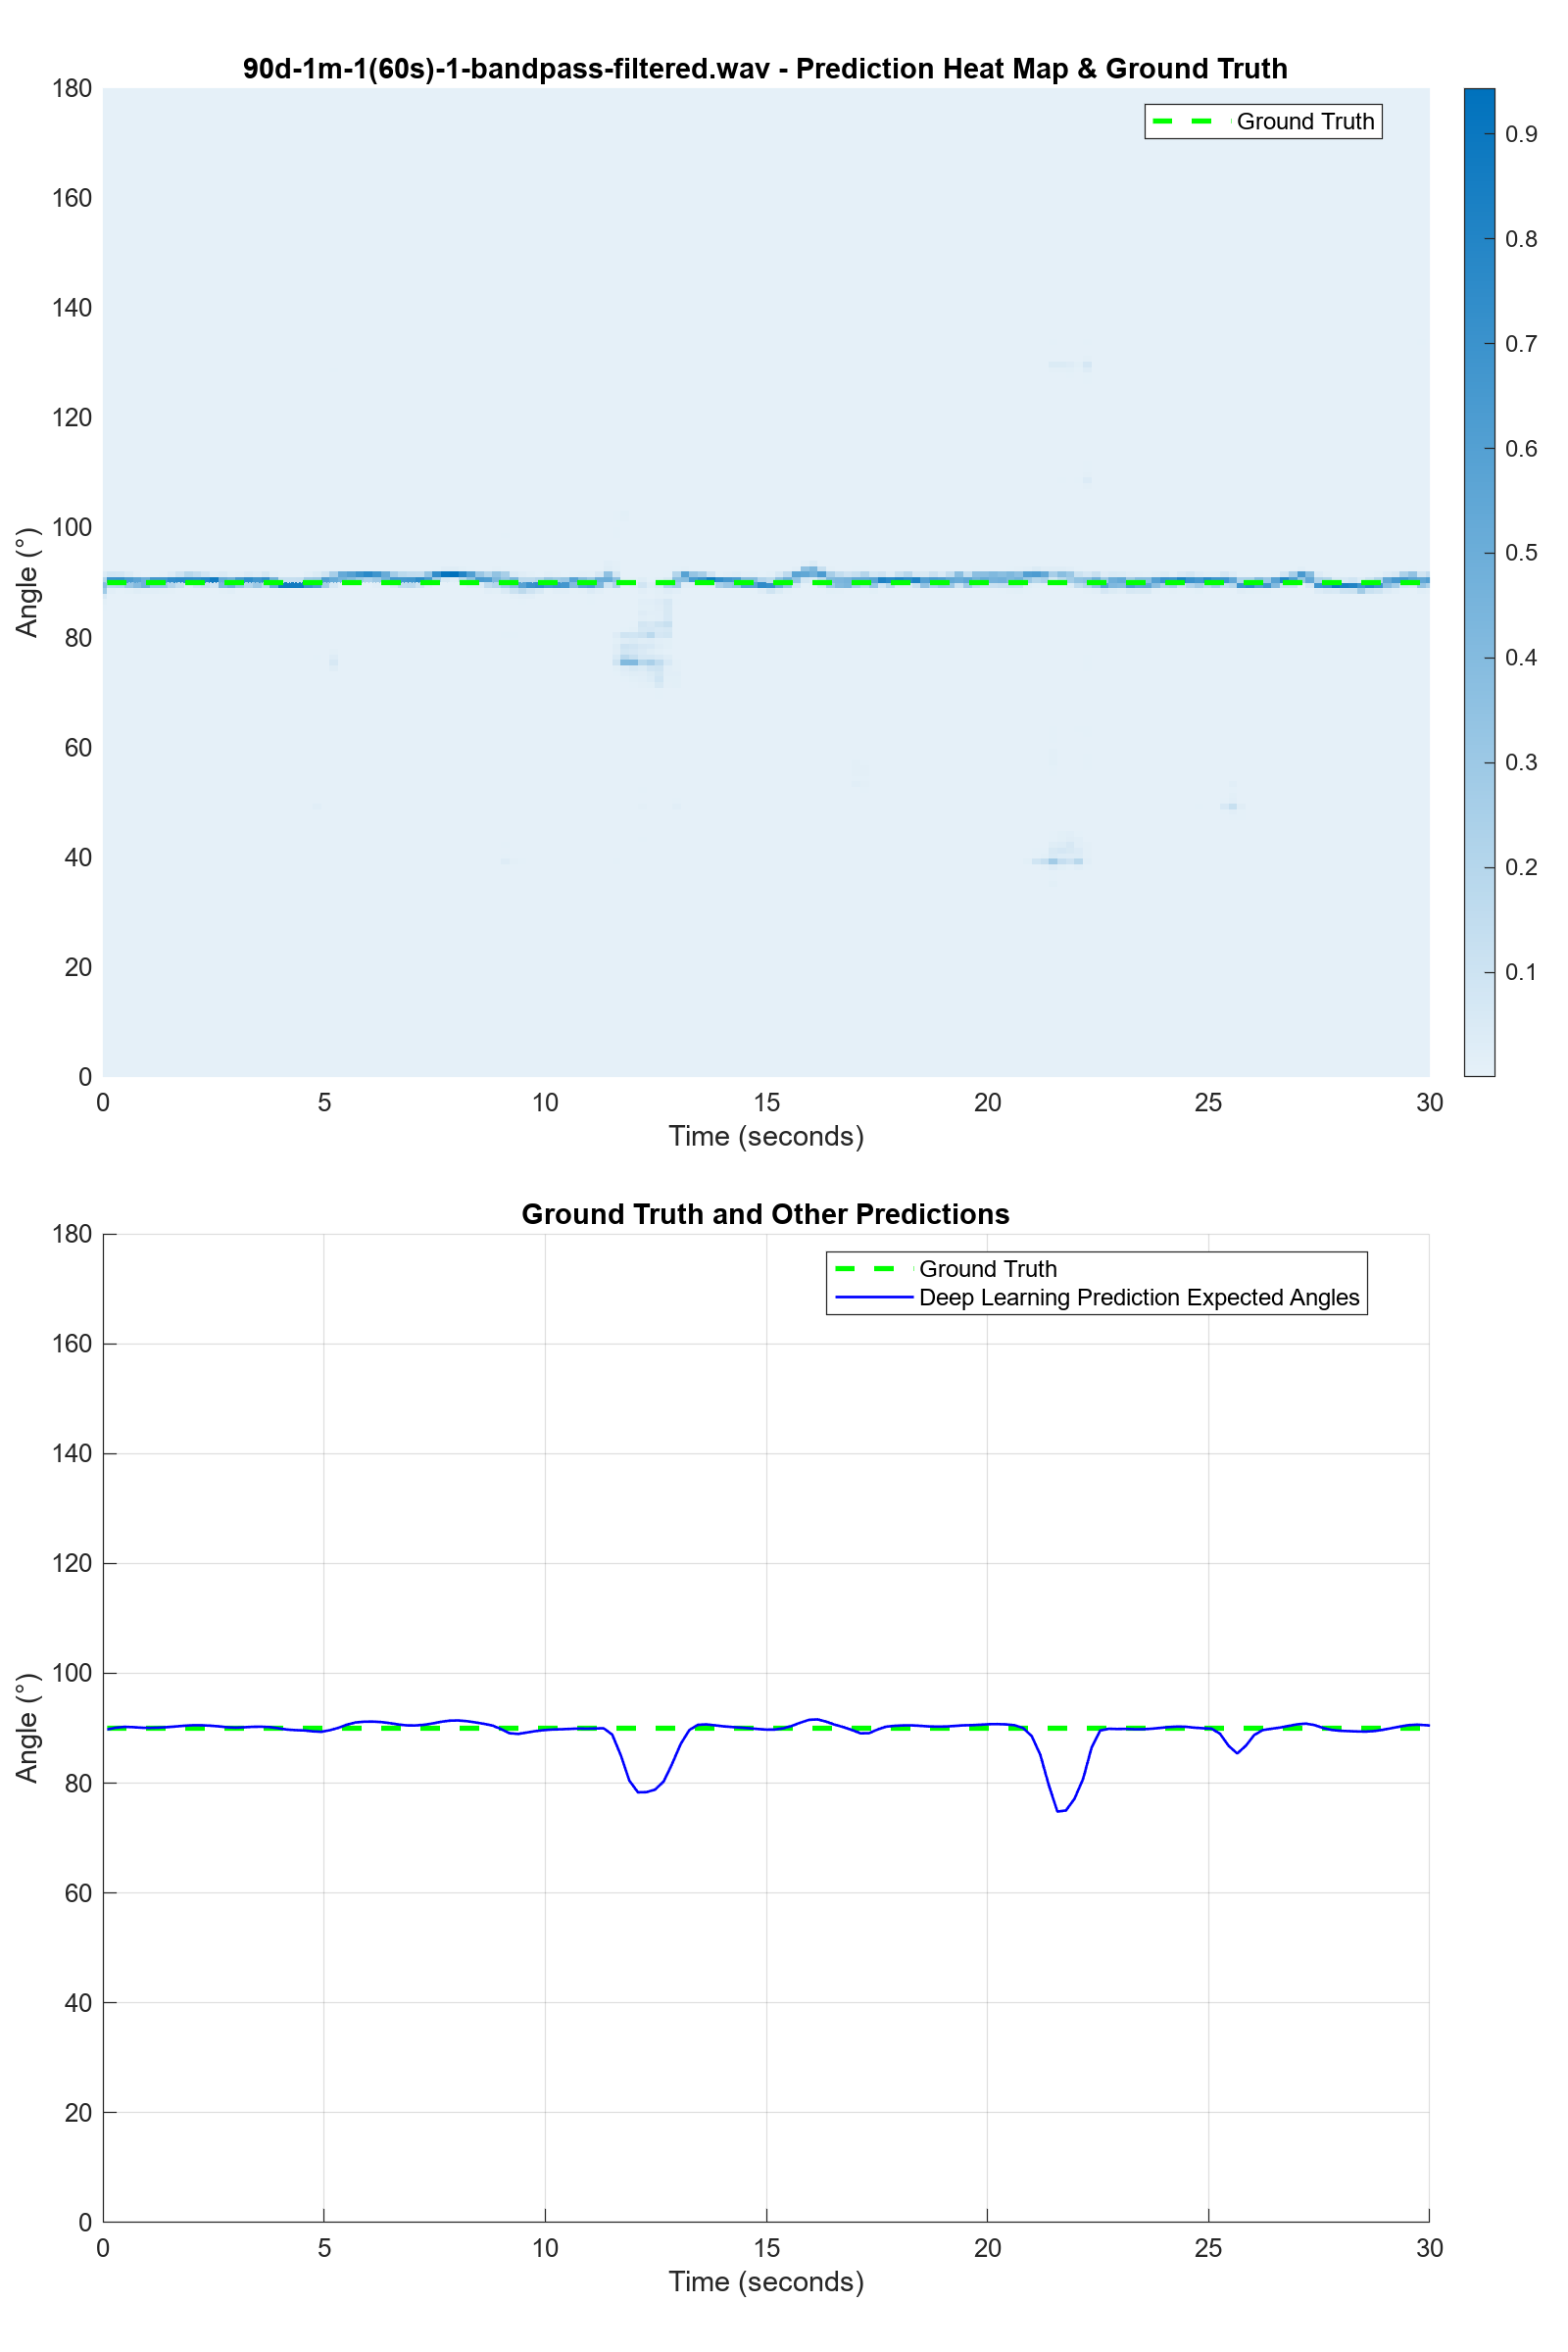

成功保存图像: 90d-1m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


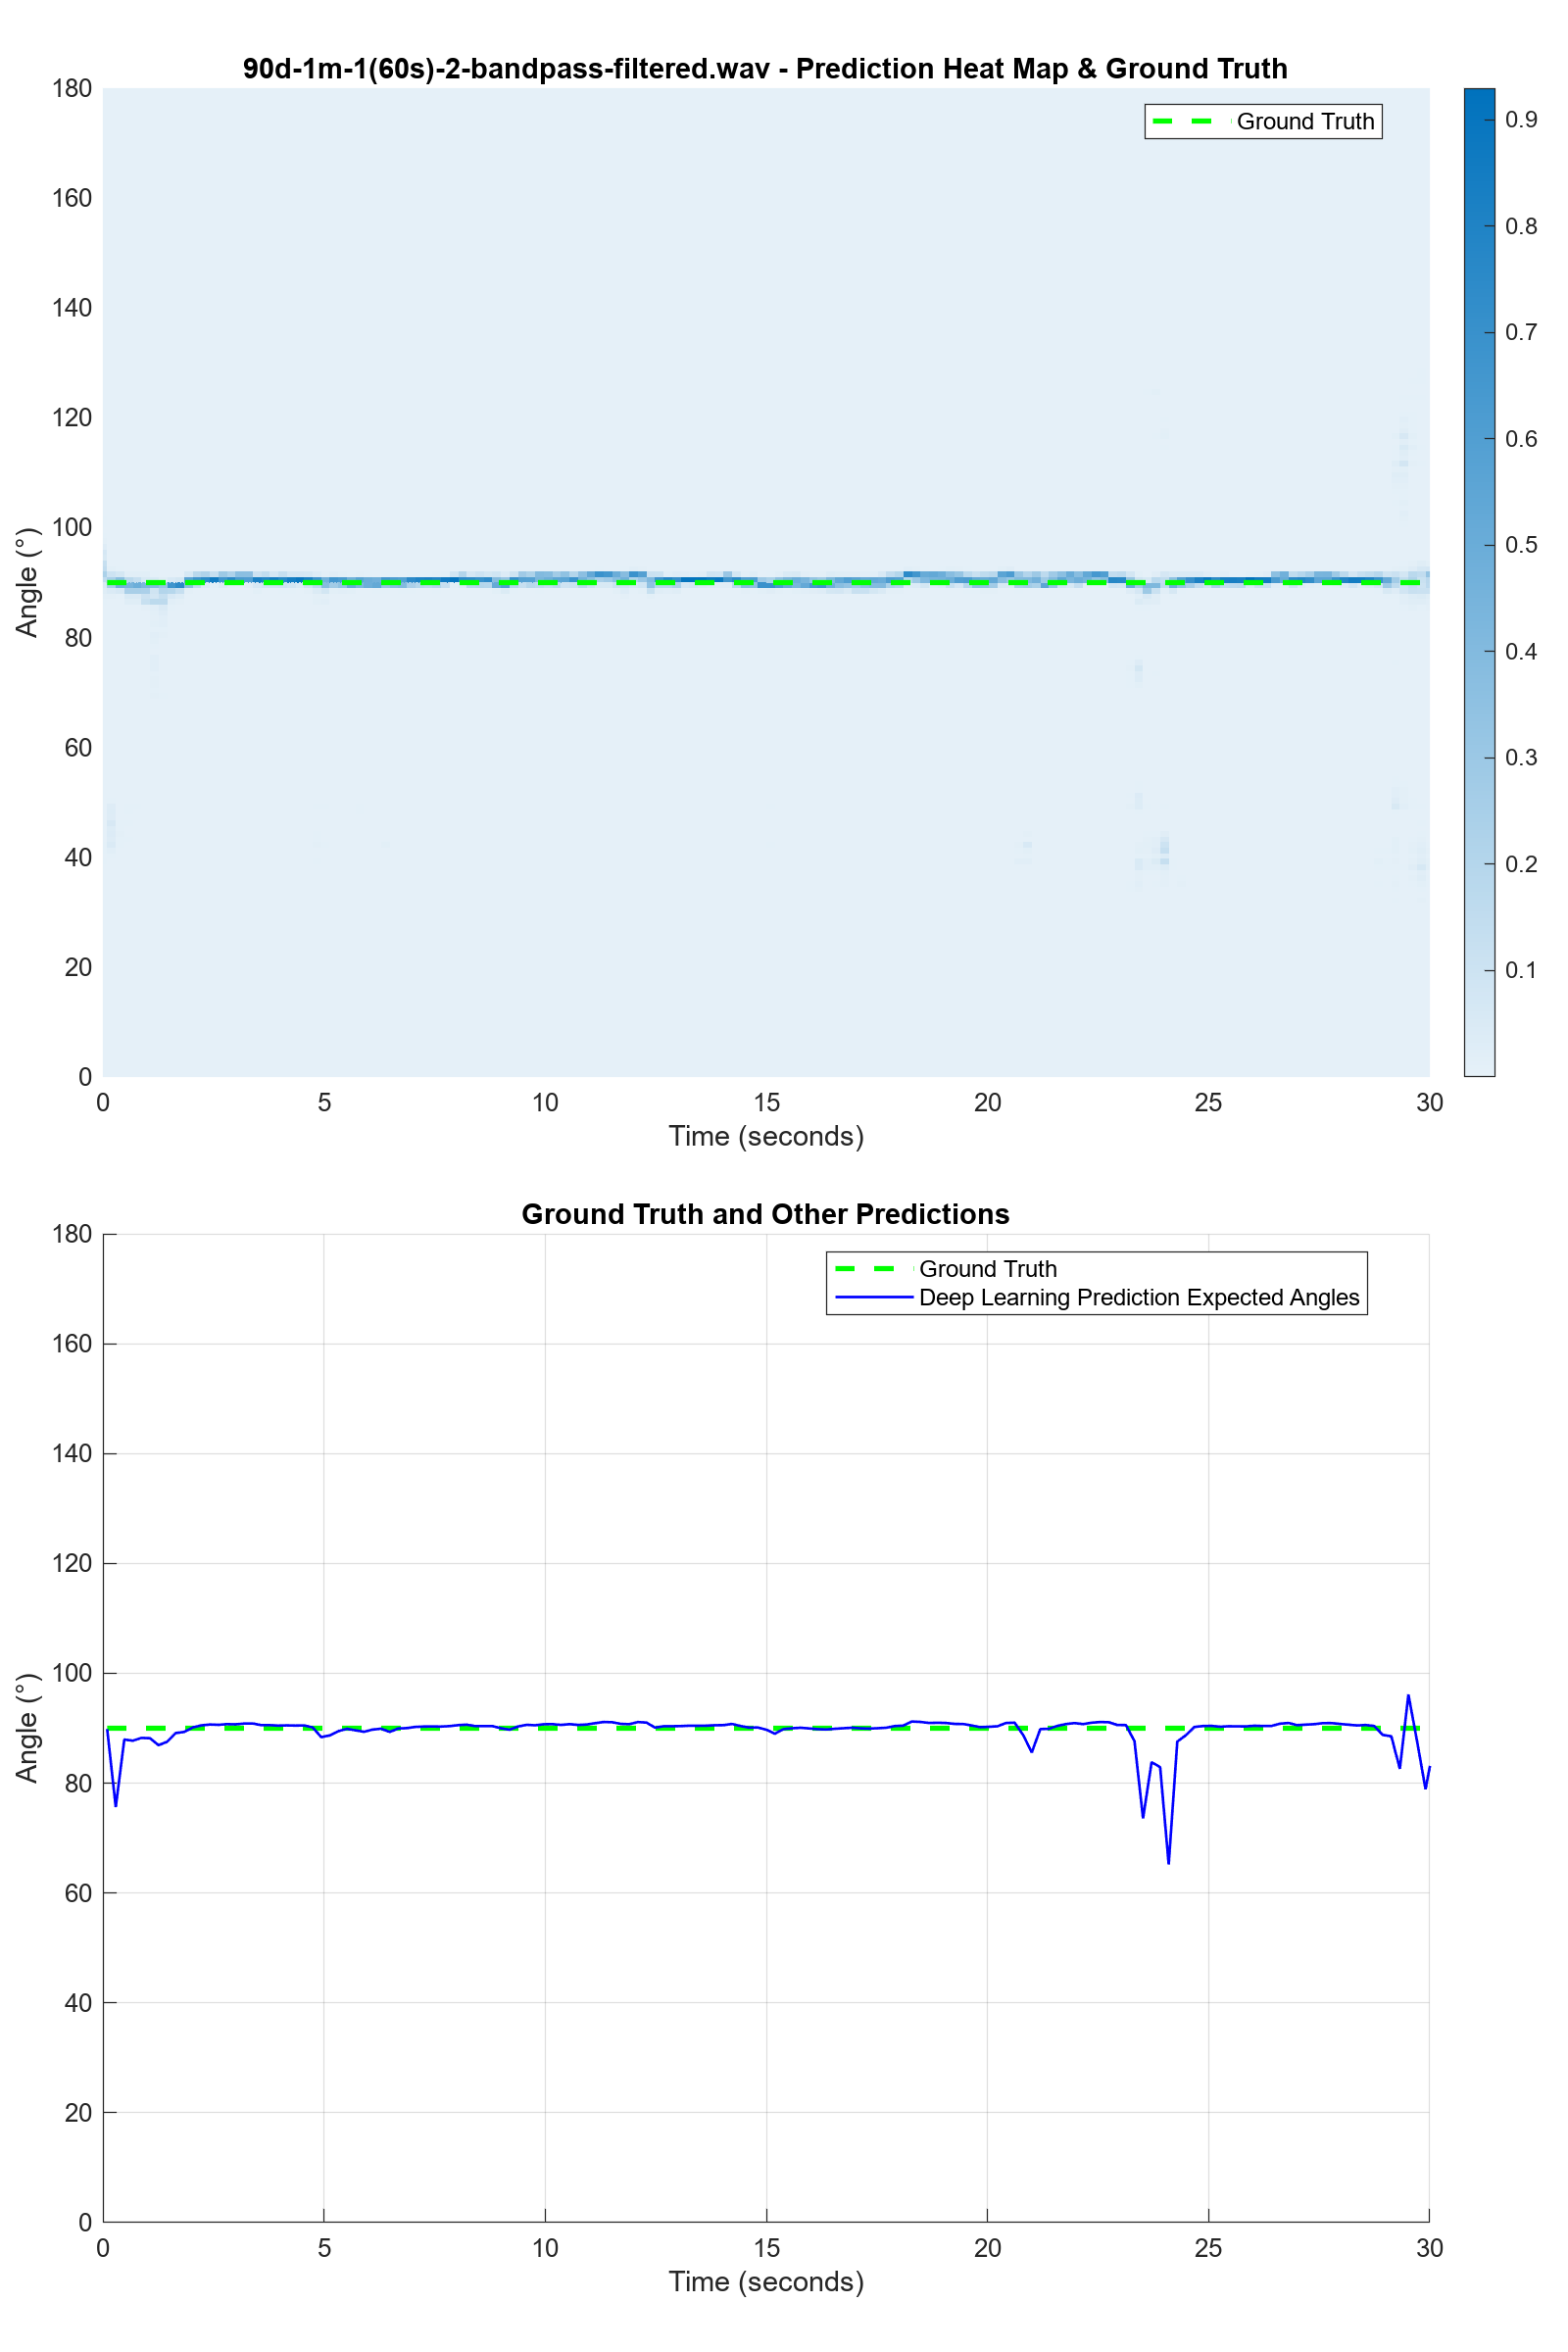

成功保存图像: 90d-1m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


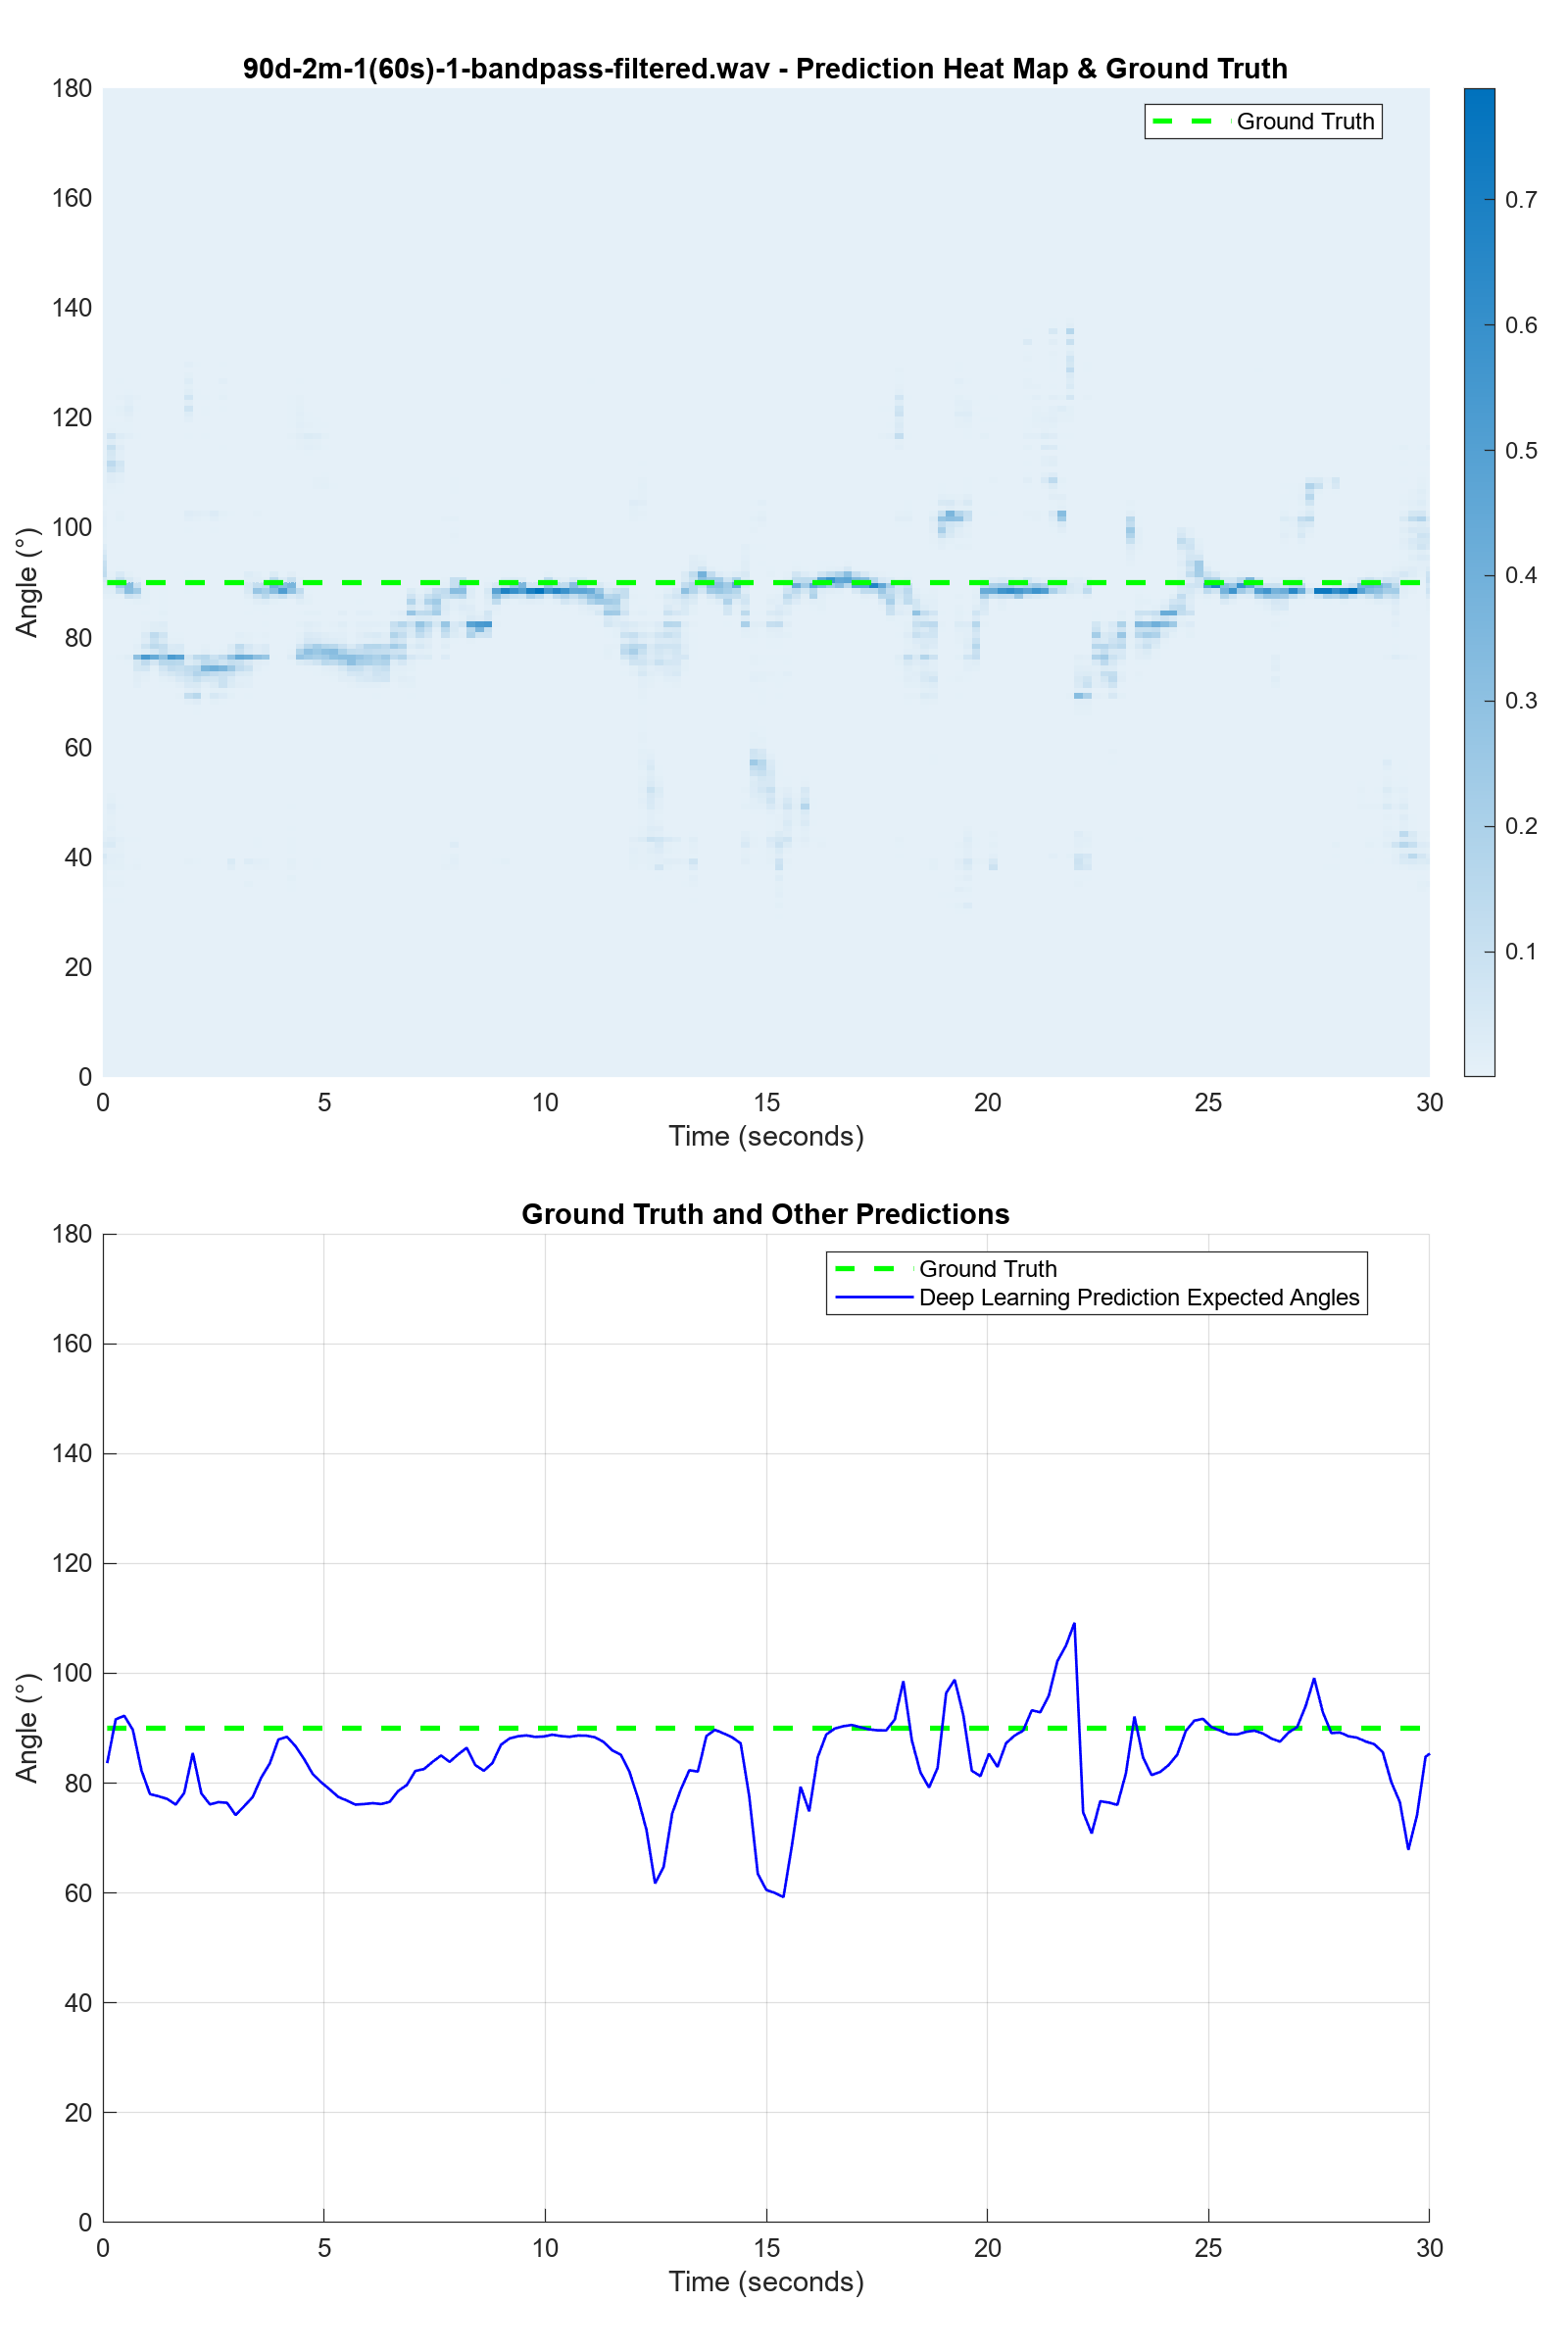

成功保存图像: 90d-2m-1(60s)-1-bandpass-filtered-pred-matrix-TDOA.png


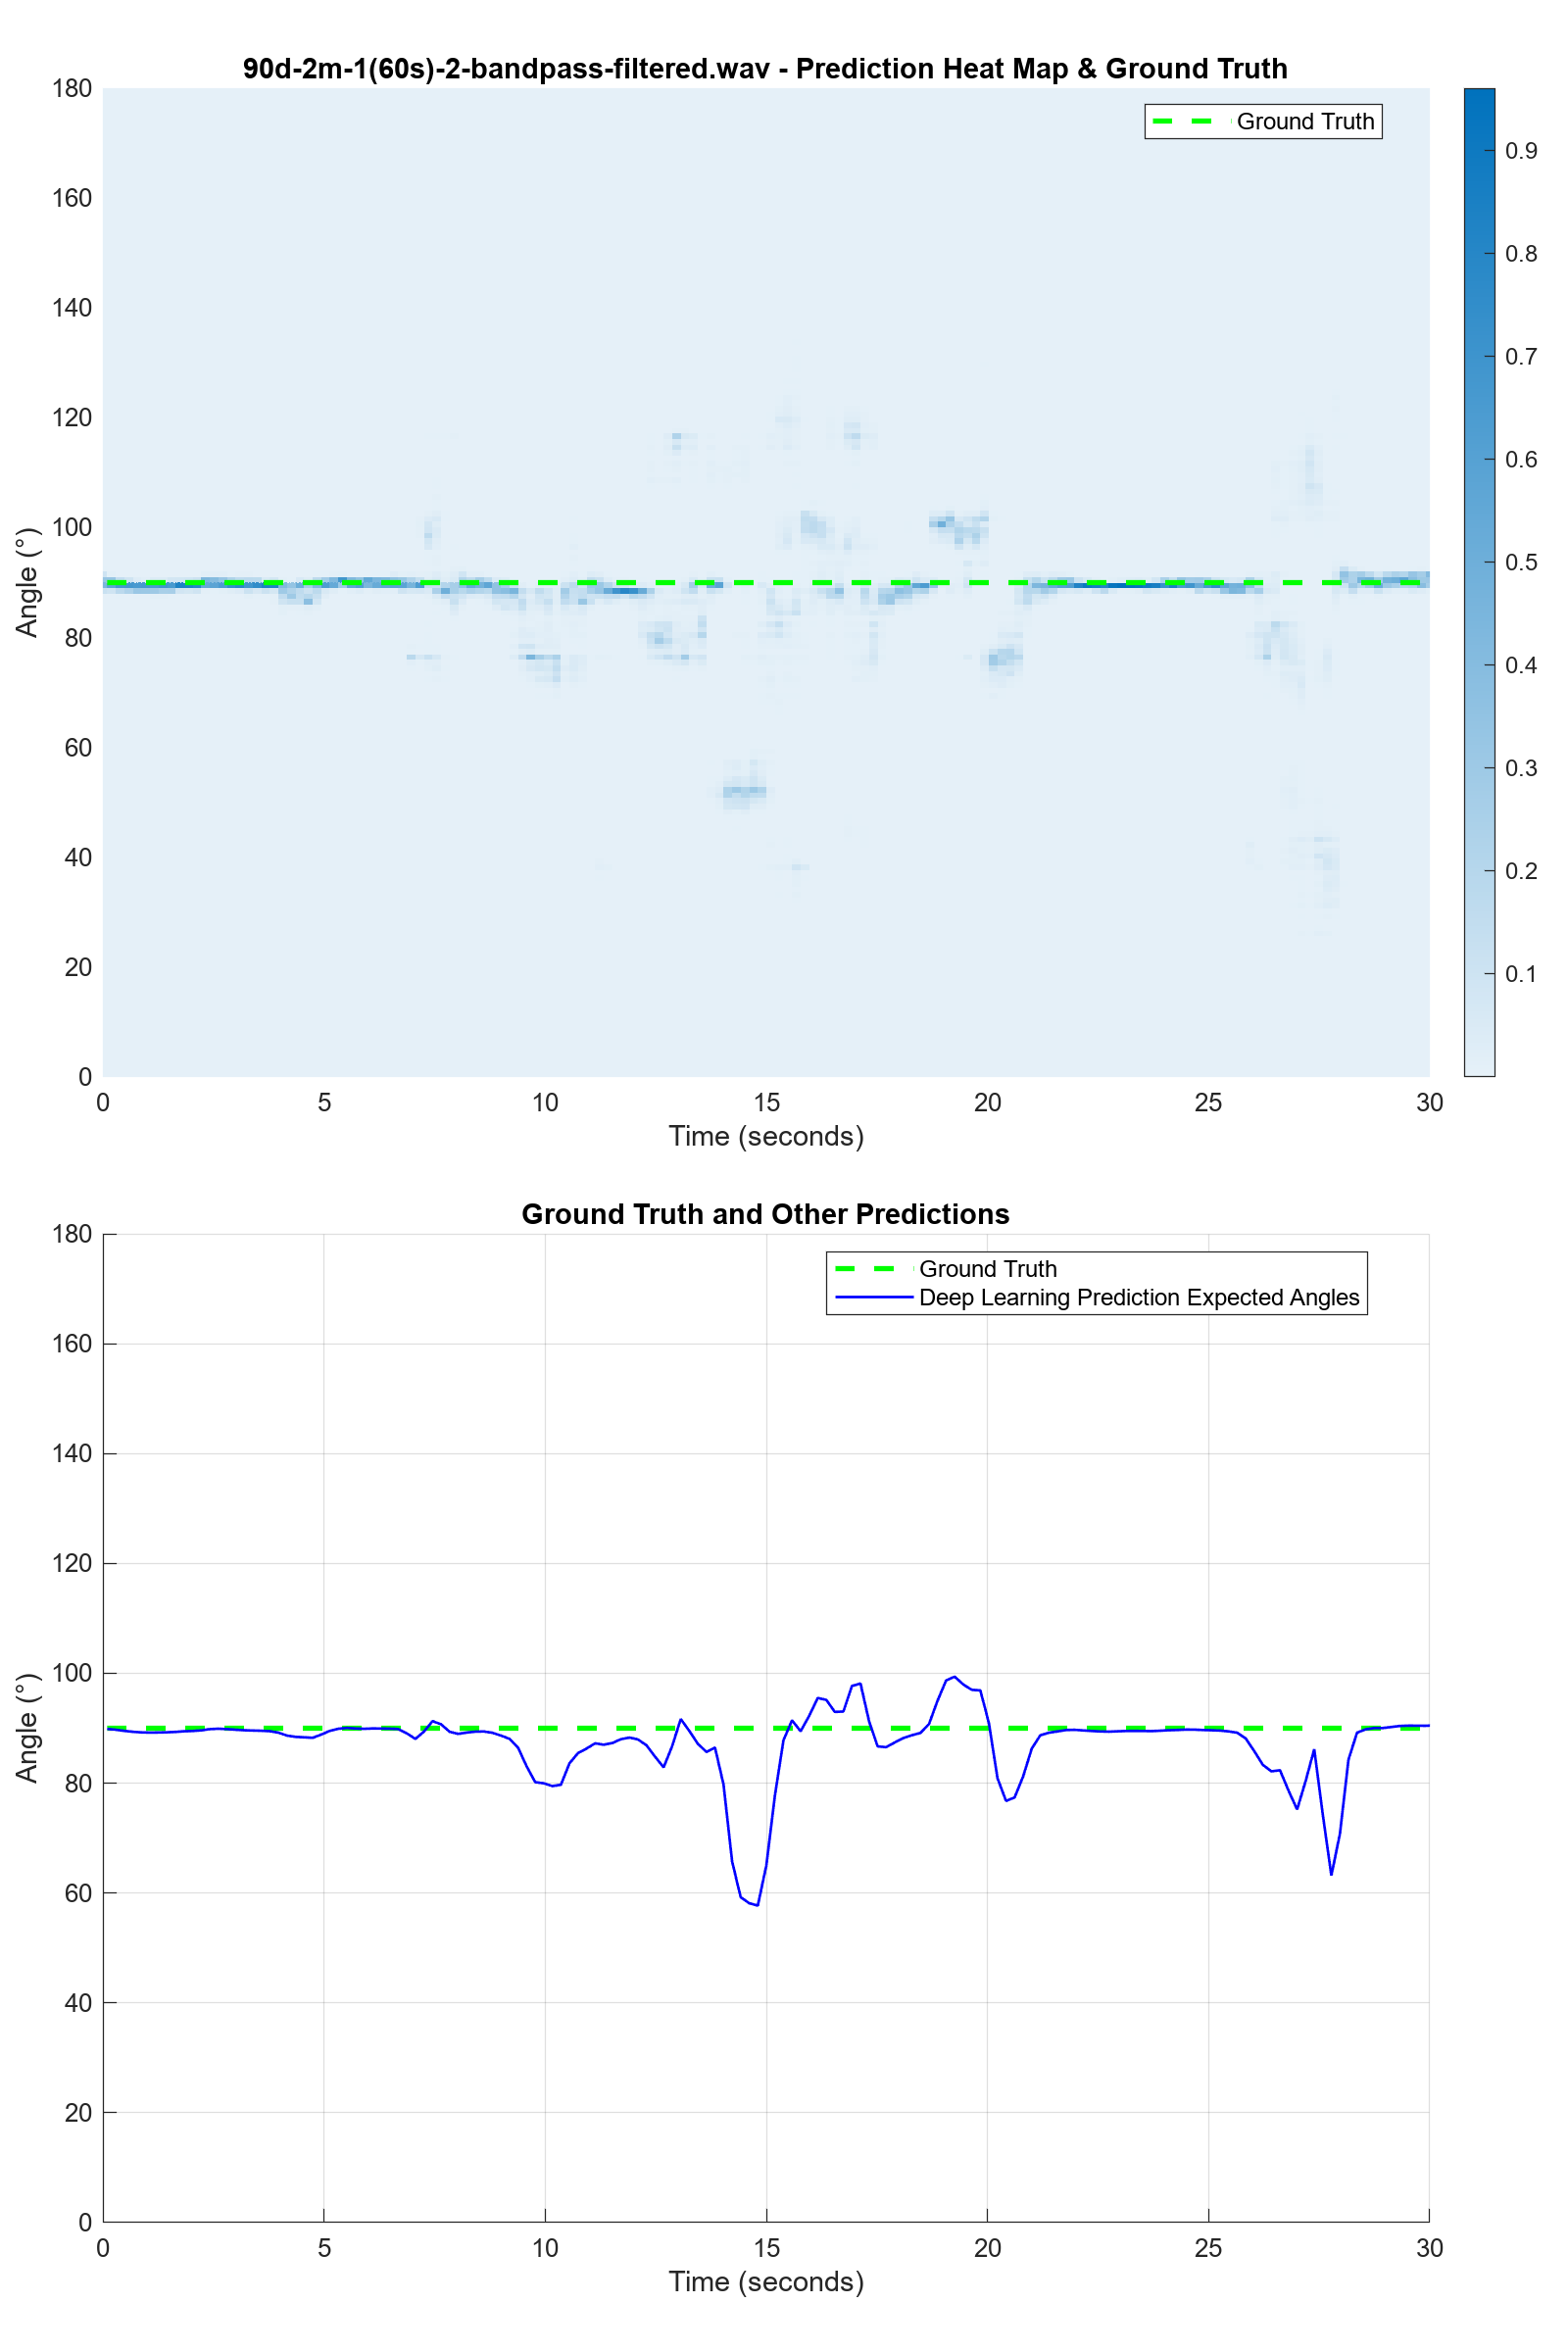

成功保存图像: 90d-2m-1(60s)-2-bandpass-filtered-pred-matrix-TDOA.png


clear all; 
close all;

% For Debugging
pred_root = 'D:\OneDrive\OneDrive - The Hong Kong Polytechnic University\PolyU Folder\FYP\FYP-Experiments\pred_result\pred_results_mar_18_on_apr_5_stationary';
audio_dir = 'D:\OneDrive\OneDrive - The Hong Kong Polytechnic University\PolyU Folder\FYP\FYP-Experiments\audio_data\data-mar-18-stationary-segmented-filtered-1';
output_dir = 'D:\OneDrive\OneDrive - The Hong Kong Polytechnic University\PolyU Folder\FYP\FYP-Experiments\result_plot\debug';
pred_matrix_dir = fullfile(pred_root, 'pred_matrix');

% [pred_root, pred_matrix_dir, audio_dir, output_dir] = selectPaths();

pred_files = dir(fullfile(pred_matrix_dir, '*-pred-matrix.txt'));

% 设置绘图选项，true显示，false隐藏
plotOptions.showPredMatrix = true;
plotOptions.showTDOA = true;
plotOptions.showDLMax = false;
plotOptions.showGT = true;
plotOptions.showExpectedAngles = true;
plotOptions.saveFig = true;

micDist = 0.16;
speedOfSound = 343;

if isempty(pred_files)
    errordlg(['路径为空: ' ME.message], '系统错误');
    return;
end

for file_idx = 1:length(pred_files)
    [~, base_name] = fileparts(pred_files(file_idx).name);
    name_parts = strsplit(base_name, '-');
    if strcmp(name_parts{4}, "bandpass") % Moving
        file_prefix = strjoin(name_parts(1:3), '-');
        plotOptions.showGT = false;
    else % Stationary
        file_prefix = strjoin(name_parts(1:4), '-');
        DOA_gt_str = name_parts(1);
        DOA_gt_num = str2double(erase(DOA_gt_str, 'd'));
    end

    audio_file = [file_prefix '-bandpass-filtered.wav'];
    audio_path = fullfile(audio_dir, audio_file);
    if ~exist(audio_path, 'file')
        warning('找不到匹配预测文件: %s', file_prefix);
        continue;
    end

    % 读取数据
    [audio_data, fs] = audioread(audio_path);
    pred_matrix = readmatrix(fullfile(pred_matrix_dir, pred_files(file_idx).name));
    pred_matrix = transpose(pred_matrix);
    pred_matrix = softmax(pred_matrix); % 进行softmax处理
    pred_matrix = transpose(pred_matrix);

    [num_frames, num_angles] = size(pred_matrix);

    total_time = size(audio_data,1)/fs;
    frame_duration = total_time / num_frames;
    frame_samples = round(frame_duration * fs);
    time_axis = linspace(0, frame_duration*num_frames, num_frames);
    DOA_gt = transpose(ones(num_frames,1).*DOA_gt_num);
    
    % 计算TDOA角度
    if plotOptions.showTDOA
        tdoa_angles = computeTDOAAngles(audio_data, fs, num_frames, num_angles, micDist, speedOfSound, frame_samples);
    else
        tdoa_angles = [];
    end

    % 计算深度学习最大角度索引
    if plotOptions.showDLMax
        dl_angles = computeDLMaxAngles(pred_matrix, true);
    else
        dl_angles = [];
    end

    % 计算期望角度
    if plotOptions.showExpectedAngles
        expected_angles = computeExpectedAngle(pred_matrix,true);
        % fprintf('平均绝对误差: %.3f 度\n', mean(abs(expected_angles-DOA_gt_num)));
    end

    angles = linspace(0, 180, num_angles);
    
    plotData.angles = angles;
    plotData.pred_matrix = pred_matrix;
    plotData.tdoa_angles = tdoa_angles;
    plotData.DOA_gt = DOA_gt;
    plotData.dl_angles = dl_angles;
    plotData.total_time = total_time;
    plotData.expected_angles = expected_angles;

    % 调用绘图函数
    % fig = plotPredictionComparison(time_axis, plotData, audio_file, plotOptions);
    fig = plotPredictionComparison_heatmap_double(time_axis, plotData, audio_file, plotOptions);

    % 保存图片
    if plotOptions.saveFig
        output_name = [file_prefix '-bandpass-filtered-pred-matrix-TDOA.png'];
        exportgraphics(fig, fullfile(output_dir, output_name), 'Resolution', 300);
        close(fig);
    
        fprintf('成功保存图像: %s\n', output_name);
    else
        figure(fig); % 激活并显示已有的图形窗口
        % drawnow;
        fprintf('已处理图像: %s\n', file_prefix);
    end


end


disp('处理完成！所有结果已保存');

处理完成！所有结果已保存


function [pred_root, pred_matrix_dir, audio_dir, output_dir] = selectPaths()
    % selectPaths 交互式选择预测结果根目录、原始语音目录和结果保存目录
    %
    % 输出：
    %   pred_root       - 预测结果根目录路径
    %   pred_matrix_dir - 预测矩阵目录路径 (pred_root/pred_matrix)
    %   audio_dir       - 原始语音文件目录路径
    %   output_dir      - 结果保存目录路径
    
    try
        pred_root = uigetdir('', '选择预测结果根文件夹');
        if pred_root == 0
            error('未选择预测结果根文件夹');
        end
        pred_matrix_dir = fullfile(pred_root, 'pred_matrix');
        fprintf('预测结果根文件夹: %s\n', pred_root);
    
        audio_dir = uigetdir('', '选择原始语音文件文件夹');
        if audio_dir == 0
            error('未选择原始语音文件文件夹');
        end
        fprintf('原始语音文件夹: %s\n', audio_dir);
    
        output_dir = uigetdir('', '选择结果保存文件夹');
        if output_dir == 0
            error('未选择结果保存文件夹');
        end
        fprintf('结果保存文件夹: %s\n', output_dir);
    
    catch ME
        warning(['路径选择错误: ', ME.message, '，使用默认路径']);
        % 这里你可以设置默认路径，或者抛出错误
        pred_root = 'D:\OneDrive\OneDrive - The Hong Kong Polytechnic University\PolyU Folder\FYP\FYP-Experiments\pred_result\pred_results_mar_18_on_apr_5_stationary';
        pred_matrix_dir = fullfile(pred_root, 'pred_matrix');
        audio_dir = 'D:\OneDrive\OneDrive - The Hong Kong Polytechnic University\PolyU Folder\FYP\FYP-Experiments\audio_data\data-mar-18-stationary-segmented-filtered';
        output_dir = 'D:\OneDrive\OneDrive - The Hong Kong Polytechnic University\PolyU Folder\FYP\FYP-Experiments\result_plot\debug';
    end
end
